# **Development of Multiple Regression Model to Predict Lower Limb Kinematic Waveforms**

# Import gait phases data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 05-Jan-2024 22:39:14

## Set up the Import Options and import the gait phases data

opts = spreadsheetImportOptions("NumVariables", 434);

% Specify sheet and range
opts.Sheet = "GaitPhases";
opts.DataRange = "A3:PR10";

% Specify column names and types
opts.VariableNames = ["Var1", "GaitPhases", "Var3", "v11", "Var5", "v12", "Var7", "v13", "Var9", "v21", "Var11", "v22", "Var13", "v23", "Var15", "v31", "Var17", "v32", "Var19", "v33", "Var21", "v1", "Var23", "v2", "Var25", "v3", "Var27", "v4", "Var29", "v5", "Var31", "v6", "Var33", "v7", "Var35", "v8", "Var37", "v9", "Var39", "v10", "Var41", "v14", "Var43", "v15", "Var45", "v16", "Var47", "v17", "Var49", "v18", "Var51", "v19", "Var53", "v20", "Var55", "v24", "Var57", "v25", "Var59", "v26", "Var61", "v27", "Var63", "v28", "Var65", "v29", "Var67", "v30", "Var69", "v34", "Var71", "v35", "Var73", "v36", "Var75", "v37", "Var77", "v38", "Var79", "v39", "Var81", "v40", "Var83", "v41", "Var85", "v42", "Var87", "v43", "Var89", "v44", "Var91", "v45", "Var93", "v46", "Var95", "v47", "Var97", "v48", "Var99", "v49", "Var101", "v50", "Var103", "v51", "Var105", "v52", "Var107", "v53", "Var109", "v54", "Var111", "v55", "Var113", "v56", "Var115", "v57", "Var117", "v58", "Var119", "v59", "Var121", "v60", "Var123", "v61", "Var125", "v62", "Var127", "v63", "Var129", "v64", "Var131", "v65", "Var133", "v66", "Var135", "v67", "Var137", "v68", "Var139", "v69", "Var141", "v70", "Var143", "v71", "Var145", "v72", "Var147", "v73", "Var149", "v74", "Var151", "v75", "Var153", "v76", "Var155", "v77", "Var157", "v78", "Var159", "v79", "Var161", "v80", "Var163", "v81", "Var165", "v82", "Var167", "v83", "Var169", "v84", "Var171", "v85", "Var173", "v86", "Var175", "v87", "Var177", "v88", "Var179", "v89", "Var181", "v90", "Var183", "v91", "Var185", "v92", "Var187", "v93", "Var189", "v94", "Var191", "v95", "Var193", "v96", "Var195", "v97", "Var197", "v98", "Var199", "v99", "Var201", "v100", "Var203", "v101", "Var205", "v102", "Var207", "v103", "Var209", "v104", "Var211", "v105", "Var213", "v106", "Var215", "v107", "Var217", "v108", "Var219", "v109", "Var221", "v110", "Var223", "v111", "Var225", "v112", "Var227", "v113", "Var229", "v114", "Var231", "v115", "Var233", "v116", "Var235", "v117", "Var237", "v118", "Var239", "v119", "Var241", "v120", "Var243", "v121", "Var245", "v122", "Var247", "v123", "Var249", "v124", "Var251", "v125", "Var253", "v126", "Var255", "v127", "Var257", "v128", "Var259", "v129", "Var261", "v130", "Var263", "v131", "Var265", "v132", "Var267", "v133", "Var269", "v134", "Var271", "v135", "Var273", "v136", "Var275", "v137", "Var277", "v138", "Var279", "v139", "Var281", "v140", "Var283", "v141", "Var285", "v142", "Var287", "v143", "Var289", "v144", "Var291", "v145", "Var293", "v146", "Var295", "v147", "Var297", "v148", "Var299", "v149", "Var301", "v150", "Var303", "v151", "Var305", "v152", "Var307", "v153", "Var309", "v154", "Var311", "v155", "Var313", "v156", "Var315", "v157", "Var317", "v158", "Var319", "v159", "Var321", "v160", "Var323", "v161", "Var325", "v162", "Var327", "v163", "Var329", "v164", "Var331", "v165", "Var333", "v166", "Var335", "v167", "Var337", "v168", "Var339", "v169", "Var341", "v170", "Var343", "v171", "Var345", "v172", "Var347", "v173", "Var349", "v174", "Var351", "v175", "Var353", "v176", "Var355", "v177", "Var357", "v178", "Var359", "v179", "Var361", "v180", "Var363", "v181", "Var365", "v182", "Var367", "v183", "Var369", "v184", "Var371", "v185", "Var373", "v186", "Var375", "v187", "Var377", "v188", "Var379", "v189", "Var381", "v190", "Var383", "v191", "Var385", "v192", "Var387", "v193", "Var389", "v194", "Var391", "v195", "Var393", "v196", "Var395", "v197", "Var397", "v198", "Var399", "v199", "Var401", "v200", "Var403", "v201", "Var405", "v202", "Var407", "v203", "Var409", "v204", "Var411", "v205", "Var413", "v206", "Var415", "v207", "Var417", "v208", "Var419", "v209", "Var421", "v210", "Var423", "v211", "Var425", "v212", "Var427", "v213", "Var429", "v214", "Var431", "v215", "Var433", "v216"];
opts.SelectedVariableNames = ["GaitPhases", "v11", "v12", "v13", "v21", "v22", "v23", "v31", "v32", "v33", "v1", "v2", "v3", "v4", "v5", "v6", "v7", "v8", "v9", "v10", "v14", "v15", "v16", "v17", "v18", "v19", "v20", "v24", "v25", "v26", "v27", "v28", "v29", "v30", "v34", "v35", "v36", "v37", "v38", "v39", "v40", "v41", "v42", "v43", "v44", "v45", "v46", "v47", "v48", "v49", "v50", "v51", "v52", "v53", "v54", "v55", "v56", "v57", "v58", "v59", "v60", "v61", "v62", "v63", "v64", "v65", "v66", "v67", "v68", "v69", "v70", "v71", "v72", "v73", "v74", "v75", "v76", "v77", "v78", "v79", "v80", "v81", "v82", "v83", "v84", "v85", "v86", "v87", "v88", "v89", "v90", "v91", "v92", "v93", "v94", "v95", "v96", "v97", "v98", "v99", "v100", "v101", "v102", "v103", "v104", "v105", "v106", "v107", "v108", "v109", "v110", "v111", "v112", "v113", "v114", "v115", "v116", "v117", "v118", "v119", "v120", "v121", "v122", "v123", "v124", "v125", "v126", "v127", "v128", "v129", "v130", "v131", "v132", "v133", "v134", "v135", "v136", "v137", "v138", "v139", "v140", "v141", "v142", "v143", "v144", "v145", "v146", "v147", "v148", "v149", "v150", "v151", "v152", "v153", "v154", "v155", "v156", "v157", "v158", "v159", "v160", "v161", "v162", "v163", "v164", "v165", "v166", "v167", "v168", "v169", "v170", "v171", "v172", "v173", "v174", "v175", "v176", "v177", "v178", "v179", "v180", "v181", "v182", "v183", "v184", "v185", "v186", "v187", "v188", "v189", "v190", "v191", "v192", "v193", "v194", "v195", "v196", "v197", "v198", "v199", "v200", "v201", "v202", "v203", "v204", "v205", "v206", "v207", "v208", "v209", "v210", "v211", "v212", "v213", "v214", "v215", "v216"];
opts.VariableTypes = ["char", "string", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double", "char", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var1", "GaitPhases", "Var3", "Var5", "Var7", "Var9", "Var11", "Var13", "Var15", "Var17", "Var19", "Var21", "Var23", "Var25", "Var27", "Var29", "Var31", "Var33", "Var35", "Var37", "Var39", "Var41", "Var43", "Var45", "Var47", "Var49", "Var51", "Var53", "Var55", "Var57", "Var59", "Var61", "Var63", "Var65", "Var67", "Var69", "Var71", "Var73", "Var75", "Var77", "Var79", "Var81", "Var83", "Var85", "Var87", "Var89", "Var91", "Var93", "Var95", "Var97", "Var99", "Var101", "Var103", "Var105", "Var107", "Var109", "Var111", "Var113", "Var115", "Var117", "Var119", "Var121", "Var123", "Var125", "Var127", "Var129", "Var131", "Var133", "Var135", "Var137", "Var139", "Var141", "Var143", "Var145", "Var147", "Var149", "Var151", "Var153", "Var155", "Var157", "Var159", "Var161", "Var163", "Var165", "Var167", "Var169", "Var171", "Var173", "Var175", "Var177", "Var179", "Var181", "Var183", "Var185", "Var187", "Var189", "Var191", "Var193", "Var195", "Var197", "Var199", "Var201", "Var203", "Var205", "Var207", "Var209", "Var211", "Var213", "Var215", "Var217", "Var219", "Var221", "Var223", "Var225", "Var227", "Var229", "Var231", "Var233", "Var235", "Var237", "Var239", "Var241", "Var243", "Var245", "Var247", "Var249", "Var251", "Var253", "Var255", "Var257", "Var259", "Var261", "Var263", "Var265", "Var267", "Var269", "Var271", "Var273", "Var275", "Var277", "Var279", "Var281", "Var283", "Var285", "Var287", "Var289", "Var291", "Var293", "Var295", "Var297", "Var299", "Var301", "Var303", "Var305", "Var307", "Var309", "Var311", "Var313", "Var315", "Var317", "Var319", "Var321", "Var323", "Var325", "Var327", "Var329", "Var331", "Var333", "Var335", "Var337", "Var339", "Var341", "Var343", "Var345", "Var347", "Var349", "Var351", "Var353", "Var355", "Var357", "Var359", "Var361", "Var363", "Var365", "Var367", "Var369", "Var371", "Var373", "Var375", "Var377", "Var379", "Var381", "Var383", "Var385", "Var387", "Var389", "Var391", "Var393", "Var395", "Var397", "Var399", "Var401", "Var403", "Var405", "Var407", "Var409", "Var411", "Var413", "Var415", "Var417", "Var419", "Var421", "Var423", "Var425", "Var427", "Var429", "Var431", "Var433"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "GaitPhases", "Var3", "Var5", "Var7", "Var9", "Var11", "Var13", "Var15", "Var17", "Var19", "Var21", "Var23", "Var25", "Var27", "Var29", "Var31", "Var33", "Var35", "Var37", "Var39", "Var41", "Var43", "Var45", "Var47", "Var49", "Var51", "Var53", "Var55", "Var57", "Var59", "Var61", "Var63", "Var65", "Var67", "Var69", "Var71", "Var73", "Var75", "Var77", "Var79", "Var81", "Var83", "Var85", "Var87", "Var89", "Var91", "Var93", "Var95", "Var97", "Var99", "Var101", "Var103", "Var105", "Var107", "Var109", "Var111", "Var113", "Var115", "Var117", "Var119", "Var121", "Var123", "Var125", "Var127", "Var129", "Var131", "Var133", "Var135", "Var137", "Var139", "Var141", "Var143", "Var145", "Var147", "Var149", "Var151", "Var153", "Var155", "Var157", "Var159", "Var161", "Var163", "Var165", "Var167", "Var169", "Var171", "Var173", "Var175", "Var177", "Var179", "Var181", "Var183", "Var185", "Var187", "Var189", "Var191", "Var193", "Var195", "Var197", "Var199", "Var201", "Var203", "Var205", "Var207", "Var209", "Var211", "Var213", "Var215", "Var217", "Var219", "Var221", "Var223", "Var225", "Var227", "Var229", "Var231", "Var233", "Var235", "Var237", "Var239", "Var241", "Var243", "Var245", "Var247", "Var249", "Var251", "Var253", "Var255", "Var257", "Var259", "Var261", "Var263", "Var265", "Var267", "Var269", "Var271", "Var273", "Var275", "Var277", "Var279", "Var281", "Var283", "Var285", "Var287", "Var289", "Var291", "Var293", "Var295", "Var297", "Var299", "Var301", "Var303", "Var305", "Var307", "Var309", "Var311", "Var313", "Var315", "Var317", "Var319", "Var321", "Var323", "Var325", "Var327", "Var329", "Var331", "Var333", "Var335", "Var337", "Var339", "Var341", "Var343", "Var345", "Var347", "Var349", "Var351", "Var353", "Var355", "Var357", "Var359", "Var361", "Var363", "Var365", "Var367", "Var369", "Var371", "Var373", "Var375", "Var377", "Var379", "Var381", "Var383", "Var385", "Var387", "Var389", "Var391", "Var393", "Var395", "Var397", "Var399", "Var401", "Var403", "Var405", "Var407", "Var409", "Var411", "Var413", "Var415", "Var417", "Var419", "Var421", "Var423", "Var425", "Var427", "Var429", "Var431", "Var433"], "EmptyFieldRule", "auto");

% Import the data
ProjectFYPAlphaS7= readtable("C:\Users\phili\Downloads\Project FYP (Alpha).xlsx", opts, "UseExcel", false);

## Process the imported gait phases data

% Assuming 'ProjectFYPAlphaS7' is the table you want to convert
convertedProjectFYPAlphaS7 = table2array(ProjectFYPAlphaS7);

% Extract from the second column to the last column
extractedProjectFYPAlphaS7 = convertedProjectFYPAlphaS7(:, 2:end);
% Round the values to the nearest whole number
gaitPhases = round(str2double(extractedProjectFYPAlphaS7));

# Import hip data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 06-Jan-2024 05:33:17

## Set up the Import Options and import the hip data

opts = spreadsheetImportOptions("NumVariables", 812);

% Specify sheet and range
opts.Sheet = "Hip";
opts.DataRange = "A4:AEF104";

% Specify column names and types
opts.VariableNames = ["Var1", "VarName2", "C1_T1", "Var4", "Var5", "C1_T2", "Var7", "Var8", "C1_T3", "Var10", "Var11", "Var12", "C2_T1", "Var14", "Var15", "C2_T2", "Var17", "Var18", "C2_T3", "Var20", "Var21", "Var22", "C3_T1", "Var24", "Var25", "C3_T2", "Var27", "Var28", "C3_T3", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "C1_T4", "Var38", "Var39", "C1_T5", "Var41", "Var42", "C1_T6", "Var44", "Var45", "Var46", "C2_T4", "Var48", "Var49", "C2_T5", "Var51", "Var52", "C2_T6", "Var54", "Var55", "Var56", "C3_T4", "Var58", "Var59", "C3_T5", "Var61", "Var62", "C3_T6", "Var64", "Var65", "Var66", "Var67", "Var68", "C1_T7", "Var70", "Var71", "C1_T8", "Var73", "Var74", "C1_T9", "Var76", "Var77", "Var78", "C2_T7", "Var80", "Var81", "C2_T8", "Var83", "Var84", "C2_T9", "Var86", "Var87", "Var88", "C3_T7", "Var90", "Var91", "C3_T8", "Var93", "Var94", "C3_T9", "Var96", "Var97", "Var98", "Var99", "Var100", "C1_T10", "Var102", "Var103", "C1_T11", "Var105", "Var106", "C1_T12", "Var108", "Var109", "Var110", "C2_T10", "Var112", "Var113", "C2_T11", "Var115", "Var116", "C2_T12", "Var118", "Var119", "Var120", "C3_T10", "Var122", "Var123", "C3_T11", "Var125", "Var126", "C3_T12", "Var128", "Var129", "Var130", "Var131", "Var132", "C1_T13", "Var134", "Var135", "C1_T14", "Var137", "Var138", "C1_T15", "Var140", "Var141", "Var142", "C2_T13", "Var144", "Var145", "C2_T14", "Var147", "Var148", "C2_T15", "Var150", "Var151", "Var152", "C3_T13", "Var154", "Var155", "C3_T14", "Var157", "Var158", "C3_T15", "Var160", "Var161", "Var162", "Var163", "Var164", "C1_T16", "Var166", "Var167", "C1_T17", "Var169", "Var170", "C1_T18", "Var172", "Var173", "Var174", "C2_T16", "Var176", "Var177", "C2_T17", "Var179", "Var180", "C2_T18", "Var182", "Var183", "Var184", "C3_T16", "Var186", "Var187", "C3_T17", "Var189", "Var190", "C3_T18", "Var192", "Var193", "Var194", "Var195", "Var196", "Var197", "Var198", "C1_T19", "Var200", "Var201", "C1_T20", "Var203", "Var204", "C1_T21", "Var206", "Var207", "Var208", "C2_T19", "Var210", "Var211", "C2_T20", "Var213", "Var214", "C2_T21", "Var216", "Var217", "Var218", "C3_T19", "Var220", "Var221", "C3_T20", "Var223", "Var224", "C3_T21", "Var226", "Var227", "Var228", "Var229", "Var230", "Var231", "Var232", "C1_T22", "Var234", "Var235", "C1_T23", "Var237", "Var238", "C1_T24", "Var240", "Var241", "Var242", "C2_T22", "Var244", "Var245", "C2_T23", "Var247", "Var248", "C2_T24", "Var250", "Var251", "Var252", "C3_T22", "Var254", "Var255", "C3_T23", "Var257", "Var258", "C3_T24", "Var260", "Var261", "Var262", "Var263", "Var264", "Var265", "Var266", "Var267", "C1_T25", "Var269", "Var270", "C1_T26", "Var272", "Var273", "C1_T27", "Var275", "Var276", "Var277", "C2_T25", "Var279", "Var280", "C2_T26", "Var282", "Var283", "C2_T27", "Var285", "Var286", "Var287", "C3_T25", "Var289", "Var290", "C3_T26", "Var292", "Var293", "C3_T27", "Var295", "Var296", "Var297", "Var298", "Var299", "Var300", "Var301", "Var302", "C1_T28", "Var304", "Var305", "C1_T29", "Var307", "Var308", "C1_T30", "Var310", "Var311", "Var312", "C2_T28", "Var314", "Var315", "C2_T29", "Var317", "Var318", "C2_T30", "Var320", "Var321", "Var322", "C3_T28", "Var324", "Var325", "C3_T29", "Var327", "Var328", "C3_T30", "Var330", "Var331", "Var332", "Var333", "Var334", "Var335", "Var336", "C1_T31", "Var338", "Var339", "C1_T32", "Var341", "Var342", "C1_T33", "Var344", "Var345", "Var346", "C2_T31", "Var348", "Var349", "C2_T32", "Var351", "Var352", "C2_T33", "Var354", "Var355", "Var356", "C3_T31", "Var358", "Var359", "C3_T32", "Var361", "Var362", "C3_T33", "Var364", "Var365", "Var366", "Var367", "Var368", "Var369", "Var370", "Var371", "C1_T34", "Var373", "Var374", "C1_T35", "Var376", "Var377", "C1_T36", "Var379", "Var380", "Var381", "C2_T34", "Var383", "Var384", "C2_T35", "Var386", "Var387", "C2_T36", "Var389", "Var390", "Var391", "C3_T34", "Var393", "Var394", "C3_T35", "Var396", "Var397", "C3_T36", "Var399", "Var400", "Var401", "Var402", "Var403", "Var404", "Var405", "Var406", "C1_T37", "Var408", "Var409", "C1_T38", "Var411", "Var412", "C1_T39", "Var414", "Var415", "Var416", "C2_T37", "Var418", "Var419", "C2_T38", "Var421", "Var422", "C2_T39", "Var424", "Var425", "Var426", "C3_T37", "Var428", "Var429", "C3_T38", "Var431", "Var432", "C3_T39", "Var434", "Var435", "Var436", "Var437", "Var438", "Var439", "Var440", "Var441", "C1_T40", "Var443", "Var444", "C1_T41", "Var446", "Var447", "C1_T42", "Var449", "Var450", "Var451", "C2_T40", "Var453", "Var454", "C2_T41", "Var456", "Var457", "C2_T42", "Var459", "Var460", "Var461", "C3_T40", "Var463", "Var464", "C3_T41", "Var466", "Var467", "C3_T42", "Var469", "Var470", "Var471", "Var472", "Var473", "Var474", "Var475", "C1_T43", "Var477", "Var478", "C1_T44", "Var480", "Var481", "C1_T45", "Var483", "Var484", "Var485", "C2_T43", "Var487", "Var488", "C2_T44", "Var490", "Var491", "C2_T45", "Var493", "Var494", "Var495", "C3_T43", "Var497", "Var498", "C3_T44", "Var500", "Var501", "C3_T45", "Var503", "Var504", "Var505", "Var506", "Var507", "Var508", "Var509", "Var510", "C1_T46", "Var512", "Var513", "C1_T47", "Var515", "Var516", "C1_T48", "Var518", "Var519", "Var520", "C2_T46", "Var522", "Var523", "C2_T47", "Var525", "Var526", "C2_T48", "Var528", "Var529", "Var530", "C3_T46", "Var532", "Var533", "C3_T47", "Var535", "Var536", "C3_T48", "Var538", "Var539", "Var540", "Var541", "Var542", "Var543", "Var544", "Var545", "C1_T49", "Var547", "Var548", "C1_T50", "Var550", "Var551", "C1_T51", "Var553", "Var554", "Var555", "C2_T49", "Var557", "Var558", "C2_T50", "Var560", "Var561", "C2_T51", "Var563", "Var564", "Var565", "C3_T49", "Var567", "Var568", "C3_T50", "Var570", "Var571", "C3_T51", "Var573", "Var574", "Var575", "Var576", "Var577", "Var578", "Var579", "C1_T52", "Var581", "Var582", "C1_T53", "Var584", "Var585", "C1_T54", "Var587", "Var588", "Var589", "C2_T52", "Var591", "Var592", "C2_T53", "Var594", "Var595", "C2_T54", "Var597", "Var598", "Var599", "C3_T52", "Var601", "Var602", "C3_T53", "Var604", "Var605", "C3_T54", "Var607", "Var608", "Var609", "Var610", "Var611", "Var612", "Var613", "C1_T55", "Var615", "Var616", "C1_T56", "Var618", "Var619", "C1_T57", "Var621", "Var622", "Var623", "C2_T55", "Var625", "Var626", "C2_T56", "Var628", "Var629", "C2_T57", "Var631", "Var632", "Var633", "C3_T55", "Var635", "Var636", "C3_T56", "Var638", "Var639", "C3_T57", "Var641", "Var642", "Var643", "Var644", "Var645", "Var646", "Var647", "C1_T58", "Var649", "Var650", "C1_T59", "Var652", "Var653", "C1_T60", "Var655", "Var656", "Var657", "C2_T58", "Var659", "Var660", "C2_T59", "Var662", "Var663", "C2_T60", "Var665", "Var666", "Var667", "C3_T58", "Var669", "Var670", "C3_T59", "Var672", "Var673", "C3_T60", "Var675", "Var676", "Var677", "Var678", "Var679", "Var680", "Var681", "C1_T61", "Var683", "Var684", "C1_T62", "Var686", "Var687", "C1_T63", "Var689", "Var690", "Var691", "C2_T61", "Var693", "Var694", "C2_T62", "Var696", "Var697", "C2_T63", "Var699", "Var700", "Var701", "C3_T61", "Var703", "Var704", "C3_T62", "Var706", "Var707", "C3_T63", "Var709", "Var710", "Var711", "Var712", "Var713", "Var714", "Var715", "Var716", "C1_T64", "Var718", "Var719", "C1_T65", "Var721", "Var722", "C1_T66", "Var724", "Var725", "Var726", "C2_T64", "Var728", "Var729", "C2_T65", "Var731", "Var732", "C2_T66", "Var734", "Var735", "Var736", "C3_T64", "Var738", "Var739", "C3_T65", "Var741", "Var742", "C3_T66", "Var744", "Var745", "Var746", "Var747", "Var748", "Var749", "Var750", "C1_T67", "Var752", "Var753", "C1_T68", "Var755", "Var756", "C1_T69", "Var758", "Var759", "Var760", "C2_T67", "Var762", "Var763", "C2_T68", "Var765", "Var766", "C2_T69", "Var768", "Var769", "Var770", "C3_T67", "Var772", "Var773", "C3_T68", "Var775", "Var776", "C3_T69", "Var778", "Var779", "Var780", "Var781", "Var782", "Var783", "Var784", "Var785", "C1_T70", "Var787", "Var788", "C1_T71", "Var790", "Var791", "C1_T72", "Var793", "Var794", "Var795", "C2_T70", "Var797", "Var798", "C2_T71", "Var800", "Var801", "C2_T72", "Var803", "Var804", "Var805", "C3_T70", "Var807", "Var808", "C3_T71", "Var810", "Var811", "C3_T72"];
opts.SelectedVariableNames = ["VarName2", "C1_T1", "C1_T2", "C1_T3", "C2_T1", "C2_T2", "C2_T3", "C3_T1", "C3_T2", "C3_T3", "C1_T4", "C1_T5", "C1_T6", "C2_T4", "C2_T5", "C2_T6", "C3_T4", "C3_T5", "C3_T6", "C1_T7", "C1_T8", "C1_T9", "C2_T7", "C2_T8", "C2_T9", "C3_T7", "C3_T8", "C3_T9", "C1_T10", "C1_T11", "C1_T12", "C2_T10", "C2_T11", "C2_T12", "C3_T10", "C3_T11", "C3_T12", "C1_T13", "C1_T14", "C1_T15", "C2_T13", "C2_T14", "C2_T15", "C3_T13", "C3_T14", "C3_T15", "C1_T16", "C1_T17", "C1_T18", "C2_T16", "C2_T17", "C2_T18", "C3_T16", "C3_T17", "C3_T18", "C1_T19", "C1_T20", "C1_T21", "C2_T19", "C2_T20", "C2_T21", "C3_T19", "C3_T20", "C3_T21", "C1_T22", "C1_T23", "C1_T24", "C2_T22", "C2_T23", "C2_T24", "C3_T22", "C3_T23", "C3_T24", "C1_T25", "C1_T26", "C1_T27", "C2_T25", "C2_T26", "C2_T27", "C3_T25", "C3_T26", "C3_T27", "C1_T28", "C1_T29", "C1_T30", "C2_T28", "C2_T29", "C2_T30", "C3_T28", "C3_T29", "C3_T30", "C1_T31", "C1_T32", "C1_T33", "C2_T31", "C2_T32", "C2_T33", "C3_T31", "C3_T32", "C3_T33", "C1_T34", "C1_T35", "C1_T36", "C2_T34", "C2_T35", "C2_T36", "C3_T34", "C3_T35", "C3_T36", "C1_T37", "C1_T38", "C1_T39", "C2_T37", "C2_T38", "C2_T39", "C3_T37", "C3_T38", "C3_T39", "C1_T40", "C1_T41", "C1_T42", "C2_T40", "C2_T41", "C2_T42", "C3_T40", "C3_T41", "C3_T42", "C1_T43", "C1_T44", "C1_T45", "C2_T43", "C2_T44", "C2_T45", "C3_T43", "C3_T44", "C3_T45", "C1_T46", "C1_T47", "C1_T48", "C2_T46", "C2_T47", "C2_T48", "C3_T46", "C3_T47", "C3_T48", "C1_T49", "C1_T50", "C1_T51", "C2_T49", "C2_T50", "C2_T51", "C3_T49", "C3_T50", "C3_T51", "C1_T52", "C1_T53", "C1_T54", "C2_T52", "C2_T53", "C2_T54", "C3_T52", "C3_T53", "C3_T54", "C1_T55", "C1_T56", "C1_T57", "C2_T55", "C2_T56", "C2_T57", "C3_T55", "C3_T56", "C3_T57", "C1_T58", "C1_T59", "C1_T60", "C2_T58", "C2_T59", "C2_T60", "C3_T58", "C3_T59", "C3_T60", "C1_T61", "C1_T62", "C1_T63", "C2_T61", "C2_T62", "C2_T63", "C3_T61", "C3_T62", "C3_T63", "C1_T64", "C1_T65", "C1_T66", "C2_T64", "C2_T65", "C2_T66", "C3_T64", "C3_T65", "C3_T66", "C1_T67", "C1_T68", "C1_T69", "C2_T67", "C2_T68", "C2_T69", "C3_T67", "C3_T68", "C3_T69", "C1_T70", "C1_T71", "C1_T72", "C2_T70", "C2_T71", "C2_T72", "C3_T70", "C3_T71", "C3_T72"];
opts.VariableTypes = ["char", "double", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var4", "Var5", "Var7", "Var8", "Var10", "Var11", "Var12", "Var14", "Var15", "Var17", "Var18", "Var20", "Var21", "Var22", "Var24", "Var25", "Var27", "Var28", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var38", "Var39", "Var41", "Var42", "Var44", "Var45", "Var46", "Var48", "Var49", "Var51", "Var52", "Var54", "Var55", "Var56", "Var58", "Var59", "Var61", "Var62", "Var64", "Var65", "Var66", "Var67", "Var68", "Var70", "Var71", "Var73", "Var74", "Var76", "Var77", "Var78", "Var80", "Var81", "Var83", "Var84", "Var86", "Var87", "Var88", "Var90", "Var91", "Var93", "Var94", "Var96", "Var97", "Var98", "Var99", "Var100", "Var102", "Var103", "Var105", "Var106", "Var108", "Var109", "Var110", "Var112", "Var113", "Var115", "Var116", "Var118", "Var119", "Var120", "Var122", "Var123", "Var125", "Var126", "Var128", "Var129", "Var130", "Var131", "Var132", "Var134", "Var135", "Var137", "Var138", "Var140", "Var141", "Var142", "Var144", "Var145", "Var147", "Var148", "Var150", "Var151", "Var152", "Var154", "Var155", "Var157", "Var158", "Var160", "Var161", "Var162", "Var163", "Var164", "Var166", "Var167", "Var169", "Var170", "Var172", "Var173", "Var174", "Var176", "Var177", "Var179", "Var180", "Var182", "Var183", "Var184", "Var186", "Var187", "Var189", "Var190", "Var192", "Var193", "Var194", "Var195", "Var196", "Var197", "Var198", "Var200", "Var201", "Var203", "Var204", "Var206", "Var207", "Var208", "Var210", "Var211", "Var213", "Var214", "Var216", "Var217", "Var218", "Var220", "Var221", "Var223", "Var224", "Var226", "Var227", "Var228", "Var229", "Var230", "Var231", "Var232", "Var234", "Var235", "Var237", "Var238", "Var240", "Var241", "Var242", "Var244", "Var245", "Var247", "Var248", "Var250", "Var251", "Var252", "Var254", "Var255", "Var257", "Var258", "Var260", "Var261", "Var262", "Var263", "Var264", "Var265", "Var266", "Var267", "Var269", "Var270", "Var272", "Var273", "Var275", "Var276", "Var277", "Var279", "Var280", "Var282", "Var283", "Var285", "Var286", "Var287", "Var289", "Var290", "Var292", "Var293", "Var295", "Var296", "Var297", "Var298", "Var299", "Var300", "Var301", "Var302", "Var304", "Var305", "Var307", "Var308", "Var310", "Var311", "Var312", "Var314", "Var315", "Var317", "Var318", "Var320", "Var321", "Var322", "Var324", "Var325", "Var327", "Var328", "Var330", "Var331", "Var332", "Var333", "Var334", "Var335", "Var336", "Var338", "Var339", "Var341", "Var342", "Var344", "Var345", "Var346", "Var348", "Var349", "Var351", "Var352", "Var354", "Var355", "Var356", "Var358", "Var359", "Var361", "Var362", "Var364", "Var365", "Var366", "Var367", "Var368", "Var369", "Var370", "Var371", "Var373", "Var374", "Var376", "Var377", "Var379", "Var380", "Var381", "Var383", "Var384", "Var386", "Var387", "Var389", "Var390", "Var391", "Var393", "Var394", "Var396", "Var397", "Var399", "Var400", "Var401", "Var402", "Var403", "Var404", "Var405", "Var406", "Var408", "Var409", "Var411", "Var412", "Var414", "Var415", "Var416", "Var418", "Var419", "Var421", "Var422", "Var424", "Var425", "Var426", "Var428", "Var429", "Var431", "Var432", "Var434", "Var435", "Var436", "Var437", "Var438", "Var439", "Var440", "Var441", "Var443", "Var444", "Var446", "Var447", "Var449", "Var450", "Var451", "Var453", "Var454", "Var456", "Var457", "Var459", "Var460", "Var461", "Var463", "Var464", "Var466", "Var467", "Var469", "Var470", "Var471", "Var472", "Var473", "Var474", "Var475", "Var477", "Var478", "Var480", "Var481", "Var483", "Var484", "Var485", "Var487", "Var488", "Var490", "Var491", "Var493", "Var494", "Var495", "Var497", "Var498", "Var500", "Var501", "Var503", "Var504", "Var505", "Var506", "Var507", "Var508", "Var509", "Var510", "Var512", "Var513", "Var515", "Var516", "Var518", "Var519", "Var520", "Var522", "Var523", "Var525", "Var526", "Var528", "Var529", "Var530", "Var532", "Var533", "Var535", "Var536", "Var538", "Var539", "Var540", "Var541", "Var542", "Var543", "Var544", "Var545", "Var547", "Var548", "Var550", "Var551", "Var553", "Var554", "Var555", "Var557", "Var558", "Var560", "Var561", "Var563", "Var564", "Var565", "Var567", "Var568", "Var570", "Var571", "Var573", "Var574", "Var575", "Var576", "Var577", "Var578", "Var579", "Var581", "Var582", "Var584", "Var585", "Var587", "Var588", "Var589", "Var591", "Var592", "Var594", "Var595", "Var597", "Var598", "Var599", "Var601", "Var602", "Var604", "Var605", "Var607", "Var608", "Var609", "Var610", "Var611", "Var612", "Var613", "Var615", "Var616", "Var618", "Var619", "Var621", "Var622", "Var623", "Var625", "Var626", "Var628", "Var629", "Var631", "Var632", "Var633", "Var635", "Var636", "Var638", "Var639", "Var641", "Var642", "Var643", "Var644", "Var645", "Var646", "Var647", "Var649", "Var650", "Var652", "Var653", "Var655", "Var656", "Var657", "Var659", "Var660", "Var662", "Var663", "Var665", "Var666", "Var667", "Var669", "Var670", "Var672", "Var673", "Var675", "Var676", "Var677", "Var678", "Var679", "Var680", "Var681", "Var683", "Var684", "Var686", "Var687", "Var689", "Var690", "Var691", "Var693", "Var694", "Var696", "Var697", "Var699", "Var700", "Var701", "Var703", "Var704", "Var706", "Var707", "Var709", "Var710", "Var711", "Var712", "Var713", "Var714", "Var715", "Var716", "Var718", "Var719", "Var721", "Var722", "Var724", "Var725", "Var726", "Var728", "Var729", "Var731", "Var732", "Var734", "Var735", "Var736", "Var738", "Var739", "Var741", "Var742", "Var744", "Var745", "Var746", "Var747", "Var748", "Var749", "Var750", "Var752", "Var753", "Var755", "Var756", "Var758", "Var759", "Var760", "Var762", "Var763", "Var765", "Var766", "Var768", "Var769", "Var770", "Var772", "Var773", "Var775", "Var776", "Var778", "Var779", "Var780", "Var781", "Var782", "Var783", "Var784", "Var785", "Var787", "Var788", "Var790", "Var791", "Var793", "Var794", "Var795", "Var797", "Var798", "Var800", "Var801", "Var803", "Var804", "Var805", "Var807", "Var808", "Var810", "Var811"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var4", "Var5", "Var7", "Var8", "Var10", "Var11", "Var12", "Var14", "Var15", "Var17", "Var18", "Var20", "Var21", "Var22", "Var24", "Var25", "Var27", "Var28", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var38", "Var39", "Var41", "Var42", "Var44", "Var45", "Var46", "Var48", "Var49", "Var51", "Var52", "Var54", "Var55", "Var56", "Var58", "Var59", "Var61", "Var62", "Var64", "Var65", "Var66", "Var67", "Var68", "Var70", "Var71", "Var73", "Var74", "Var76", "Var77", "Var78", "Var80", "Var81", "Var83", "Var84", "Var86", "Var87", "Var88", "Var90", "Var91", "Var93", "Var94", "Var96", "Var97", "Var98", "Var99", "Var100", "Var102", "Var103", "Var105", "Var106", "Var108", "Var109", "Var110", "Var112", "Var113", "Var115", "Var116", "Var118", "Var119", "Var120", "Var122", "Var123", "Var125", "Var126", "Var128", "Var129", "Var130", "Var131", "Var132", "Var134", "Var135", "Var137", "Var138", "Var140", "Var141", "Var142", "Var144", "Var145", "Var147", "Var148", "Var150", "Var151", "Var152", "Var154", "Var155", "Var157", "Var158", "Var160", "Var161", "Var162", "Var163", "Var164", "Var166", "Var167", "Var169", "Var170", "Var172", "Var173", "Var174", "Var176", "Var177", "Var179", "Var180", "Var182", "Var183", "Var184", "Var186", "Var187", "Var189", "Var190", "Var192", "Var193", "Var194", "Var195", "Var196", "Var197", "Var198", "Var200", "Var201", "Var203", "Var204", "Var206", "Var207", "Var208", "Var210", "Var211", "Var213", "Var214", "Var216", "Var217", "Var218", "Var220", "Var221", "Var223", "Var224", "Var226", "Var227", "Var228", "Var229", "Var230", "Var231", "Var232", "Var234", "Var235", "Var237", "Var238", "Var240", "Var241", "Var242", "Var244", "Var245", "Var247", "Var248", "Var250", "Var251", "Var252", "Var254", "Var255", "Var257", "Var258", "Var260", "Var261", "Var262", "Var263", "Var264", "Var265", "Var266", "Var267", "Var269", "Var270", "Var272", "Var273", "Var275", "Var276", "Var277", "Var279", "Var280", "Var282", "Var283", "Var285", "Var286", "Var287", "Var289", "Var290", "Var292", "Var293", "Var295", "Var296", "Var297", "Var298", "Var299", "Var300", "Var301", "Var302", "Var304", "Var305", "Var307", "Var308", "Var310", "Var311", "Var312", "Var314", "Var315", "Var317", "Var318", "Var320", "Var321", "Var322", "Var324", "Var325", "Var327", "Var328", "Var330", "Var331", "Var332", "Var333", "Var334", "Var335", "Var336", "Var338", "Var339", "Var341", "Var342", "Var344", "Var345", "Var346", "Var348", "Var349", "Var351", "Var352", "Var354", "Var355", "Var356", "Var358", "Var359", "Var361", "Var362", "Var364", "Var365", "Var366", "Var367", "Var368", "Var369", "Var370", "Var371", "Var373", "Var374", "Var376", "Var377", "Var379", "Var380", "Var381", "Var383", "Var384", "Var386", "Var387", "Var389", "Var390", "Var391", "Var393", "Var394", "Var396", "Var397", "Var399", "Var400", "Var401", "Var402", "Var403", "Var404", "Var405", "Var406", "Var408", "Var409", "Var411", "Var412", "Var414", "Var415", "Var416", "Var418", "Var419", "Var421", "Var422", "Var424", "Var425", "Var426", "Var428", "Var429", "Var431", "Var432", "Var434", "Var435", "Var436", "Var437", "Var438", "Var439", "Var440", "Var441", "Var443", "Var444", "Var446", "Var447", "Var449", "Var450", "Var451", "Var453", "Var454", "Var456", "Var457", "Var459", "Var460", "Var461", "Var463", "Var464", "Var466", "Var467", "Var469", "Var470", "Var471", "Var472", "Var473", "Var474", "Var475", "Var477", "Var478", "Var480", "Var481", "Var483", "Var484", "Var485", "Var487", "Var488", "Var490", "Var491", "Var493", "Var494", "Var495", "Var497", "Var498", "Var500", "Var501", "Var503", "Var504", "Var505", "Var506", "Var507", "Var508", "Var509", "Var510", "Var512", "Var513", "Var515", "Var516", "Var518", "Var519", "Var520", "Var522", "Var523", "Var525", "Var526", "Var528", "Var529", "Var530", "Var532", "Var533", "Var535", "Var536", "Var538", "Var539", "Var540", "Var541", "Var542", "Var543", "Var544", "Var545", "Var547", "Var548", "Var550", "Var551", "Var553", "Var554", "Var555", "Var557", "Var558", "Var560", "Var561", "Var563", "Var564", "Var565", "Var567", "Var568", "Var570", "Var571", "Var573", "Var574", "Var575", "Var576", "Var577", "Var578", "Var579", "Var581", "Var582", "Var584", "Var585", "Var587", "Var588", "Var589", "Var591", "Var592", "Var594", "Var595", "Var597", "Var598", "Var599", "Var601", "Var602", "Var604", "Var605", "Var607", "Var608", "Var609", "Var610", "Var611", "Var612", "Var613", "Var615", "Var616", "Var618", "Var619", "Var621", "Var622", "Var623", "Var625", "Var626", "Var628", "Var629", "Var631", "Var632", "Var633", "Var635", "Var636", "Var638", "Var639", "Var641", "Var642", "Var643", "Var644", "Var645", "Var646", "Var647", "Var649", "Var650", "Var652", "Var653", "Var655", "Var656", "Var657", "Var659", "Var660", "Var662", "Var663", "Var665", "Var666", "Var667", "Var669", "Var670", "Var672", "Var673", "Var675", "Var676", "Var677", "Var678", "Var679", "Var680", "Var681", "Var683", "Var684", "Var686", "Var687", "Var689", "Var690", "Var691", "Var693", "Var694", "Var696", "Var697", "Var699", "Var700", "Var701", "Var703", "Var704", "Var706", "Var707", "Var709", "Var710", "Var711", "Var712", "Var713", "Var714", "Var715", "Var716", "Var718", "Var719", "Var721", "Var722", "Var724", "Var725", "Var726", "Var728", "Var729", "Var731", "Var732", "Var734", "Var735", "Var736", "Var738", "Var739", "Var741", "Var742", "Var744", "Var745", "Var746", "Var747", "Var748", "Var749", "Var750", "Var752", "Var753", "Var755", "Var756", "Var758", "Var759", "Var760", "Var762", "Var763", "Var765", "Var766", "Var768", "Var769", "Var770", "Var772", "Var773", "Var775", "Var776", "Var778", "Var779", "Var780", "Var781", "Var782", "Var783", "Var784", "Var785", "Var787", "Var788", "Var790", "Var791", "Var793", "Var794", "Var795", "Var797", "Var798", "Var800", "Var801", "Var803", "Var804", "Var805", "Var807", "Var808", "Var810", "Var811"], "EmptyFieldRule", "auto");

% Import the data
ProjectFYPAlphaS6 = readtable("C:\Users\phili\Downloads\Project FYP (Alpha).xlsx", opts, "UseExcel", false);

## Process the imported hip data

% Assuming 'ProjectFYPAlphaS7' is the table you want to convert
convertedProjectFYPAlphaS6 = table2array(ProjectFYPAlphaS6);

% Extract from the second column to the last column
hipAngle = convertedProjectFYPAlphaS6(:, 2:end);

% Iterate through each column
for col = 1:size(hipAngle, 2)
    % Set the last value of the column to be equal to the first value
    hipAngle(end, col) = hipAngle(1, col);
end

# Import knee data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 06-Jan-2024 07:35:47

## Set up the Import Options and import the knee data

opts = spreadsheetImportOptions("NumVariables", 829);

% Specify sheet and range
opts.Sheet = "Knee";
opts.DataRange = "A4:AEW104";

% Specify column names and types
opts.VariableNames = ["Var1", "VarName2", "VarName3", "Var4", "Var5", "VarName6", "Var7", "Var8", "VarName9", "Var10", "Var11", "Var12", "VarName13", "Var14", "Var15", "VarName16", "Var17", "Var18", "VarName19", "Var20", "Var21", "Var22", "VarName23", "Var24", "Var25", "VarName26", "Var27", "Var28", "VarName29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "VarName37", "Var38", "Var39", "VarName40", "Var41", "Var42", "VarName43", "Var44", "Var45", "Var46", "VarName47", "Var48", "Var49", "VarName50", "Var51", "Var52", "VarName53", "Var54", "Var55", "Var56", "VarName57", "Var58", "Var59", "VarName60", "Var61", "Var62", "VarName63", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var71", "VarName72", "Var73", "Var74", "VarName75", "Var76", "Var77", "VarName78", "Var79", "Var80", "Var81", "VarName82", "Var83", "Var84", "VarName85", "Var86", "Var87", "VarName88", "Var89", "Var90", "Var91", "VarName92", "Var93", "Var94", "VarName95", "Var96", "Var97", "VarName98", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var105", "Var106", "VarName107", "Var108", "Var109", "VarName110", "Var111", "Var112", "VarName113", "Var114", "Var115", "Var116", "VarName117", "Var118", "Var119", "VarName120", "Var121", "Var122", "VarName123", "Var124", "Var125", "Var126", "VarName127", "Var128", "Var129", "VarName130", "Var131", "Var132", "VarName133", "Var134", "Var135", "Var136", "Var137", "Var138", "Var139", "VarName140", "Var141", "Var142", "VarName143", "Var144", "Var145", "VarName146", "Var147", "Var148", "Var149", "VarName150", "Var151", "Var152", "VarName153", "Var154", "Var155", "VarName156", "Var157", "Var158", "Var159", "VarName160", "Var161", "Var162", "VarName163", "Var164", "Var165", "VarName166", "Var167", "Var168", "Var169", "Var170", "Var171", "Var172", "VarName173", "Var174", "Var175", "VarName176", "Var177", "Var178", "VarName179", "Var180", "Var181", "Var182", "VarName183", "Var184", "Var185", "VarName186", "Var187", "Var188", "VarName189", "Var190", "Var191", "Var192", "VarName193", "Var194", "Var195", "VarName196", "Var197", "Var198", "VarName199", "Var200", "Var201", "Var202", "Var203", "Var204", "Var205", "Var206", "Var207", "VarName208", "Var209", "Var210", "VarName211", "Var212", "Var213", "VarName214", "Var215", "Var216", "Var217", "VarName218", "Var219", "Var220", "VarName221", "Var222", "Var223", "VarName224", "Var225", "Var226", "Var227", "VarName228", "Var229", "Var230", "VarName231", "Var232", "Var233", "VarName234", "Var235", "Var236", "Var237", "Var238", "Var239", "Var240", "Var241", "Var242", "VarName243", "Var244", "Var245", "VarName246", "Var247", "Var248", "VarName249", "Var250", "Var251", "Var252", "VarName253", "Var254", "Var255", "VarName256", "Var257", "Var258", "VarName259", "Var260", "Var261", "Var262", "VarName263", "Var264", "Var265", "VarName266", "Var267", "Var268", "VarName269", "Var270", "Var271", "Var272", "Var273", "Var274", "Var275", "Var276", "Var277", "VarName278", "Var279", "Var280", "VarName281", "Var282", "Var283", "VarName284", "Var285", "Var286", "Var287", "VarName288", "Var289", "Var290", "VarName291", "Var292", "Var293", "VarName294", "Var295", "Var296", "Var297", "VarName298", "Var299", "Var300", "VarName301", "Var302", "Var303", "VarName304", "Var305", "Var306", "Var307", "Var308", "Var309", "Var310", "Var311", "Var312", "VarName313", "Var314", "Var315", "VarName316", "Var317", "Var318", "VarName319", "Var320", "Var321", "Var322", "VarName323", "Var324", "Var325", "VarName326", "Var327", "Var328", "VarName329", "Var330", "Var331", "Var332", "VarName333", "Var334", "Var335", "VarName336", "Var337", "Var338", "VarName339", "Var340", "Var341", "Var342", "Var343", "Var344", "Var345", "Var346", "Var347", "VarName348", "Var349", "Var350", "VarName351", "Var352", "Var353", "VarName354", "Var355", "Var356", "Var357", "VarName358", "Var359", "Var360", "VarName361", "Var362", "Var363", "VarName364", "Var365", "Var366", "Var367", "VarName368", "Var369", "Var370", "VarName371", "Var372", "Var373", "VarName374", "Var375", "Var376", "Var377", "Var378", "Var379", "Var380", "Var381", "Var382", "VarName383", "Var384", "Var385", "VarName386", "Var387", "Var388", "VarName389", "Var390", "Var391", "Var392", "VarName393", "Var394", "Var395", "VarName396", "Var397", "Var398", "VarName399", "Var400", "Var401", "Var402", "VarName403", "Var404", "Var405", "VarName406", "Var407", "Var408", "VarName409", "Var410", "Var411", "Var412", "Var413", "Var414", "Var415", "Var416", "Var417", "VarName418", "Var419", "Var420", "VarName421", "Var422", "Var423", "VarName424", "Var425", "Var426", "Var427", "VarName428", "Var429", "Var430", "VarName431", "Var432", "Var433", "VarName434", "Var435", "Var436", "Var437", "VarName438", "Var439", "Var440", "VarName441", "Var442", "Var443", "VarName444", "Var445", "Var446", "Var447", "Var448", "Var449", "Var450", "Var451", "Var452", "VarName453", "Var454", "Var455", "VarName456", "Var457", "Var458", "VarName459", "Var460", "Var461", "Var462", "VarName463", "Var464", "Var465", "VarName466", "Var467", "Var468", "VarName469", "Var470", "Var471", "Var472", "VarName473", "Var474", "Var475", "VarName476", "Var477", "Var478", "VarName479", "Var480", "Var481", "Var482", "Var483", "Var484", "Var485", "Var486", "Var487", "VarName488", "Var489", "Var490", "VarName491", "Var492", "Var493", "VarName494", "Var495", "Var496", "Var497", "VarName498", "Var499", "Var500", "VarName501", "Var502", "Var503", "VarName504", "Var505", "Var506", "Var507", "VarName508", "Var509", "Var510", "VarName511", "Var512", "Var513", "VarName514", "Var515", "Var516", "Var517", "Var518", "Var519", "Var520", "Var521", "Var522", "VarName523", "Var524", "Var525", "VarName526", "Var527", "Var528", "VarName529", "Var530", "Var531", "Var532", "VarName533", "Var534", "Var535", "VarName536", "Var537", "Var538", "VarName539", "Var540", "Var541", "Var542", "VarName543", "Var544", "Var545", "VarName546", "Var547", "Var548", "VarName549", "Var550", "Var551", "Var552", "Var553", "Var554", "Var555", "Var556", "Var557", "VarName558", "Var559", "Var560", "VarName561", "Var562", "Var563", "VarName564", "Var565", "Var566", "Var567", "VarName568", "Var569", "Var570", "VarName571", "Var572", "Var573", "VarName574", "Var575", "Var576", "Var577", "VarName578", "Var579", "Var580", "VarName581", "Var582", "Var583", "VarName584", "Var585", "Var586", "Var587", "Var588", "Var589", "Var590", "Var591", "Var592", "VarName593", "Var594", "Var595", "VarName596", "Var597", "Var598", "VarName599", "Var600", "Var601", "Var602", "VarName603", "Var604", "Var605", "VarName606", "Var607", "Var608", "VarName609", "Var610", "Var611", "Var612", "VarName613", "Var614", "Var615", "VarName616", "Var617", "Var618", "VarName619", "Var620", "Var621", "Var622", "Var623", "Var624", "Var625", "Var626", "Var627", "VarName628", "Var629", "Var630", "VarName631", "Var632", "Var633", "VarName634", "Var635", "Var636", "Var637", "VarName638", "Var639", "Var640", "VarName641", "Var642", "Var643", "VarName644", "Var645", "Var646", "Var647", "VarName648", "Var649", "Var650", "VarName651", "Var652", "Var653", "VarName654", "Var655", "Var656", "Var657", "Var658", "Var659", "Var660", "Var661", "Var662", "VarName663", "Var664", "Var665", "VarName666", "Var667", "Var668", "VarName669", "Var670", "Var671", "Var672", "VarName673", "Var674", "Var675", "VarName676", "Var677", "Var678", "VarName679", "Var680", "Var681", "Var682", "VarName683", "Var684", "Var685", "VarName686", "Var687", "Var688", "VarName689", "Var690", "Var691", "Var692", "Var693", "Var694", "Var695", "Var696", "Var697", "VarName698", "Var699", "Var700", "VarName701", "Var702", "Var703", "VarName704", "Var705", "Var706", "Var707", "VarName708", "Var709", "Var710", "VarName711", "Var712", "Var713", "VarName714", "Var715", "Var716", "Var717", "VarName718", "Var719", "Var720", "VarName721", "Var722", "Var723", "VarName724", "Var725", "Var726", "Var727", "Var728", "Var729", "Var730", "Var731", "Var732", "VarName733", "Var734", "Var735", "VarName736", "Var737", "Var738", "VarName739", "Var740", "Var741", "Var742", "VarName743", "Var744", "Var745", "VarName746", "Var747", "Var748", "VarName749", "Var750", "Var751", "Var752", "VarName753", "Var754", "Var755", "VarName756", "Var757", "Var758", "VarName759", "Var760", "Var761", "Var762", "Var763", "Var764", "Var765", "Var766", "Var767", "VarName768", "Var769", "Var770", "VarName771", "Var772", "Var773", "VarName774", "Var775", "Var776", "Var777", "VarName778", "Var779", "Var780", "VarName781", "Var782", "Var783", "VarName784", "Var785", "Var786", "Var787", "VarName788", "Var789", "Var790", "VarName791", "Var792", "Var793", "VarName794", "Var795", "Var796", "Var797", "Var798", "Var799", "Var800", "Var801", "Var802", "VarName803", "Var804", "Var805", "VarName806", "Var807", "Var808", "VarName809", "Var810", "Var811", "Var812", "VarName813", "Var814", "Var815", "VarName816", "Var817", "Var818", "VarName819", "Var820", "Var821", "Var822", "VarName823", "Var824", "Var825", "VarName826", "Var827", "Var828", "VarName829"];
opts.SelectedVariableNames = ["VarName2", "VarName3", "VarName6", "VarName9", "VarName13", "VarName16", "VarName19", "VarName23", "VarName26", "VarName29", "VarName37", "VarName40", "VarName43", "VarName47", "VarName50", "VarName53", "VarName57", "VarName60", "VarName63", "VarName72", "VarName75", "VarName78", "VarName82", "VarName85", "VarName88", "VarName92", "VarName95", "VarName98", "VarName107", "VarName110", "VarName113", "VarName117", "VarName120", "VarName123", "VarName127", "VarName130", "VarName133", "VarName140", "VarName143", "VarName146", "VarName150", "VarName153", "VarName156", "VarName160", "VarName163", "VarName166", "VarName173", "VarName176", "VarName179", "VarName183", "VarName186", "VarName189", "VarName193", "VarName196", "VarName199", "VarName208", "VarName211", "VarName214", "VarName218", "VarName221", "VarName224", "VarName228", "VarName231", "VarName234", "VarName243", "VarName246", "VarName249", "VarName253", "VarName256", "VarName259", "VarName263", "VarName266", "VarName269", "VarName278", "VarName281", "VarName284", "VarName288", "VarName291", "VarName294", "VarName298", "VarName301", "VarName304", "VarName313", "VarName316", "VarName319", "VarName323", "VarName326", "VarName329", "VarName333", "VarName336", "VarName339", "VarName348", "VarName351", "VarName354", "VarName358", "VarName361", "VarName364", "VarName368", "VarName371", "VarName374", "VarName383", "VarName386", "VarName389", "VarName393", "VarName396", "VarName399", "VarName403", "VarName406", "VarName409", "VarName418", "VarName421", "VarName424", "VarName428", "VarName431", "VarName434", "VarName438", "VarName441", "VarName444", "VarName453", "VarName456", "VarName459", "VarName463", "VarName466", "VarName469", "VarName473", "VarName476", "VarName479", "VarName488", "VarName491", "VarName494", "VarName498", "VarName501", "VarName504", "VarName508", "VarName511", "VarName514", "VarName523", "VarName526", "VarName529", "VarName533", "VarName536", "VarName539", "VarName543", "VarName546", "VarName549", "VarName558", "VarName561", "VarName564", "VarName568", "VarName571", "VarName574", "VarName578", "VarName581", "VarName584", "VarName593", "VarName596", "VarName599", "VarName603", "VarName606", "VarName609", "VarName613", "VarName616", "VarName619", "VarName628", "VarName631", "VarName634", "VarName638", "VarName641", "VarName644", "VarName648", "VarName651", "VarName654", "VarName663", "VarName666", "VarName669", "VarName673", "VarName676", "VarName679", "VarName683", "VarName686", "VarName689", "VarName698", "VarName701", "VarName704", "VarName708", "VarName711", "VarName714", "VarName718", "VarName721", "VarName724", "VarName733", "VarName736", "VarName739", "VarName743", "VarName746", "VarName749", "VarName753", "VarName756", "VarName759", "VarName768", "VarName771", "VarName774", "VarName778", "VarName781", "VarName784", "VarName788", "VarName791", "VarName794", "VarName803", "VarName806", "VarName809", "VarName813", "VarName816", "VarName819", "VarName823", "VarName826", "VarName829"];
opts.VariableTypes = ["char", "double", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var4", "Var5", "Var7", "Var8", "Var10", "Var11", "Var12", "Var14", "Var15", "Var17", "Var18", "Var20", "Var21", "Var22", "Var24", "Var25", "Var27", "Var28", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var38", "Var39", "Var41", "Var42", "Var44", "Var45", "Var46", "Var48", "Var49", "Var51", "Var52", "Var54", "Var55", "Var56", "Var58", "Var59", "Var61", "Var62", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var71", "Var73", "Var74", "Var76", "Var77", "Var79", "Var80", "Var81", "Var83", "Var84", "Var86", "Var87", "Var89", "Var90", "Var91", "Var93", "Var94", "Var96", "Var97", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var105", "Var106", "Var108", "Var109", "Var111", "Var112", "Var114", "Var115", "Var116", "Var118", "Var119", "Var121", "Var122", "Var124", "Var125", "Var126", "Var128", "Var129", "Var131", "Var132", "Var134", "Var135", "Var136", "Var137", "Var138", "Var139", "Var141", "Var142", "Var144", "Var145", "Var147", "Var148", "Var149", "Var151", "Var152", "Var154", "Var155", "Var157", "Var158", "Var159", "Var161", "Var162", "Var164", "Var165", "Var167", "Var168", "Var169", "Var170", "Var171", "Var172", "Var174", "Var175", "Var177", "Var178", "Var180", "Var181", "Var182", "Var184", "Var185", "Var187", "Var188", "Var190", "Var191", "Var192", "Var194", "Var195", "Var197", "Var198", "Var200", "Var201", "Var202", "Var203", "Var204", "Var205", "Var206", "Var207", "Var209", "Var210", "Var212", "Var213", "Var215", "Var216", "Var217", "Var219", "Var220", "Var222", "Var223", "Var225", "Var226", "Var227", "Var229", "Var230", "Var232", "Var233", "Var235", "Var236", "Var237", "Var238", "Var239", "Var240", "Var241", "Var242", "Var244", "Var245", "Var247", "Var248", "Var250", "Var251", "Var252", "Var254", "Var255", "Var257", "Var258", "Var260", "Var261", "Var262", "Var264", "Var265", "Var267", "Var268", "Var270", "Var271", "Var272", "Var273", "Var274", "Var275", "Var276", "Var277", "Var279", "Var280", "Var282", "Var283", "Var285", "Var286", "Var287", "Var289", "Var290", "Var292", "Var293", "Var295", "Var296", "Var297", "Var299", "Var300", "Var302", "Var303", "Var305", "Var306", "Var307", "Var308", "Var309", "Var310", "Var311", "Var312", "Var314", "Var315", "Var317", "Var318", "Var320", "Var321", "Var322", "Var324", "Var325", "Var327", "Var328", "Var330", "Var331", "Var332", "Var334", "Var335", "Var337", "Var338", "Var340", "Var341", "Var342", "Var343", "Var344", "Var345", "Var346", "Var347", "Var349", "Var350", "Var352", "Var353", "Var355", "Var356", "Var357", "Var359", "Var360", "Var362", "Var363", "Var365", "Var366", "Var367", "Var369", "Var370", "Var372", "Var373", "Var375", "Var376", "Var377", "Var378", "Var379", "Var380", "Var381", "Var382", "Var384", "Var385", "Var387", "Var388", "Var390", "Var391", "Var392", "Var394", "Var395", "Var397", "Var398", "Var400", "Var401", "Var402", "Var404", "Var405", "Var407", "Var408", "Var410", "Var411", "Var412", "Var413", "Var414", "Var415", "Var416", "Var417", "Var419", "Var420", "Var422", "Var423", "Var425", "Var426", "Var427", "Var429", "Var430", "Var432", "Var433", "Var435", "Var436", "Var437", "Var439", "Var440", "Var442", "Var443", "Var445", "Var446", "Var447", "Var448", "Var449", "Var450", "Var451", "Var452", "Var454", "Var455", "Var457", "Var458", "Var460", "Var461", "Var462", "Var464", "Var465", "Var467", "Var468", "Var470", "Var471", "Var472", "Var474", "Var475", "Var477", "Var478", "Var480", "Var481", "Var482", "Var483", "Var484", "Var485", "Var486", "Var487", "Var489", "Var490", "Var492", "Var493", "Var495", "Var496", "Var497", "Var499", "Var500", "Var502", "Var503", "Var505", "Var506", "Var507", "Var509", "Var510", "Var512", "Var513", "Var515", "Var516", "Var517", "Var518", "Var519", "Var520", "Var521", "Var522", "Var524", "Var525", "Var527", "Var528", "Var530", "Var531", "Var532", "Var534", "Var535", "Var537", "Var538", "Var540", "Var541", "Var542", "Var544", "Var545", "Var547", "Var548", "Var550", "Var551", "Var552", "Var553", "Var554", "Var555", "Var556", "Var557", "Var559", "Var560", "Var562", "Var563", "Var565", "Var566", "Var567", "Var569", "Var570", "Var572", "Var573", "Var575", "Var576", "Var577", "Var579", "Var580", "Var582", "Var583", "Var585", "Var586", "Var587", "Var588", "Var589", "Var590", "Var591", "Var592", "Var594", "Var595", "Var597", "Var598", "Var600", "Var601", "Var602", "Var604", "Var605", "Var607", "Var608", "Var610", "Var611", "Var612", "Var614", "Var615", "Var617", "Var618", "Var620", "Var621", "Var622", "Var623", "Var624", "Var625", "Var626", "Var627", "Var629", "Var630", "Var632", "Var633", "Var635", "Var636", "Var637", "Var639", "Var640", "Var642", "Var643", "Var645", "Var646", "Var647", "Var649", "Var650", "Var652", "Var653", "Var655", "Var656", "Var657", "Var658", "Var659", "Var660", "Var661", "Var662", "Var664", "Var665", "Var667", "Var668", "Var670", "Var671", "Var672", "Var674", "Var675", "Var677", "Var678", "Var680", "Var681", "Var682", "Var684", "Var685", "Var687", "Var688", "Var690", "Var691", "Var692", "Var693", "Var694", "Var695", "Var696", "Var697", "Var699", "Var700", "Var702", "Var703", "Var705", "Var706", "Var707", "Var709", "Var710", "Var712", "Var713", "Var715", "Var716", "Var717", "Var719", "Var720", "Var722", "Var723", "Var725", "Var726", "Var727", "Var728", "Var729", "Var730", "Var731", "Var732", "Var734", "Var735", "Var737", "Var738", "Var740", "Var741", "Var742", "Var744", "Var745", "Var747", "Var748", "Var750", "Var751", "Var752", "Var754", "Var755", "Var757", "Var758", "Var760", "Var761", "Var762", "Var763", "Var764", "Var765", "Var766", "Var767", "Var769", "Var770", "Var772", "Var773", "Var775", "Var776", "Var777", "Var779", "Var780", "Var782", "Var783", "Var785", "Var786", "Var787", "Var789", "Var790", "Var792", "Var793", "Var795", "Var796", "Var797", "Var798", "Var799", "Var800", "Var801", "Var802", "Var804", "Var805", "Var807", "Var808", "Var810", "Var811", "Var812", "Var814", "Var815", "Var817", "Var818", "Var820", "Var821", "Var822", "Var824", "Var825", "Var827", "Var828"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var4", "Var5", "Var7", "Var8", "Var10", "Var11", "Var12", "Var14", "Var15", "Var17", "Var18", "Var20", "Var21", "Var22", "Var24", "Var25", "Var27", "Var28", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var38", "Var39", "Var41", "Var42", "Var44", "Var45", "Var46", "Var48", "Var49", "Var51", "Var52", "Var54", "Var55", "Var56", "Var58", "Var59", "Var61", "Var62", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var71", "Var73", "Var74", "Var76", "Var77", "Var79", "Var80", "Var81", "Var83", "Var84", "Var86", "Var87", "Var89", "Var90", "Var91", "Var93", "Var94", "Var96", "Var97", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var105", "Var106", "Var108", "Var109", "Var111", "Var112", "Var114", "Var115", "Var116", "Var118", "Var119", "Var121", "Var122", "Var124", "Var125", "Var126", "Var128", "Var129", "Var131", "Var132", "Var134", "Var135", "Var136", "Var137", "Var138", "Var139", "Var141", "Var142", "Var144", "Var145", "Var147", "Var148", "Var149", "Var151", "Var152", "Var154", "Var155", "Var157", "Var158", "Var159", "Var161", "Var162", "Var164", "Var165", "Var167", "Var168", "Var169", "Var170", "Var171", "Var172", "Var174", "Var175", "Var177", "Var178", "Var180", "Var181", "Var182", "Var184", "Var185", "Var187", "Var188", "Var190", "Var191", "Var192", "Var194", "Var195", "Var197", "Var198", "Var200", "Var201", "Var202", "Var203", "Var204", "Var205", "Var206", "Var207", "Var209", "Var210", "Var212", "Var213", "Var215", "Var216", "Var217", "Var219", "Var220", "Var222", "Var223", "Var225", "Var226", "Var227", "Var229", "Var230", "Var232", "Var233", "Var235", "Var236", "Var237", "Var238", "Var239", "Var240", "Var241", "Var242", "Var244", "Var245", "Var247", "Var248", "Var250", "Var251", "Var252", "Var254", "Var255", "Var257", "Var258", "Var260", "Var261", "Var262", "Var264", "Var265", "Var267", "Var268", "Var270", "Var271", "Var272", "Var273", "Var274", "Var275", "Var276", "Var277", "Var279", "Var280", "Var282", "Var283", "Var285", "Var286", "Var287", "Var289", "Var290", "Var292", "Var293", "Var295", "Var296", "Var297", "Var299", "Var300", "Var302", "Var303", "Var305", "Var306", "Var307", "Var308", "Var309", "Var310", "Var311", "Var312", "Var314", "Var315", "Var317", "Var318", "Var320", "Var321", "Var322", "Var324", "Var325", "Var327", "Var328", "Var330", "Var331", "Var332", "Var334", "Var335", "Var337", "Var338", "Var340", "Var341", "Var342", "Var343", "Var344", "Var345", "Var346", "Var347", "Var349", "Var350", "Var352", "Var353", "Var355", "Var356", "Var357", "Var359", "Var360", "Var362", "Var363", "Var365", "Var366", "Var367", "Var369", "Var370", "Var372", "Var373", "Var375", "Var376", "Var377", "Var378", "Var379", "Var380", "Var381", "Var382", "Var384", "Var385", "Var387", "Var388", "Var390", "Var391", "Var392", "Var394", "Var395", "Var397", "Var398", "Var400", "Var401", "Var402", "Var404", "Var405", "Var407", "Var408", "Var410", "Var411", "Var412", "Var413", "Var414", "Var415", "Var416", "Var417", "Var419", "Var420", "Var422", "Var423", "Var425", "Var426", "Var427", "Var429", "Var430", "Var432", "Var433", "Var435", "Var436", "Var437", "Var439", "Var440", "Var442", "Var443", "Var445", "Var446", "Var447", "Var448", "Var449", "Var450", "Var451", "Var452", "Var454", "Var455", "Var457", "Var458", "Var460", "Var461", "Var462", "Var464", "Var465", "Var467", "Var468", "Var470", "Var471", "Var472", "Var474", "Var475", "Var477", "Var478", "Var480", "Var481", "Var482", "Var483", "Var484", "Var485", "Var486", "Var487", "Var489", "Var490", "Var492", "Var493", "Var495", "Var496", "Var497", "Var499", "Var500", "Var502", "Var503", "Var505", "Var506", "Var507", "Var509", "Var510", "Var512", "Var513", "Var515", "Var516", "Var517", "Var518", "Var519", "Var520", "Var521", "Var522", "Var524", "Var525", "Var527", "Var528", "Var530", "Var531", "Var532", "Var534", "Var535", "Var537", "Var538", "Var540", "Var541", "Var542", "Var544", "Var545", "Var547", "Var548", "Var550", "Var551", "Var552", "Var553", "Var554", "Var555", "Var556", "Var557", "Var559", "Var560", "Var562", "Var563", "Var565", "Var566", "Var567", "Var569", "Var570", "Var572", "Var573", "Var575", "Var576", "Var577", "Var579", "Var580", "Var582", "Var583", "Var585", "Var586", "Var587", "Var588", "Var589", "Var590", "Var591", "Var592", "Var594", "Var595", "Var597", "Var598", "Var600", "Var601", "Var602", "Var604", "Var605", "Var607", "Var608", "Var610", "Var611", "Var612", "Var614", "Var615", "Var617", "Var618", "Var620", "Var621", "Var622", "Var623", "Var624", "Var625", "Var626", "Var627", "Var629", "Var630", "Var632", "Var633", "Var635", "Var636", "Var637", "Var639", "Var640", "Var642", "Var643", "Var645", "Var646", "Var647", "Var649", "Var650", "Var652", "Var653", "Var655", "Var656", "Var657", "Var658", "Var659", "Var660", "Var661", "Var662", "Var664", "Var665", "Var667", "Var668", "Var670", "Var671", "Var672", "Var674", "Var675", "Var677", "Var678", "Var680", "Var681", "Var682", "Var684", "Var685", "Var687", "Var688", "Var690", "Var691", "Var692", "Var693", "Var694", "Var695", "Var696", "Var697", "Var699", "Var700", "Var702", "Var703", "Var705", "Var706", "Var707", "Var709", "Var710", "Var712", "Var713", "Var715", "Var716", "Var717", "Var719", "Var720", "Var722", "Var723", "Var725", "Var726", "Var727", "Var728", "Var729", "Var730", "Var731", "Var732", "Var734", "Var735", "Var737", "Var738", "Var740", "Var741", "Var742", "Var744", "Var745", "Var747", "Var748", "Var750", "Var751", "Var752", "Var754", "Var755", "Var757", "Var758", "Var760", "Var761", "Var762", "Var763", "Var764", "Var765", "Var766", "Var767", "Var769", "Var770", "Var772", "Var773", "Var775", "Var776", "Var777", "Var779", "Var780", "Var782", "Var783", "Var785", "Var786", "Var787", "Var789", "Var790", "Var792", "Var793", "Var795", "Var796", "Var797", "Var798", "Var799", "Var800", "Var801", "Var802", "Var804", "Var805", "Var807", "Var808", "Var810", "Var811", "Var812", "Var814", "Var815", "Var817", "Var818", "Var820", "Var821", "Var822", "Var824", "Var825", "Var827", "Var828"], "EmptyFieldRule", "auto");

% Import the data
ProjectFYPAlphaS14 = readtable("C:\Users\phili\Downloads\Project FYP (Alpha).xlsx", opts, "UseExcel", false);

## Process the imported knee data

% Assuming 'ProjectFYPAlphaS7' is the table you want to convert
convertedProjectFYPAlphaS14 = table2array(ProjectFYPAlphaS14);

% Extract from the second column to the last column
kneeAngle = convertedProjectFYPAlphaS14(:, 2:end);

% Iterate through each column
for col = 1:size(kneeAngle, 2)
    % Set the last value of the column to be equal to the first value
    kneeAngle(end, col) = kneeAngle(1, col);
end

# Import ankle data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 06-Jan-2024 08:54:07

## Set up the Import Options and import the ankle data

opts = spreadsheetImportOptions("NumVariables", 820);

% Specify sheet and range
opts.Sheet = "Ankle";
opts.DataRange = "A4:AEN104";

% Specify column names and types
opts.VariableNames = ["Var1", "Time_normalized", "AnkleAngle", "Var4", "Var5", "VarName6", "Var7", "Var8", "VarName9", "Var10", "Var11", "Var12", "VarName13", "Var14", "Var15", "VarName16", "Var17", "Var18", "VarName19", "Var20", "Var21", "Var22", "VarName23", "Var24", "Var25", "VarName26", "Var27", "Var28", "VarName29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "VarName37", "Var38", "Var39", "VarName40", "Var41", "Var42", "VarName43", "Var44", "Var45", "Var46", "VarName47", "Var48", "Var49", "VarName50", "Var51", "Var52", "VarName53", "Var54", "Var55", "Var56", "VarName57", "Var58", "Var59", "VarName60", "Var61", "Var62", "VarName63", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "VarName71", "Var72", "Var73", "VarName74", "Var75", "Var76", "VarName77", "Var78", "Var79", "Var80", "VarName81", "Var82", "Var83", "VarName84", "Var85", "Var86", "VarName87", "Var88", "Var89", "Var90", "VarName91", "Var92", "Var93", "VarName94", "Var95", "Var96", "VarName97", "Var98", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "VarName105", "Var106", "Var107", "VarName108", "Var109", "Var110", "VarName111", "Var112", "Var113", "Var114", "VarName115", "Var116", "Var117", "VarName118", "Var119", "Var120", "VarName121", "Var122", "Var123", "Var124", "VarName125", "Var126", "Var127", "VarName128", "Var129", "Var130", "VarName131", "Var132", "Var133", "Var134", "Var135", "Var136", "Var137", "Var138", "VarName139", "Var140", "Var141", "VarName142", "Var143", "Var144", "VarName145", "Var146", "Var147", "Var148", "VarName149", "Var150", "Var151", "VarName152", "Var153", "Var154", "VarName155", "Var156", "Var157", "Var158", "VarName159", "Var160", "Var161", "VarName162", "Var163", "Var164", "VarName165", "Var166", "Var167", "Var168", "Var169", "Var170", "Var171", "Var172", "VarName173", "Var174", "Var175", "VarName176", "Var177", "Var178", "VarName179", "Var180", "Var181", "Var182", "VarName183", "Var184", "Var185", "VarName186", "Var187", "Var188", "VarName189", "Var190", "Var191", "Var192", "VarName193", "Var194", "Var195", "VarName196", "Var197", "Var198", "VarName199", "Var200", "Var201", "Var202", "Var203", "Var204", "Var205", "Var206", "VarName207", "Var208", "Var209", "VarName210", "Var211", "Var212", "VarName213", "Var214", "Var215", "Var216", "VarName217", "Var218", "Var219", "VarName220", "Var221", "Var222", "VarName223", "Var224", "Var225", "Var226", "VarName227", "Var228", "Var229", "VarName230", "Var231", "Var232", "VarName233", "Var234", "Var235", "Var236", "Var237", "Var238", "Var239", "Var240", "Var241", "VarName242", "Var243", "Var244", "VarName245", "Var246", "Var247", "VarName248", "Var249", "Var250", "Var251", "VarName252", "Var253", "Var254", "VarName255", "Var256", "Var257", "VarName258", "Var259", "Var260", "Var261", "VarName262", "Var263", "Var264", "VarName265", "Var266", "Var267", "VarName268", "Var269", "Var270", "Var271", "Var272", "Var273", "Var274", "Var275", "Var276", "VarName277", "Var278", "Var279", "VarName280", "Var281", "Var282", "VarName283", "Var284", "Var285", "Var286", "VarName287", "Var288", "Var289", "VarName290", "Var291", "Var292", "VarName293", "Var294", "Var295", "Var296", "VarName297", "Var298", "Var299", "VarName300", "Var301", "Var302", "VarName303", "Var304", "Var305", "Var306", "Var307", "Var308", "Var309", "Var310", "VarName311", "Var312", "Var313", "VarName314", "Var315", "Var316", "VarName317", "Var318", "Var319", "Var320", "VarName321", "Var322", "Var323", "VarName324", "Var325", "Var326", "VarName327", "Var328", "Var329", "Var330", "VarName331", "Var332", "Var333", "VarName334", "Var335", "Var336", "VarName337", "Var338", "Var339", "Var340", "Var341", "Var342", "Var343", "Var344", "Var345", "VarName346", "Var347", "Var348", "VarName349", "Var350", "Var351", "VarName352", "Var353", "Var354", "Var355", "VarName356", "Var357", "Var358", "VarName359", "Var360", "Var361", "VarName362", "Var363", "Var364", "Var365", "VarName366", "Var367", "Var368", "VarName369", "Var370", "Var371", "VarName372", "Var373", "Var374", "Var375", "Var376", "Var377", "Var378", "Var379", "VarName380", "Var381", "Var382", "VarName383", "Var384", "Var385", "VarName386", "Var387", "Var388", "Var389", "VarName390", "Var391", "Var392", "VarName393", "Var394", "Var395", "VarName396", "Var397", "Var398", "Var399", "VarName400", "Var401", "Var402", "VarName403", "Var404", "Var405", "VarName406", "Var407", "Var408", "Var409", "Var410", "Var411", "Var412", "Var413", "VarName414", "Var415", "Var416", "VarName417", "Var418", "Var419", "VarName420", "Var421", "Var422", "Var423", "VarName424", "Var425", "Var426", "VarName427", "Var428", "Var429", "VarName430", "Var431", "Var432", "Var433", "VarName434", "Var435", "Var436", "VarName437", "Var438", "Var439", "VarName440", "Var441", "Var442", "Var443", "Var444", "Var445", "Var446", "Var447", "VarName448", "Var449", "Var450", "VarName451", "Var452", "Var453", "VarName454", "Var455", "Var456", "Var457", "VarName458", "Var459", "Var460", "VarName461", "Var462", "Var463", "VarName464", "Var465", "Var466", "Var467", "VarName468", "Var469", "Var470", "VarName471", "Var472", "Var473", "VarName474", "Var475", "Var476", "Var477", "Var478", "Var479", "Var480", "Var481", "Var482", "VarName483", "Var484", "Var485", "VarName486", "Var487", "Var488", "VarName489", "Var490", "Var491", "Var492", "VarName493", "Var494", "Var495", "VarName496", "Var497", "Var498", "VarName499", "Var500", "Var501", "Var502", "VarName503", "Var504", "Var505", "VarName506", "Var507", "Var508", "VarName509", "Var510", "Var511", "Var512", "Var513", "Var514", "Var515", "Var516", "Var517", "VarName518", "Var519", "Var520", "VarName521", "Var522", "Var523", "VarName524", "Var525", "Var526", "Var527", "VarName528", "Var529", "Var530", "VarName531", "Var532", "Var533", "VarName534", "Var535", "Var536", "Var537", "VarName538", "Var539", "Var540", "VarName541", "Var542", "Var543", "VarName544", "Var545", "Var546", "Var547", "Var548", "Var549", "Var550", "Var551", "Var552", "VarName553", "Var554", "Var555", "VarName556", "Var557", "Var558", "VarName559", "Var560", "Var561", "Var562", "VarName563", "Var564", "Var565", "VarName566", "Var567", "Var568", "VarName569", "Var570", "Var571", "Var572", "VarName573", "Var574", "Var575", "VarName576", "Var577", "Var578", "VarName579", "Var580", "Var581", "Var582", "Var583", "Var584", "Var585", "Var586", "Var587", "VarName588", "Var589", "Var590", "VarName591", "Var592", "Var593", "VarName594", "Var595", "Var596", "Var597", "VarName598", "Var599", "Var600", "VarName601", "Var602", "Var603", "VarName604", "Var605", "Var606", "Var607", "VarName608", "Var609", "Var610", "VarName611", "Var612", "Var613", "VarName614", "Var615", "Var616", "Var617", "Var618", "Var619", "Var620", "Var621", "Var622", "VarName623", "Var624", "Var625", "VarName626", "Var627", "Var628", "VarName629", "Var630", "Var631", "Var632", "VarName633", "Var634", "Var635", "VarName636", "Var637", "Var638", "VarName639", "Var640", "Var641", "Var642", "VarName643", "Var644", "Var645", "VarName646", "Var647", "Var648", "VarName649", "Var650", "Var651", "Var652", "Var653", "Var654", "Var655", "Var656", "VarName657", "Var658", "Var659", "VarName660", "Var661", "Var662", "VarName663", "Var664", "Var665", "Var666", "VarName667", "Var668", "Var669", "VarName670", "Var671", "Var672", "VarName673", "Var674", "Var675", "Var676", "VarName677", "Var678", "Var679", "VarName680", "Var681", "Var682", "VarName683", "Var684", "Var685", "Var686", "Var687", "Var688", "Var689", "Var690", "VarName691", "Var692", "Var693", "VarName694", "Var695", "Var696", "VarName697", "Var698", "Var699", "Var700", "VarName701", "Var702", "Var703", "VarName704", "Var705", "Var706", "VarName707", "Var708", "Var709", "Var710", "VarName711", "Var712", "Var713", "VarName714", "Var715", "Var716", "VarName717", "Var718", "Var719", "Var720", "Var721", "Var722", "Var723", "Var724", "Var725", "VarName726", "Var727", "Var728", "VarName729", "Var730", "Var731", "VarName732", "Var733", "Var734", "Var735", "VarName736", "Var737", "Var738", "VarName739", "Var740", "Var741", "VarName742", "Var743", "Var744", "Var745", "VarName746", "Var747", "Var748", "VarName749", "Var750", "Var751", "VarName752", "Var753", "Var754", "Var755", "Var756", "Var757", "Var758", "Var759", "VarName760", "Var761", "Var762", "VarName763", "Var764", "Var765", "VarName766", "Var767", "Var768", "Var769", "VarName770", "Var771", "Var772", "VarName773", "Var774", "Var775", "VarName776", "Var777", "Var778", "Var779", "VarName780", "Var781", "Var782", "VarName783", "Var784", "Var785", "VarName786", "Var787", "Var788", "Var789", "Var790", "Var791", "Var792", "Var793", "VarName794", "Var795", "Var796", "VarName797", "Var798", "Var799", "VarName800", "Var801", "Var802", "Var803", "VarName804", "Var805", "Var806", "VarName807", "Var808", "Var809", "VarName810", "Var811", "Var812", "Var813", "VarName814", "Var815", "Var816", "VarName817", "Var818", "Var819", "VarName820"];
opts.SelectedVariableNames = ["Time_normalized", "AnkleAngle", "VarName6", "VarName9", "VarName13", "VarName16", "VarName19", "VarName23", "VarName26", "VarName29", "VarName37", "VarName40", "VarName43", "VarName47", "VarName50", "VarName53", "VarName57", "VarName60", "VarName63", "VarName71", "VarName74", "VarName77", "VarName81", "VarName84", "VarName87", "VarName91", "VarName94", "VarName97", "VarName105", "VarName108", "VarName111", "VarName115", "VarName118", "VarName121", "VarName125", "VarName128", "VarName131", "VarName139", "VarName142", "VarName145", "VarName149", "VarName152", "VarName155", "VarName159", "VarName162", "VarName165", "VarName173", "VarName176", "VarName179", "VarName183", "VarName186", "VarName189", "VarName193", "VarName196", "VarName199", "VarName207", "VarName210", "VarName213", "VarName217", "VarName220", "VarName223", "VarName227", "VarName230", "VarName233", "VarName242", "VarName245", "VarName248", "VarName252", "VarName255", "VarName258", "VarName262", "VarName265", "VarName268", "VarName277", "VarName280", "VarName283", "VarName287", "VarName290", "VarName293", "VarName297", "VarName300", "VarName303", "VarName311", "VarName314", "VarName317", "VarName321", "VarName324", "VarName327", "VarName331", "VarName334", "VarName337", "VarName346", "VarName349", "VarName352", "VarName356", "VarName359", "VarName362", "VarName366", "VarName369", "VarName372", "VarName380", "VarName383", "VarName386", "VarName390", "VarName393", "VarName396", "VarName400", "VarName403", "VarName406", "VarName414", "VarName417", "VarName420", "VarName424", "VarName427", "VarName430", "VarName434", "VarName437", "VarName440", "VarName448", "VarName451", "VarName454", "VarName458", "VarName461", "VarName464", "VarName468", "VarName471", "VarName474", "VarName483", "VarName486", "VarName489", "VarName493", "VarName496", "VarName499", "VarName503", "VarName506", "VarName509", "VarName518", "VarName521", "VarName524", "VarName528", "VarName531", "VarName534", "VarName538", "VarName541", "VarName544", "VarName553", "VarName556", "VarName559", "VarName563", "VarName566", "VarName569", "VarName573", "VarName576", "VarName579", "VarName588", "VarName591", "VarName594", "VarName598", "VarName601", "VarName604", "VarName608", "VarName611", "VarName614", "VarName623", "VarName626", "VarName629", "VarName633", "VarName636", "VarName639", "VarName643", "VarName646", "VarName649", "VarName657", "VarName660", "VarName663", "VarName667", "VarName670", "VarName673", "VarName677", "VarName680", "VarName683", "VarName691", "VarName694", "VarName697", "VarName701", "VarName704", "VarName707", "VarName711", "VarName714", "VarName717", "VarName726", "VarName729", "VarName732", "VarName736", "VarName739", "VarName742", "VarName746", "VarName749", "VarName752", "VarName760", "VarName763", "VarName766", "VarName770", "VarName773", "VarName776", "VarName780", "VarName783", "VarName786", "VarName794", "VarName797", "VarName800", "VarName804", "VarName807", "VarName810", "VarName814", "VarName817", "VarName820"];
opts.VariableTypes = ["char", "double", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double", "char", "char", "char", "double", "char", "char", "double", "char", "char", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var4", "Var5", "Var7", "Var8", "Var10", "Var11", "Var12", "Var14", "Var15", "Var17", "Var18", "Var20", "Var21", "Var22", "Var24", "Var25", "Var27", "Var28", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var38", "Var39", "Var41", "Var42", "Var44", "Var45", "Var46", "Var48", "Var49", "Var51", "Var52", "Var54", "Var55", "Var56", "Var58", "Var59", "Var61", "Var62", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var72", "Var73", "Var75", "Var76", "Var78", "Var79", "Var80", "Var82", "Var83", "Var85", "Var86", "Var88", "Var89", "Var90", "Var92", "Var93", "Var95", "Var96", "Var98", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var106", "Var107", "Var109", "Var110", "Var112", "Var113", "Var114", "Var116", "Var117", "Var119", "Var120", "Var122", "Var123", "Var124", "Var126", "Var127", "Var129", "Var130", "Var132", "Var133", "Var134", "Var135", "Var136", "Var137", "Var138", "Var140", "Var141", "Var143", "Var144", "Var146", "Var147", "Var148", "Var150", "Var151", "Var153", "Var154", "Var156", "Var157", "Var158", "Var160", "Var161", "Var163", "Var164", "Var166", "Var167", "Var168", "Var169", "Var170", "Var171", "Var172", "Var174", "Var175", "Var177", "Var178", "Var180", "Var181", "Var182", "Var184", "Var185", "Var187", "Var188", "Var190", "Var191", "Var192", "Var194", "Var195", "Var197", "Var198", "Var200", "Var201", "Var202", "Var203", "Var204", "Var205", "Var206", "Var208", "Var209", "Var211", "Var212", "Var214", "Var215", "Var216", "Var218", "Var219", "Var221", "Var222", "Var224", "Var225", "Var226", "Var228", "Var229", "Var231", "Var232", "Var234", "Var235", "Var236", "Var237", "Var238", "Var239", "Var240", "Var241", "Var243", "Var244", "Var246", "Var247", "Var249", "Var250", "Var251", "Var253", "Var254", "Var256", "Var257", "Var259", "Var260", "Var261", "Var263", "Var264", "Var266", "Var267", "Var269", "Var270", "Var271", "Var272", "Var273", "Var274", "Var275", "Var276", "Var278", "Var279", "Var281", "Var282", "Var284", "Var285", "Var286", "Var288", "Var289", "Var291", "Var292", "Var294", "Var295", "Var296", "Var298", "Var299", "Var301", "Var302", "Var304", "Var305", "Var306", "Var307", "Var308", "Var309", "Var310", "Var312", "Var313", "Var315", "Var316", "Var318", "Var319", "Var320", "Var322", "Var323", "Var325", "Var326", "Var328", "Var329", "Var330", "Var332", "Var333", "Var335", "Var336", "Var338", "Var339", "Var340", "Var341", "Var342", "Var343", "Var344", "Var345", "Var347", "Var348", "Var350", "Var351", "Var353", "Var354", "Var355", "Var357", "Var358", "Var360", "Var361", "Var363", "Var364", "Var365", "Var367", "Var368", "Var370", "Var371", "Var373", "Var374", "Var375", "Var376", "Var377", "Var378", "Var379", "Var381", "Var382", "Var384", "Var385", "Var387", "Var388", "Var389", "Var391", "Var392", "Var394", "Var395", "Var397", "Var398", "Var399", "Var401", "Var402", "Var404", "Var405", "Var407", "Var408", "Var409", "Var410", "Var411", "Var412", "Var413", "Var415", "Var416", "Var418", "Var419", "Var421", "Var422", "Var423", "Var425", "Var426", "Var428", "Var429", "Var431", "Var432", "Var433", "Var435", "Var436", "Var438", "Var439", "Var441", "Var442", "Var443", "Var444", "Var445", "Var446", "Var447", "Var449", "Var450", "Var452", "Var453", "Var455", "Var456", "Var457", "Var459", "Var460", "Var462", "Var463", "Var465", "Var466", "Var467", "Var469", "Var470", "Var472", "Var473", "Var475", "Var476", "Var477", "Var478", "Var479", "Var480", "Var481", "Var482", "Var484", "Var485", "Var487", "Var488", "Var490", "Var491", "Var492", "Var494", "Var495", "Var497", "Var498", "Var500", "Var501", "Var502", "Var504", "Var505", "Var507", "Var508", "Var510", "Var511", "Var512", "Var513", "Var514", "Var515", "Var516", "Var517", "Var519", "Var520", "Var522", "Var523", "Var525", "Var526", "Var527", "Var529", "Var530", "Var532", "Var533", "Var535", "Var536", "Var537", "Var539", "Var540", "Var542", "Var543", "Var545", "Var546", "Var547", "Var548", "Var549", "Var550", "Var551", "Var552", "Var554", "Var555", "Var557", "Var558", "Var560", "Var561", "Var562", "Var564", "Var565", "Var567", "Var568", "Var570", "Var571", "Var572", "Var574", "Var575", "Var577", "Var578", "Var580", "Var581", "Var582", "Var583", "Var584", "Var585", "Var586", "Var587", "Var589", "Var590", "Var592", "Var593", "Var595", "Var596", "Var597", "Var599", "Var600", "Var602", "Var603", "Var605", "Var606", "Var607", "Var609", "Var610", "Var612", "Var613", "Var615", "Var616", "Var617", "Var618", "Var619", "Var620", "Var621", "Var622", "Var624", "Var625", "Var627", "Var628", "Var630", "Var631", "Var632", "Var634", "Var635", "Var637", "Var638", "Var640", "Var641", "Var642", "Var644", "Var645", "Var647", "Var648", "Var650", "Var651", "Var652", "Var653", "Var654", "Var655", "Var656", "Var658", "Var659", "Var661", "Var662", "Var664", "Var665", "Var666", "Var668", "Var669", "Var671", "Var672", "Var674", "Var675", "Var676", "Var678", "Var679", "Var681", "Var682", "Var684", "Var685", "Var686", "Var687", "Var688", "Var689", "Var690", "Var692", "Var693", "Var695", "Var696", "Var698", "Var699", "Var700", "Var702", "Var703", "Var705", "Var706", "Var708", "Var709", "Var710", "Var712", "Var713", "Var715", "Var716", "Var718", "Var719", "Var720", "Var721", "Var722", "Var723", "Var724", "Var725", "Var727", "Var728", "Var730", "Var731", "Var733", "Var734", "Var735", "Var737", "Var738", "Var740", "Var741", "Var743", "Var744", "Var745", "Var747", "Var748", "Var750", "Var751", "Var753", "Var754", "Var755", "Var756", "Var757", "Var758", "Var759", "Var761", "Var762", "Var764", "Var765", "Var767", "Var768", "Var769", "Var771", "Var772", "Var774", "Var775", "Var777", "Var778", "Var779", "Var781", "Var782", "Var784", "Var785", "Var787", "Var788", "Var789", "Var790", "Var791", "Var792", "Var793", "Var795", "Var796", "Var798", "Var799", "Var801", "Var802", "Var803", "Var805", "Var806", "Var808", "Var809", "Var811", "Var812", "Var813", "Var815", "Var816", "Var818", "Var819"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var4", "Var5", "Var7", "Var8", "Var10", "Var11", "Var12", "Var14", "Var15", "Var17", "Var18", "Var20", "Var21", "Var22", "Var24", "Var25", "Var27", "Var28", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var38", "Var39", "Var41", "Var42", "Var44", "Var45", "Var46", "Var48", "Var49", "Var51", "Var52", "Var54", "Var55", "Var56", "Var58", "Var59", "Var61", "Var62", "Var64", "Var65", "Var66", "Var67", "Var68", "Var69", "Var70", "Var72", "Var73", "Var75", "Var76", "Var78", "Var79", "Var80", "Var82", "Var83", "Var85", "Var86", "Var88", "Var89", "Var90", "Var92", "Var93", "Var95", "Var96", "Var98", "Var99", "Var100", "Var101", "Var102", "Var103", "Var104", "Var106", "Var107", "Var109", "Var110", "Var112", "Var113", "Var114", "Var116", "Var117", "Var119", "Var120", "Var122", "Var123", "Var124", "Var126", "Var127", "Var129", "Var130", "Var132", "Var133", "Var134", "Var135", "Var136", "Var137", "Var138", "Var140", "Var141", "Var143", "Var144", "Var146", "Var147", "Var148", "Var150", "Var151", "Var153", "Var154", "Var156", "Var157", "Var158", "Var160", "Var161", "Var163", "Var164", "Var166", "Var167", "Var168", "Var169", "Var170", "Var171", "Var172", "Var174", "Var175", "Var177", "Var178", "Var180", "Var181", "Var182", "Var184", "Var185", "Var187", "Var188", "Var190", "Var191", "Var192", "Var194", "Var195", "Var197", "Var198", "Var200", "Var201", "Var202", "Var203", "Var204", "Var205", "Var206", "Var208", "Var209", "Var211", "Var212", "Var214", "Var215", "Var216", "Var218", "Var219", "Var221", "Var222", "Var224", "Var225", "Var226", "Var228", "Var229", "Var231", "Var232", "Var234", "Var235", "Var236", "Var237", "Var238", "Var239", "Var240", "Var241", "Var243", "Var244", "Var246", "Var247", "Var249", "Var250", "Var251", "Var253", "Var254", "Var256", "Var257", "Var259", "Var260", "Var261", "Var263", "Var264", "Var266", "Var267", "Var269", "Var270", "Var271", "Var272", "Var273", "Var274", "Var275", "Var276", "Var278", "Var279", "Var281", "Var282", "Var284", "Var285", "Var286", "Var288", "Var289", "Var291", "Var292", "Var294", "Var295", "Var296", "Var298", "Var299", "Var301", "Var302", "Var304", "Var305", "Var306", "Var307", "Var308", "Var309", "Var310", "Var312", "Var313", "Var315", "Var316", "Var318", "Var319", "Var320", "Var322", "Var323", "Var325", "Var326", "Var328", "Var329", "Var330", "Var332", "Var333", "Var335", "Var336", "Var338", "Var339", "Var340", "Var341", "Var342", "Var343", "Var344", "Var345", "Var347", "Var348", "Var350", "Var351", "Var353", "Var354", "Var355", "Var357", "Var358", "Var360", "Var361", "Var363", "Var364", "Var365", "Var367", "Var368", "Var370", "Var371", "Var373", "Var374", "Var375", "Var376", "Var377", "Var378", "Var379", "Var381", "Var382", "Var384", "Var385", "Var387", "Var388", "Var389", "Var391", "Var392", "Var394", "Var395", "Var397", "Var398", "Var399", "Var401", "Var402", "Var404", "Var405", "Var407", "Var408", "Var409", "Var410", "Var411", "Var412", "Var413", "Var415", "Var416", "Var418", "Var419", "Var421", "Var422", "Var423", "Var425", "Var426", "Var428", "Var429", "Var431", "Var432", "Var433", "Var435", "Var436", "Var438", "Var439", "Var441", "Var442", "Var443", "Var444", "Var445", "Var446", "Var447", "Var449", "Var450", "Var452", "Var453", "Var455", "Var456", "Var457", "Var459", "Var460", "Var462", "Var463", "Var465", "Var466", "Var467", "Var469", "Var470", "Var472", "Var473", "Var475", "Var476", "Var477", "Var478", "Var479", "Var480", "Var481", "Var482", "Var484", "Var485", "Var487", "Var488", "Var490", "Var491", "Var492", "Var494", "Var495", "Var497", "Var498", "Var500", "Var501", "Var502", "Var504", "Var505", "Var507", "Var508", "Var510", "Var511", "Var512", "Var513", "Var514", "Var515", "Var516", "Var517", "Var519", "Var520", "Var522", "Var523", "Var525", "Var526", "Var527", "Var529", "Var530", "Var532", "Var533", "Var535", "Var536", "Var537", "Var539", "Var540", "Var542", "Var543", "Var545", "Var546", "Var547", "Var548", "Var549", "Var550", "Var551", "Var552", "Var554", "Var555", "Var557", "Var558", "Var560", "Var561", "Var562", "Var564", "Var565", "Var567", "Var568", "Var570", "Var571", "Var572", "Var574", "Var575", "Var577", "Var578", "Var580", "Var581", "Var582", "Var583", "Var584", "Var585", "Var586", "Var587", "Var589", "Var590", "Var592", "Var593", "Var595", "Var596", "Var597", "Var599", "Var600", "Var602", "Var603", "Var605", "Var606", "Var607", "Var609", "Var610", "Var612", "Var613", "Var615", "Var616", "Var617", "Var618", "Var619", "Var620", "Var621", "Var622", "Var624", "Var625", "Var627", "Var628", "Var630", "Var631", "Var632", "Var634", "Var635", "Var637", "Var638", "Var640", "Var641", "Var642", "Var644", "Var645", "Var647", "Var648", "Var650", "Var651", "Var652", "Var653", "Var654", "Var655", "Var656", "Var658", "Var659", "Var661", "Var662", "Var664", "Var665", "Var666", "Var668", "Var669", "Var671", "Var672", "Var674", "Var675", "Var676", "Var678", "Var679", "Var681", "Var682", "Var684", "Var685", "Var686", "Var687", "Var688", "Var689", "Var690", "Var692", "Var693", "Var695", "Var696", "Var698", "Var699", "Var700", "Var702", "Var703", "Var705", "Var706", "Var708", "Var709", "Var710", "Var712", "Var713", "Var715", "Var716", "Var718", "Var719", "Var720", "Var721", "Var722", "Var723", "Var724", "Var725", "Var727", "Var728", "Var730", "Var731", "Var733", "Var734", "Var735", "Var737", "Var738", "Var740", "Var741", "Var743", "Var744", "Var745", "Var747", "Var748", "Var750", "Var751", "Var753", "Var754", "Var755", "Var756", "Var757", "Var758", "Var759", "Var761", "Var762", "Var764", "Var765", "Var767", "Var768", "Var769", "Var771", "Var772", "Var774", "Var775", "Var777", "Var778", "Var779", "Var781", "Var782", "Var784", "Var785", "Var787", "Var788", "Var789", "Var790", "Var791", "Var792", "Var793", "Var795", "Var796", "Var798", "Var799", "Var801", "Var802", "Var803", "Var805", "Var806", "Var808", "Var809", "Var811", "Var812", "Var813", "Var815", "Var816", "Var818", "Var819"], "EmptyFieldRule", "auto");

% Import the data
ProjectFYPAlphaS17 = readtable("C:\Users\phili\Downloads\Project FYP (Alpha).xlsx", opts, "UseExcel", false);

## Process the imported ankle data

% Assuming 'ProjectFYPAlphaS17' is the table you want to convert
convertedProjectFYPAlphaS17 = table2array(ProjectFYPAlphaS17);

% Extract from the second column to the last column
ankleAngle = convertedProjectFYPAlphaS17(:, 2:end);
% Assuming ankleAnkle is your 101x216 double matrix

% Iterate through each column
for col = 1:size(ankleAngle, 2)
    % Set the last value of the column to be equal to the first value
    ankleAngle(end, col) = ankleAngle(1, col);
end


## Clear temporary variables

clear opts

# Processing data for visualization

- **Prepare Time Points as % of Gait Cycle**

%time points as % of gait cycle
timeNormalized=(0:1:100)';

- **Store the Results in Cell Arrays for Each Column**

**Hip Angle Data**

% Assuming 'hipAngle' is a matrix with 216 columns

% Define the number of columns in 'hipAngle'
numColumns = size(hipAngle, 2);

% Initialize a cell array to store the results for each column
dataCellArray_Hip = cell(1, numColumns);

% Iterate through each column of 'hipAngle'
for columnIdx = 1:numColumns
    % Extract the timeNormalized and the corresponding column from 'hipAngle'
    dataColumn = [timeNormalized, hipAngle(:, columnIdx)];
    
    % Store the result in the cell array
    dataCellArray_Hip{columnIdx} = dataColumn;
end

% Now, dataCellArray contains the desired data for each column
% Access the results using dataCellArray{1}, dataCellArray{2}, ..., dataCellArray{numColumns}

**Knee Angle Data**

% Assuming 'ankleAngle' is a matrix with 216 columns

% Define the number of columns in 'kneeAngle'
numColumns = size(kneeAngle, 2);

% Initialize a cell array to store the results for each column
dataCellArray_Knee = cell(1, numColumns);

% Iterate through each column of 'hipAngle'
for columnIdx = 1:numColumns
    % Extract the timeNormalized and the corresponding column from 'hipAngle'
    dataColumn = [timeNormalized, kneeAngle(:, columnIdx)];
    
    % Store the result in the cell array
    dataCellArray_Knee{columnIdx} = dataColumn;
end

% Now, dataCellArray contains the desired data for each column
% Access the results using dataCellArray{1}, dataCellArray{2}, ..., dataCellArray{numColumns}

**Ankle Angle Data**

% Assuming 'ankleAngle' is a matrix with 216 columns

% Define the number of columns in 'ankleAngle'
numColumns = size(ankleAngle, 2);

% Initialize a cell array to store the results for each column
dataCellArray_Ankle = cell(1, numColumns);

% Iterate through each column of 'hipAngle'
for columnIdx = 1:numColumns
    % Extract the timeNormalized and the corresponding column from 'hipAngle'
    dataColumn = [timeNormalized, ankleAngle(:, columnIdx)];
    
    % Store the result in the cell array
    dataCellArray_Ankle{columnIdx} = dataColumn;
end

% Now, dataCellArray contains the desired data for each column
% Access the results using dataCellArray{1}, dataCellArray{2}, ..., dataCellArray{numColumns}


**Gait Phases Data**

% Assuming 'hipAngle' is a matrix with 216 columns

% Define the number of columns in 'hipAngle'
numColumns = size(gaitPhases, 2);

% Initialize a cell array to store the results for each column
dataCellArray_Phases = cell(1, numColumns);

% Iterate through each column of 'hipAngle'
for columnIdx = 1:numColumns
    % Extract the timeNormalized and the corresponding column from 'hipAngle'
    dataColumn = gaitPhases(:, columnIdx);
    
    % Store the result in the cell array
    dataCellArray_Phases{columnIdx} = dataColumn;
end


% Assuming 'ankleAngle' is a matrix with 216 columns
% Assuming 'gaitPhases' is a matrix with 216 columns
% Assuming 'timeNormalized' is a vector of appropriate length

% Define the number of columns in 'ankleAngle' and 'gaitPhases'
numColumns_Ankle = size(ankleAngle, 2);
numColumns_Phases = size(gaitPhases, 2);

% Initialize cell arrays to store the results for each column
dataCellArray_Ankle = cell(1, numColumns_Ankle);
dataCellArray_Phases = cell(1, numColumns_Phases);

% Iterate through each column of 'ankleAngle'
for columnIdx = 1:numColumns_Ankle
    % Extract the timeNormalized and the corresponding column from 'ankleAngle'
    dataColumn = [timeNormalized, ankleAngle(:, columnIdx)];
    
    % Store the result in the cell array
    dataCellArray_Ankle{columnIdx} = dataColumn;
end

% Iterate through each column of 'gaitPhases'
for columnIdx = 1:numColumns_Phases
    % Extract the corresponding column from 'gaitPhases'
    dataColumn = gaitPhases(:, columnIdx);
    
    % Store the result in the cell array
    dataCellArray_Phases{columnIdx} = dataColumn;
end

% Now, you can use the modified code from the previous response to extract
% values based on your indices and the corresponding data cell arrays.
% Replace 'indexCell' with your actual indices cell array and
% 'dataCell' with the appropriate data cell array (either 'dataCellArray_Ankle'
% or 'dataCellArray_Phases') based on what you want to extract.

# Keypoints extraction algorithm

## Hip extraction

**Set up Indices and Data**

% Assuming indices are stored in a 1x216 cell array called indexCell
indexCell_hip = {... % Your 1x216 cell array with 8x1 strings
 [dataCellArray_Phases{1, 1}], [dataCellArray_Phases{1, 2}], [dataCellArray_Phases{1, 3}], [dataCellArray_Phases{1, 4}], [dataCellArray_Phases{1, 5}], [dataCellArray_Phases{1, 6}], [dataCellArray_Phases{1, 7}], [dataCellArray_Phases{1, 8}], [dataCellArray_Phases{1, 9}], [dataCellArray_Phases{1, 10}], [dataCellArray_Phases{1, 11}], [dataCellArray_Phases{1, 12}], [dataCellArray_Phases{1, 13}], [dataCellArray_Phases{1, 14}], [dataCellArray_Phases{1, 15}], [dataCellArray_Phases{1, 16}], [dataCellArray_Phases{1, 17}], [dataCellArray_Phases{1, 18}], [dataCellArray_Phases{1, 19}], [dataCellArray_Phases{1, 20}], [dataCellArray_Phases{1, 21}], [dataCellArray_Phases{1, 22}], [dataCellArray_Phases{1, 23}], [dataCellArray_Phases{1, 24}], [dataCellArray_Phases{1, 25}], [dataCellArray_Phases{1, 26}], [dataCellArray_Phases{1, 27}], [dataCellArray_Phases{1, 28}], [dataCellArray_Phases{1, 29}], [dataCellArray_Phases{1, 30}], [dataCellArray_Phases{1, 31}], [dataCellArray_Phases{1, 32}], [dataCellArray_Phases{1, 33}], [dataCellArray_Phases{1, 34}], [dataCellArray_Phases{1, 35}], [dataCellArray_Phases{1, 36}], [dataCellArray_Phases{1, 37}], [dataCellArray_Phases{1, 38}], [dataCellArray_Phases{1, 39}], [dataCellArray_Phases{1, 40}], [dataCellArray_Phases{1, 41}], [dataCellArray_Phases{1, 42}], [dataCellArray_Phases{1, 43}], [dataCellArray_Phases{1, 44}], [dataCellArray_Phases{1, 45}], [dataCellArray_Phases{1, 46}], [dataCellArray_Phases{1, 47}], [dataCellArray_Phases{1, 48}], [dataCellArray_Phases{1, 49}], [dataCellArray_Phases{1, 50}], [dataCellArray_Phases{1, 51}], [dataCellArray_Phases{1, 52}], [dataCellArray_Phases{1, 53}], [dataCellArray_Phases{1, 54}], [dataCellArray_Phases{1, 55}], [dataCellArray_Phases{1, 56}], [dataCellArray_Phases{1, 57}], [dataCellArray_Phases{1, 58}], [dataCellArray_Phases{1, 59}], [dataCellArray_Phases{1, 60}], [dataCellArray_Phases{1, 61}], [dataCellArray_Phases{1, 62}], [dataCellArray_Phases{1, 63}], [dataCellArray_Phases{1, 64}], [dataCellArray_Phases{1, 65}], [dataCellArray_Phases{1, 66}], [dataCellArray_Phases{1, 67}], [dataCellArray_Phases{1, 68}], [dataCellArray_Phases{1, 69}], [dataCellArray_Phases{1, 70}], [dataCellArray_Phases{1, 71}], [dataCellArray_Phases{1, 72}], [dataCellArray_Phases{1, 73}], [dataCellArray_Phases{1, 74}], [dataCellArray_Phases{1, 75}], [dataCellArray_Phases{1, 76}], [dataCellArray_Phases{1, 77}], [dataCellArray_Phases{1, 78}], [dataCellArray_Phases{1, 79}], [dataCellArray_Phases{1, 80}], [dataCellArray_Phases{1, 81}], [dataCellArray_Phases{1, 82}], [dataCellArray_Phases{1, 83}], [dataCellArray_Phases{1, 84}], [dataCellArray_Phases{1, 85}], [dataCellArray_Phases{1, 86}], [dataCellArray_Phases{1, 87}], [dataCellArray_Phases{1, 88}], [dataCellArray_Phases{1, 89}], [dataCellArray_Phases{1, 90}], [dataCellArray_Phases{1, 91}], [dataCellArray_Phases{1, 92}], [dataCellArray_Phases{1, 93}], [dataCellArray_Phases{1, 94}], [dataCellArray_Phases{1, 95}], [dataCellArray_Phases{1, 96}], [dataCellArray_Phases{1, 97}], [dataCellArray_Phases{1, 98}], [dataCellArray_Phases{1, 99}], [dataCellArray_Phases{1, 100}], [dataCellArray_Phases{1, 101}], [dataCellArray_Phases{1, 102}], [dataCellArray_Phases{1, 103}], [dataCellArray_Phases{1, 104}], [dataCellArray_Phases{1, 105}], [dataCellArray_Phases{1, 106}], [dataCellArray_Phases{1, 107}], [dataCellArray_Phases{1, 108}], [dataCellArray_Phases{1, 109}], [dataCellArray_Phases{1, 110}], [dataCellArray_Phases{1, 111}], [dataCellArray_Phases{1, 112}], [dataCellArray_Phases{1, 113}], [dataCellArray_Phases{1, 114}], [dataCellArray_Phases{1, 115}], [dataCellArray_Phases{1, 116}], [dataCellArray_Phases{1, 117}], [dataCellArray_Phases{1, 118}], [dataCellArray_Phases{1, 119}], [dataCellArray_Phases{1, 120}], [dataCellArray_Phases{1, 121}], [dataCellArray_Phases{1, 122}], [dataCellArray_Phases{1, 123}], [dataCellArray_Phases{1, 124}], [dataCellArray_Phases{1, 125}], [dataCellArray_Phases{1, 126}], [dataCellArray_Phases{1, 127}], [dataCellArray_Phases{1, 128}], [dataCellArray_Phases{1, 129}], [dataCellArray_Phases{1, 130}], [dataCellArray_Phases{1, 131}], [dataCellArray_Phases{1, 132}], [dataCellArray_Phases{1, 133}], [dataCellArray_Phases{1, 134}], [dataCellArray_Phases{1, 135}], [dataCellArray_Phases{1, 136}], [dataCellArray_Phases{1, 137}], [dataCellArray_Phases{1, 138}], [dataCellArray_Phases{1, 139}], [dataCellArray_Phases{1, 140}], [dataCellArray_Phases{1, 141}], [dataCellArray_Phases{1, 142}], [dataCellArray_Phases{1, 143}], [dataCellArray_Phases{1, 144}], [dataCellArray_Phases{1, 145}], [dataCellArray_Phases{1, 146}], [dataCellArray_Phases{1, 147}], [dataCellArray_Phases{1, 148}], [dataCellArray_Phases{1, 149}], [dataCellArray_Phases{1, 150}], [dataCellArray_Phases{1, 151}], [dataCellArray_Phases{1, 152}], [dataCellArray_Phases{1, 153}], [dataCellArray_Phases{1, 154}], [dataCellArray_Phases{1, 155}], [dataCellArray_Phases{1, 156}], [dataCellArray_Phases{1, 157}], [dataCellArray_Phases{1, 158}], [dataCellArray_Phases{1, 159}], [dataCellArray_Phases{1, 160}], [dataCellArray_Phases{1, 161}], [dataCellArray_Phases{1, 162}], [dataCellArray_Phases{1, 163}], [dataCellArray_Phases{1, 164}], [dataCellArray_Phases{1, 165}], [dataCellArray_Phases{1, 166}], [dataCellArray_Phases{1, 167}], [dataCellArray_Phases{1, 168}], [dataCellArray_Phases{1, 169}], [dataCellArray_Phases{1, 170}], [dataCellArray_Phases{1, 171}], [dataCellArray_Phases{1, 172}], [dataCellArray_Phases{1, 173}], [dataCellArray_Phases{1, 174}], [dataCellArray_Phases{1, 175}], [dataCellArray_Phases{1, 176}], [dataCellArray_Phases{1, 177}], [dataCellArray_Phases{1, 178}], [dataCellArray_Phases{1, 179}], [dataCellArray_Phases{1, 180}], [dataCellArray_Phases{1, 181}], [dataCellArray_Phases{1, 182}], [dataCellArray_Phases{1, 183}], [dataCellArray_Phases{1, 184}], [dataCellArray_Phases{1, 185}], [dataCellArray_Phases{1, 186}], [dataCellArray_Phases{1, 187}], [dataCellArray_Phases{1, 188}], [dataCellArray_Phases{1, 189}], [dataCellArray_Phases{1, 190}], [dataCellArray_Phases{1, 191}], [dataCellArray_Phases{1, 192}], [dataCellArray_Phases{1, 193}], [dataCellArray_Phases{1, 194}], [dataCellArray_Phases{1, 195}], [dataCellArray_Phases{1, 196}], [dataCellArray_Phases{1, 197}], [dataCellArray_Phases{1, 198}], [dataCellArray_Phases{1, 199}], [dataCellArray_Phases{1, 200}], [dataCellArray_Phases{1, 201}], [dataCellArray_Phases{1, 202}], [dataCellArray_Phases{1, 203}], [dataCellArray_Phases{1, 204}], [dataCellArray_Phases{1, 205}], [dataCellArray_Phases{1, 206}], [dataCellArray_Phases{1, 207}], [dataCellArray_Phases{1, 208}], [dataCellArray_Phases{1, 209}], [dataCellArray_Phases{1, 210}], [dataCellArray_Phases{1, 211}], [dataCellArray_Phases{1, 212}], [dataCellArray_Phases{1, 213}], [dataCellArray_Phases{1,214}], [dataCellArray_Phases{1, 215}],[dataCellArray_Phases{1, 216}];
    
};

% Assuming data is stored in a 1x216 cell array called dataCell
dataCell_hip = {... % Your 1x216 cell array with 101x2 double matrices
 [dataCellArray_Hip{1, 1}], [dataCellArray_Hip{1, 2}], [dataCellArray_Hip{1, 3}], [dataCellArray_Hip{1, 4}], [dataCellArray_Hip{1, 5}], [dataCellArray_Hip{1, 6}], [dataCellArray_Hip{1, 7}], [dataCellArray_Hip{1, 8}], [dataCellArray_Hip{1, 9}], [dataCellArray_Hip{1, 10}], [dataCellArray_Hip{1, 11}], [dataCellArray_Hip{1, 12}], [dataCellArray_Hip{1, 13}], [dataCellArray_Hip{1, 14}], [dataCellArray_Hip{1, 15}], [dataCellArray_Hip{1, 16}], [dataCellArray_Hip{1, 17}], [dataCellArray_Hip{1, 18}], [dataCellArray_Hip{1, 19}], [dataCellArray_Hip{1, 20}], [dataCellArray_Hip{1, 21}], [dataCellArray_Hip{1, 22}], [dataCellArray_Hip{1, 23}], [dataCellArray_Hip{1, 24}], [dataCellArray_Hip{1, 25}], [dataCellArray_Hip{1, 26}], [dataCellArray_Hip{1, 27}], [dataCellArray_Hip{1, 28}], [dataCellArray_Hip{1, 29}], [dataCellArray_Hip{1, 30}], [dataCellArray_Hip{1, 31}], [dataCellArray_Hip{1, 32}], [dataCellArray_Hip{1, 33}], [dataCellArray_Hip{1, 34}], [dataCellArray_Hip{1, 35}], [dataCellArray_Hip{1, 36}], [dataCellArray_Hip{1, 37}], [dataCellArray_Hip{1, 38}], [dataCellArray_Hip{1, 39}], [dataCellArray_Hip{1, 40}], [dataCellArray_Hip{1, 41}], [dataCellArray_Hip{1, 42}], [dataCellArray_Hip{1, 43}], [dataCellArray_Hip{1, 44}], [dataCellArray_Hip{1, 45}], [dataCellArray_Hip{1, 46}], [dataCellArray_Hip{1, 47}], [dataCellArray_Hip{1, 48}], [dataCellArray_Hip{1, 49}], [dataCellArray_Hip{1, 50}], [dataCellArray_Hip{1, 51}], [dataCellArray_Hip{1, 52}], [dataCellArray_Hip{1, 53}], [dataCellArray_Hip{1, 54}], [dataCellArray_Hip{1, 55}], [dataCellArray_Hip{1, 56}], [dataCellArray_Hip{1, 57}], [dataCellArray_Hip{1, 58}], [dataCellArray_Hip{1, 59}], [dataCellArray_Hip{1, 60}], [dataCellArray_Hip{1, 61}], [dataCellArray_Hip{1, 62}], [dataCellArray_Hip{1, 63}], [dataCellArray_Hip{1, 64}], [dataCellArray_Hip{1, 65}], [dataCellArray_Hip{1, 66}], [dataCellArray_Hip{1, 67}], [dataCellArray_Hip{1, 68}], [dataCellArray_Hip{1, 69}], [dataCellArray_Hip{1, 70}], [dataCellArray_Hip{1, 71}], [dataCellArray_Hip{1, 72}], [dataCellArray_Hip{1, 73}], [dataCellArray_Hip{1, 74}], [dataCellArray_Hip{1, 75}], [dataCellArray_Hip{1, 76}], [dataCellArray_Hip{1, 77}], [dataCellArray_Hip{1, 78}], [dataCellArray_Hip{1, 79}], [dataCellArray_Hip{1, 80}], [dataCellArray_Hip{1, 81}], [dataCellArray_Hip{1, 82}], [dataCellArray_Hip{1, 83}], [dataCellArray_Hip{1, 84}], [dataCellArray_Hip{1, 85}], [dataCellArray_Hip{1, 86}], [dataCellArray_Hip{1, 87}], [dataCellArray_Hip{1, 88}], [dataCellArray_Hip{1, 89}], [dataCellArray_Hip{1, 90}], [dataCellArray_Hip{1, 91}], [dataCellArray_Hip{1, 92}], [dataCellArray_Hip{1, 93}], [dataCellArray_Hip{1, 94}], [dataCellArray_Hip{1, 95}], [dataCellArray_Hip{1, 96}], [dataCellArray_Hip{1, 97}], [dataCellArray_Hip{1, 98}], [dataCellArray_Hip{1, 99}], [dataCellArray_Hip{1, 100}], [dataCellArray_Hip{1, 101}], [dataCellArray_Hip{1, 102}], [dataCellArray_Hip{1, 103}], [dataCellArray_Hip{1, 104}], [dataCellArray_Hip{1, 105}], [dataCellArray_Hip{1, 106}], [dataCellArray_Hip{1, 107}], [dataCellArray_Hip{1, 108}], [dataCellArray_Hip{1, 109}], [dataCellArray_Hip{1, 110}], [dataCellArray_Hip{1, 111}], [dataCellArray_Hip{1, 112}], [dataCellArray_Hip{1, 113}], [dataCellArray_Hip{1, 114}], [dataCellArray_Hip{1, 115}], [dataCellArray_Hip{1, 116}], [dataCellArray_Hip{1, 117}], [dataCellArray_Hip{1, 118}], [dataCellArray_Hip{1, 119}], [dataCellArray_Hip{1, 120}], [dataCellArray_Hip{1, 121}], [dataCellArray_Hip{1, 122}], [dataCellArray_Hip{1, 123}], [dataCellArray_Hip{1, 124}], [dataCellArray_Hip{1, 125}], [dataCellArray_Hip{1, 126}], [dataCellArray_Hip{1, 127}], [dataCellArray_Hip{1, 128}], [dataCellArray_Hip{1, 129}], [dataCellArray_Hip{1, 130}], [dataCellArray_Hip{1, 131}], [dataCellArray_Hip{1, 132}], [dataCellArray_Hip{1, 133}], [dataCellArray_Hip{1, 134}], [dataCellArray_Hip{1, 135}], [dataCellArray_Hip{1, 136}], [dataCellArray_Hip{1, 137}], [dataCellArray_Hip{1, 138}], [dataCellArray_Hip{1, 139}], [dataCellArray_Hip{1, 140}], [dataCellArray_Hip{1, 141}], [dataCellArray_Hip{1, 142}], [dataCellArray_Hip{1, 143}], [dataCellArray_Hip{1, 144}], [dataCellArray_Hip{1, 145}], [dataCellArray_Hip{1, 146}], [dataCellArray_Hip{1, 147}], [dataCellArray_Hip{1, 148}], [dataCellArray_Hip{1, 149}], [dataCellArray_Hip{1, 150}], [dataCellArray_Hip{1, 151}], [dataCellArray_Hip{1, 152}], [dataCellArray_Hip{1, 153}], [dataCellArray_Hip{1, 154}], [dataCellArray_Hip{1, 155}], [dataCellArray_Hip{1, 156}], [dataCellArray_Hip{1, 157}], [dataCellArray_Hip{1, 158}], [dataCellArray_Hip{1, 159}], [dataCellArray_Hip{1, 160}], [dataCellArray_Hip{1, 161}], [dataCellArray_Hip{1, 162}], [dataCellArray_Hip{1, 163}], [dataCellArray_Hip{1, 164}], [dataCellArray_Hip{1, 165}], [dataCellArray_Hip{1, 166}], [dataCellArray_Hip{1, 167}], [dataCellArray_Hip{1, 168}], [dataCellArray_Hip{1, 169}], [dataCellArray_Hip{1, 170}], [dataCellArray_Hip{1, 171}], [dataCellArray_Hip{1, 172}], [dataCellArray_Hip{1, 173}], [dataCellArray_Hip{1, 174}], [dataCellArray_Hip{1, 175}], [dataCellArray_Hip{1, 176}], [dataCellArray_Hip{1, 177}], [dataCellArray_Hip{1, 178}], [dataCellArray_Hip{1, 179}], [dataCellArray_Hip{1, 180}], [dataCellArray_Hip{1, 181}], [dataCellArray_Hip{1, 182}], [dataCellArray_Hip{1, 183}], [dataCellArray_Hip{1, 184}], [dataCellArray_Hip{1, 185}], [dataCellArray_Hip{1, 186}], [dataCellArray_Hip{1, 187}], [dataCellArray_Hip{1, 188}], [dataCellArray_Hip{1, 189}], [dataCellArray_Hip{1, 190}], [dataCellArray_Hip{1, 191}], [dataCellArray_Hip{1, 192}], [dataCellArray_Hip{1, 193}], [dataCellArray_Hip{1, 194}], [dataCellArray_Hip{1, 195}], [dataCellArray_Hip{1, 196}], [dataCellArray_Hip{1, 197}], [dataCellArray_Hip{1, 198}], [dataCellArray_Hip{1, 199}], [dataCellArray_Hip{1, 200}], [dataCellArray_Hip{1, 201}], [dataCellArray_Hip{1, 202}], [dataCellArray_Hip{1, 203}], [dataCellArray_Hip{1, 204}], [dataCellArray_Hip{1, 205}], [dataCellArray_Hip{1, 206}], [dataCellArray_Hip{1, 207}], [dataCellArray_Hip{1, 208}], [dataCellArray_Hip{1, 209}], [dataCellArray_Hip{1, 210}], [dataCellArray_Hip{1, 211}], [dataCellArray_Hip{1, 212}], [dataCellArray_Hip{1, 213}], [dataCellArray_Hip{1, 214}], [dataCellArray_Hip{1, 215}], [dataCellArray_Hip{1, 216}];
  
};

% Extract values for each set of indices
for i = 1:numel(indexCell_hip)
    indices_hip = indexCell_hip{i}; % Double indices
    selected_values_hip = dataCell_hip{i}(indices_hip + 1, :); % +1 because indices start from 0 in your original data
    %disp(['Set ', num2str(i), ':']);
   % disp(selected_values_hip);
end

**Extract Values for Each Set of Indices**

% Create a cell array to store selected values
selectedValuesCell_hip = cell(size(indexCell_hip));

% Extract values for each set of indices
for i = 1:numel(indexCell_hip)
    indices_hip = indexCell_hip{i}; % Double indices
    selectedValuesCell_hip{i} = dataCell_hip{i}(indices_hip + 1, :); % +1 because indices start from 0 in your original data
end

% Display the selected values in a table
%disp('Selected Values in Table:');
selectedValuesTable_hip = cell2table(selectedValuesCell_hip, 'VariableNames', cellstr('Set_' + string(1:numel(indexCell_hip))));
%disp(selectedValuesTable_hip);

% Extract the values from row 1, column 1 for each set
firstRowColumnValues_hip = cellfun(@(x) x(1, 1)', selectedValuesCell_hip)';
secondRowColumnValues_hip = cellfun(@(x) x(2, 1)', selectedValuesCell_hip)';
thirdRowColumnValues_hip = cellfun(@(x) x(3, 1)', selectedValuesCell_hip)';
fouthColumnValues_hip = cellfun(@(x) x(4, 1)', selectedValuesCell_hip)';
fithRowColumnValues_hip = cellfun(@(x) x(5, 1)', selectedValuesCell_hip)';
sixRowColumnValues_hip = cellfun(@(x) x(6, 1)', selectedValuesCell_hip)';
seventhRowColumnValues_hip = cellfun(@(x) x(7, 1)', selectedValuesCell_hip)';
eightRowColumnValues_hip = cellfun(@(x) x(8, 1)', selectedValuesCell_hip)';
% Display the extracted values in a table
allRowsColumn1_hip=[firstRowColumnValues_hip secondRowColumnValues_hip thirdRowColumnValues_hip fouthColumnValues_hip fithRowColumnValues_hip sixRowColumnValues_hip seventhRowColumnValues_hip eightRowColumnValues_hip];

% Extract the values from row 1, column 1 for each set
firstRowColumn2Values_hip = cellfun(@(x) x(1, 2)', selectedValuesCell_hip)';
secondRowColumn2Values_hip = cellfun(@(x) x(2, 2)', selectedValuesCell_hip)';
thirdRowColumn2Values_hip = cellfun(@(x) x(3, 2)', selectedValuesCell_hip)';
fouthColumn2Values_hip = cellfun(@(x) x(4, 2)', selectedValuesCell_hip)';
fithRowColumn2Values_hip = cellfun(@(x) x(5, 2)', selectedValuesCell_hip)';
sixRowColumn2Values_hip = cellfun(@(x) x(6, 2)', selectedValuesCell_hip)';
seventhRowColumn2Values_hip = cellfun(@(x) x(7, 2)', selectedValuesCell_hip)';
eightRowColumn2Values_hip = cellfun(@(x) x(8, 2)', selectedValuesCell_hip)';
% Display the extracted values in a table
allRowsColumn2_hip=[firstRowColumn2Values_hip secondRowColumn2Values_hip thirdRowColumn2Values_hip fouthColumn2Values_hip fithRowColumn2Values_hip sixRowColumn2Values_hip seventhRowColumn2Values_hip eightRowColumn2Values_hip];

## Knee extraction

% Assuming indices are stored in a 1x216 cell array called indexCell
indexCell_knee = {... % Your 1x216 cell array with 8x1 strings
        [dataCellArray_Phases{1, 1}], [dataCellArray_Phases{1, 2}], [dataCellArray_Phases{1, 3}], [dataCellArray_Phases{1, 4}], [dataCellArray_Phases{1, 5}], [dataCellArray_Phases{1, 6}], [dataCellArray_Phases{1, 7}], [dataCellArray_Phases{1, 8}], [dataCellArray_Phases{1, 9}], [dataCellArray_Phases{1, 10}], [dataCellArray_Phases{1, 11}], [dataCellArray_Phases{1, 12}], [dataCellArray_Phases{1, 13}], [dataCellArray_Phases{1, 14}], [dataCellArray_Phases{1, 15}], [dataCellArray_Phases{1, 16}], [dataCellArray_Phases{1, 17}], [dataCellArray_Phases{1, 18}], [dataCellArray_Phases{1, 19}], [dataCellArray_Phases{1, 20}], [dataCellArray_Phases{1, 21}], [dataCellArray_Phases{1, 22}], [dataCellArray_Phases{1, 23}], [dataCellArray_Phases{1, 24}], [dataCellArray_Phases{1, 25}], [dataCellArray_Phases{1, 26}], [dataCellArray_Phases{1, 27}], [dataCellArray_Phases{1, 28}], [dataCellArray_Phases{1, 29}], [dataCellArray_Phases{1, 30}], [dataCellArray_Phases{1, 31}], [dataCellArray_Phases{1, 32}], [dataCellArray_Phases{1, 33}], [dataCellArray_Phases{1, 34}], [dataCellArray_Phases{1, 35}], [dataCellArray_Phases{1, 36}], [dataCellArray_Phases{1, 37}], [dataCellArray_Phases{1, 38}], [dataCellArray_Phases{1, 39}], [dataCellArray_Phases{1, 40}], [dataCellArray_Phases{1, 41}], [dataCellArray_Phases{1, 42}], [dataCellArray_Phases{1, 43}], [dataCellArray_Phases{1, 44}], [dataCellArray_Phases{1, 45}], [dataCellArray_Phases{1, 46}], [dataCellArray_Phases{1, 47}], [dataCellArray_Phases{1, 48}], [dataCellArray_Phases{1, 49}], [dataCellArray_Phases{1, 50}], [dataCellArray_Phases{1, 51}], [dataCellArray_Phases{1, 52}], [dataCellArray_Phases{1, 53}], [dataCellArray_Phases{1, 54}], [dataCellArray_Phases{1, 55}], [dataCellArray_Phases{1, 56}], [dataCellArray_Phases{1, 57}], [dataCellArray_Phases{1, 58}], [dataCellArray_Phases{1, 59}], [dataCellArray_Phases{1, 60}], [dataCellArray_Phases{1, 61}], [dataCellArray_Phases{1, 62}], [dataCellArray_Phases{1, 63}], [dataCellArray_Phases{1, 64}], [dataCellArray_Phases{1, 65}], [dataCellArray_Phases{1, 66}], [dataCellArray_Phases{1, 67}], [dataCellArray_Phases{1, 68}], [dataCellArray_Phases{1, 69}], [dataCellArray_Phases{1, 70}], [dataCellArray_Phases{1, 71}], [dataCellArray_Phases{1, 72}], [dataCellArray_Phases{1, 73}], [dataCellArray_Phases{1, 74}], [dataCellArray_Phases{1, 75}], [dataCellArray_Phases{1, 76}], [dataCellArray_Phases{1, 77}], [dataCellArray_Phases{1, 78}], [dataCellArray_Phases{1, 79}], [dataCellArray_Phases{1, 80}], [dataCellArray_Phases{1, 81}], [dataCellArray_Phases{1, 82}], [dataCellArray_Phases{1, 83}], [dataCellArray_Phases{1, 84}], [dataCellArray_Phases{1, 85}], [dataCellArray_Phases{1, 86}], [dataCellArray_Phases{1, 87}], [dataCellArray_Phases{1, 88}], [dataCellArray_Phases{1, 89}], [dataCellArray_Phases{1, 90}], [dataCellArray_Phases{1, 91}], [dataCellArray_Phases{1, 92}], [dataCellArray_Phases{1, 93}], [dataCellArray_Phases{1, 94}], [dataCellArray_Phases{1, 95}], [dataCellArray_Phases{1, 96}], [dataCellArray_Phases{1, 97}], [dataCellArray_Phases{1, 98}], [dataCellArray_Phases{1, 99}], [dataCellArray_Phases{1, 100}], [dataCellArray_Phases{1, 101}], [dataCellArray_Phases{1, 102}], [dataCellArray_Phases{1, 103}], [dataCellArray_Phases{1, 104}], [dataCellArray_Phases{1, 105}], [dataCellArray_Phases{1, 106}], [dataCellArray_Phases{1, 107}], [dataCellArray_Phases{1, 108}], [dataCellArray_Phases{1, 109}], [dataCellArray_Phases{1, 110}], [dataCellArray_Phases{1, 111}], [dataCellArray_Phases{1, 112}], [dataCellArray_Phases{1, 113}], [dataCellArray_Phases{1, 114}], [dataCellArray_Phases{1, 115}], [dataCellArray_Phases{1, 116}], [dataCellArray_Phases{1, 117}], [dataCellArray_Phases{1, 118}], [dataCellArray_Phases{1, 119}], [dataCellArray_Phases{1, 120}], [dataCellArray_Phases{1, 121}], [dataCellArray_Phases{1, 122}], [dataCellArray_Phases{1, 123}], [dataCellArray_Phases{1, 124}], [dataCellArray_Phases{1, 125}], [dataCellArray_Phases{1, 126}], [dataCellArray_Phases{1, 127}], [dataCellArray_Phases{1, 128}], [dataCellArray_Phases{1, 129}], [dataCellArray_Phases{1, 130}], [dataCellArray_Phases{1, 131}], [dataCellArray_Phases{1, 132}], [dataCellArray_Phases{1, 133}], [dataCellArray_Phases{1, 134}], [dataCellArray_Phases{1, 135}], [dataCellArray_Phases{1, 136}], [dataCellArray_Phases{1, 137}], [dataCellArray_Phases{1, 138}], [dataCellArray_Phases{1, 139}], [dataCellArray_Phases{1, 140}], [dataCellArray_Phases{1, 141}], [dataCellArray_Phases{1, 142}], [dataCellArray_Phases{1, 143}], [dataCellArray_Phases{1, 144}], [dataCellArray_Phases{1, 145}], [dataCellArray_Phases{1, 146}], [dataCellArray_Phases{1, 147}], [dataCellArray_Phases{1, 148}], [dataCellArray_Phases{1, 149}], [dataCellArray_Phases{1, 150}], [dataCellArray_Phases{1, 151}], [dataCellArray_Phases{1, 152}], [dataCellArray_Phases{1, 153}], [dataCellArray_Phases{1, 154}], [dataCellArray_Phases{1, 155}], [dataCellArray_Phases{1, 156}], [dataCellArray_Phases{1, 157}], [dataCellArray_Phases{1, 158}], [dataCellArray_Phases{1, 159}], [dataCellArray_Phases{1, 160}], [dataCellArray_Phases{1, 161}], [dataCellArray_Phases{1, 162}], [dataCellArray_Phases{1, 163}], [dataCellArray_Phases{1, 164}], [dataCellArray_Phases{1, 165}], [dataCellArray_Phases{1, 166}], [dataCellArray_Phases{1, 167}], [dataCellArray_Phases{1, 168}], [dataCellArray_Phases{1, 169}], [dataCellArray_Phases{1, 170}], [dataCellArray_Phases{1, 171}], [dataCellArray_Phases{1, 172}], [dataCellArray_Phases{1, 173}], [dataCellArray_Phases{1, 174}], [dataCellArray_Phases{1, 175}], [dataCellArray_Phases{1, 176}], [dataCellArray_Phases{1, 177}], [dataCellArray_Phases{1, 178}], [dataCellArray_Phases{1, 179}], [dataCellArray_Phases{1, 180}], [dataCellArray_Phases{1, 181}], [dataCellArray_Phases{1, 182}], [dataCellArray_Phases{1, 183}], [dataCellArray_Phases{1, 184}], [dataCellArray_Phases{1, 185}], [dataCellArray_Phases{1, 186}], [dataCellArray_Phases{1, 187}], [dataCellArray_Phases{1, 188}], [dataCellArray_Phases{1, 189}], [dataCellArray_Phases{1, 190}], [dataCellArray_Phases{1, 191}], [dataCellArray_Phases{1, 192}], [dataCellArray_Phases{1, 193}], [dataCellArray_Phases{1, 194}], [dataCellArray_Phases{1, 195}], [dataCellArray_Phases{1, 196}], [dataCellArray_Phases{1, 197}], [dataCellArray_Phases{1, 198}], [dataCellArray_Phases{1, 199}], [dataCellArray_Phases{1, 200}], [dataCellArray_Phases{1, 201}], [dataCellArray_Phases{1, 202}], [dataCellArray_Phases{1, 203}], [dataCellArray_Phases{1, 204}], [dataCellArray_Phases{1, 205}], [dataCellArray_Phases{1, 206}], [dataCellArray_Phases{1, 207}], [dataCellArray_Phases{1, 208}], [dataCellArray_Phases{1, 209}], [dataCellArray_Phases{1, 210}], [dataCellArray_Phases{1, 211}], [dataCellArray_Phases{1, 212}], [dataCellArray_Phases{1, 213}], [dataCellArray_Phases{1,214}], [dataCellArray_Phases{1, 215}],[dataCellArray_Phases{1, 216}];

};

% Assuming data is stored in a 1x216 cell array called dataCell
dataCell_knee = {... % Your 1x216 cell array with 101x2 double matrices
[dataCellArray_Knee{1, 1}], [dataCellArray_Knee{1, 2}], [dataCellArray_Knee{1, 3}], [dataCellArray_Knee{1, 4}], [dataCellArray_Knee{1, 5}], [dataCellArray_Knee{1, 6}], [dataCellArray_Knee{1, 7}], [dataCellArray_Knee{1, 8}], [dataCellArray_Knee{1, 9}], [dataCellArray_Knee{1, 10}], [dataCellArray_Knee{1, 11}], [dataCellArray_Knee{1, 12}], [dataCellArray_Knee{1, 13}], [dataCellArray_Knee{1, 14}], [dataCellArray_Knee{1, 15}], [dataCellArray_Knee{1, 16}], [dataCellArray_Knee{1, 17}], [dataCellArray_Knee{1, 18}], [dataCellArray_Knee{1, 19}], [dataCellArray_Knee{1, 20}], [dataCellArray_Knee{1, 21}], [dataCellArray_Knee{1, 22}], [dataCellArray_Knee{1, 23}], [dataCellArray_Knee{1, 24}], [dataCellArray_Knee{1, 25}], [dataCellArray_Knee{1, 26}], [dataCellArray_Knee{1, 27}], [dataCellArray_Knee{1, 28}], [dataCellArray_Knee{1, 29}], [dataCellArray_Knee{1, 30}], [dataCellArray_Knee{1, 31}], [dataCellArray_Knee{1, 32}], [dataCellArray_Knee{1, 33}], [dataCellArray_Knee{1, 34}], [dataCellArray_Knee{1, 35}], [dataCellArray_Knee{1, 36}], [dataCellArray_Knee{1, 37}], [dataCellArray_Knee{1, 38}], [dataCellArray_Knee{1, 39}], [dataCellArray_Knee{1, 40}], [dataCellArray_Knee{1, 41}], [dataCellArray_Knee{1, 42}], [dataCellArray_Knee{1, 43}], [dataCellArray_Knee{1, 44}], [dataCellArray_Knee{1, 45}], [dataCellArray_Knee{1, 46}], [dataCellArray_Knee{1, 47}], [dataCellArray_Knee{1, 48}], [dataCellArray_Knee{1, 49}], [dataCellArray_Knee{1, 50}], [dataCellArray_Knee{1, 51}], [dataCellArray_Knee{1, 52}], [dataCellArray_Knee{1, 53}], [dataCellArray_Knee{1, 54}], [dataCellArray_Knee{1, 55}], [dataCellArray_Knee{1, 56}], [dataCellArray_Knee{1, 57}], [dataCellArray_Knee{1, 58}], [dataCellArray_Knee{1, 59}], [dataCellArray_Knee{1, 60}], [dataCellArray_Knee{1, 61}], [dataCellArray_Knee{1, 62}], [dataCellArray_Knee{1, 63}], [dataCellArray_Knee{1, 64}], [dataCellArray_Knee{1, 65}], [dataCellArray_Knee{1, 66}], [dataCellArray_Knee{1, 67}], [dataCellArray_Knee{1, 68}], [dataCellArray_Knee{1, 69}], [dataCellArray_Knee{1, 70}], [dataCellArray_Knee{1, 71}], [dataCellArray_Knee{1, 72}], [dataCellArray_Knee{1, 73}], [dataCellArray_Knee{1, 74}], [dataCellArray_Knee{1, 75}], [dataCellArray_Knee{1, 76}], [dataCellArray_Knee{1, 77}], [dataCellArray_Knee{1, 78}], [dataCellArray_Knee{1, 79}], [dataCellArray_Knee{1, 80}], [dataCellArray_Knee{1, 81}], [dataCellArray_Knee{1, 82}], [dataCellArray_Knee{1, 83}], [dataCellArray_Knee{1, 84}], [dataCellArray_Knee{1, 85}], [dataCellArray_Knee{1, 86}], [dataCellArray_Knee{1, 87}], [dataCellArray_Knee{1, 88}], [dataCellArray_Knee{1, 89}], [dataCellArray_Knee{1, 90}], [dataCellArray_Knee{1, 91}], [dataCellArray_Knee{1, 92}], [dataCellArray_Knee{1, 93}], [dataCellArray_Knee{1, 94}], [dataCellArray_Knee{1, 95}], [dataCellArray_Knee{1, 96}], [dataCellArray_Knee{1, 97}], [dataCellArray_Knee{1, 98}], [dataCellArray_Knee{1, 99}], [dataCellArray_Knee{1, 100}], [dataCellArray_Knee{1, 101}], [dataCellArray_Knee{1, 102}], [dataCellArray_Knee{1, 103}], [dataCellArray_Knee{1, 104}], [dataCellArray_Knee{1, 105}], [dataCellArray_Knee{1, 106}], [dataCellArray_Knee{1, 107}], [dataCellArray_Knee{1, 108}], [dataCellArray_Knee{1, 109}], [dataCellArray_Knee{1, 110}], [dataCellArray_Knee{1, 111}], [dataCellArray_Knee{1, 112}], [dataCellArray_Knee{1, 113}], [dataCellArray_Knee{1, 114}], [dataCellArray_Knee{1, 115}], [dataCellArray_Knee{1, 116}], [dataCellArray_Knee{1, 117}], [dataCellArray_Knee{1, 118}], [dataCellArray_Knee{1, 119}], [dataCellArray_Knee{1, 120}], [dataCellArray_Knee{1, 121}], [dataCellArray_Knee{1, 122}], [dataCellArray_Knee{1, 123}], [dataCellArray_Knee{1, 124}], [dataCellArray_Knee{1, 125}], [dataCellArray_Knee{1, 126}], [dataCellArray_Knee{1, 127}], [dataCellArray_Knee{1, 128}], [dataCellArray_Knee{1, 129}], [dataCellArray_Knee{1, 130}], [dataCellArray_Knee{1, 131}], [dataCellArray_Knee{1, 132}], [dataCellArray_Knee{1, 133}], [dataCellArray_Knee{1, 134}], [dataCellArray_Knee{1, 135}], [dataCellArray_Knee{1, 136}], [dataCellArray_Knee{1, 137}], [dataCellArray_Knee{1, 138}], [dataCellArray_Knee{1, 139}], [dataCellArray_Knee{1, 140}], [dataCellArray_Knee{1, 141}], [dataCellArray_Knee{1, 142}], [dataCellArray_Knee{1, 143}], [dataCellArray_Knee{1, 144}], [dataCellArray_Knee{1, 145}], [dataCellArray_Knee{1, 146}], [dataCellArray_Knee{1, 147}], [dataCellArray_Knee{1, 148}], [dataCellArray_Knee{1, 149}], [dataCellArray_Knee{1, 150}], [dataCellArray_Knee{1, 151}], [dataCellArray_Knee{1, 152}], [dataCellArray_Knee{1, 153}], [dataCellArray_Knee{1, 154}], [dataCellArray_Knee{1, 155}], [dataCellArray_Knee{1, 156}], [dataCellArray_Knee{1, 157}], [dataCellArray_Knee{1, 158}], [dataCellArray_Knee{1, 159}], [dataCellArray_Knee{1, 160}], [dataCellArray_Knee{1, 161}], [dataCellArray_Knee{1, 162}], [dataCellArray_Knee{1, 163}], [dataCellArray_Knee{1, 164}], [dataCellArray_Knee{1, 165}], [dataCellArray_Knee{1, 166}], [dataCellArray_Knee{1, 167}], [dataCellArray_Knee{1, 168}], [dataCellArray_Knee{1, 169}], [dataCellArray_Knee{1, 170}], [dataCellArray_Knee{1, 171}], [dataCellArray_Knee{1, 172}], [dataCellArray_Knee{1, 173}], [dataCellArray_Knee{1, 174}], [dataCellArray_Knee{1, 175}], [dataCellArray_Knee{1, 176}], [dataCellArray_Knee{1, 177}], [dataCellArray_Knee{1, 178}], [dataCellArray_Knee{1, 179}], [dataCellArray_Knee{1, 180}], [dataCellArray_Knee{1, 181}], [dataCellArray_Knee{1, 182}], [dataCellArray_Knee{1, 183}], [dataCellArray_Knee{1, 184}], [dataCellArray_Knee{1, 185}], [dataCellArray_Knee{1, 186}], [dataCellArray_Knee{1, 187}], [dataCellArray_Knee{1, 188}], [dataCellArray_Knee{1, 189}], [dataCellArray_Knee{1, 190}], [dataCellArray_Knee{1, 191}], [dataCellArray_Knee{1, 192}], [dataCellArray_Knee{1, 193}], [dataCellArray_Knee{1, 194}], [dataCellArray_Knee{1, 195}], [dataCellArray_Knee{1, 196}], [dataCellArray_Knee{1, 197}], [dataCellArray_Knee{1, 198}], [dataCellArray_Knee{1, 199}], [dataCellArray_Knee{1, 200}], [dataCellArray_Knee{1, 201}], [dataCellArray_Knee{1, 202}], [dataCellArray_Knee{1, 203}], [dataCellArray_Knee{1, 204}], [dataCellArray_Knee{1, 205}], [dataCellArray_Knee{1, 206}], [dataCellArray_Knee{1, 207}], [dataCellArray_Knee{1, 208}], [dataCellArray_Knee{1, 209}], [dataCellArray_Knee{1, 210}], [dataCellArray_Knee{1, 211}], [dataCellArray_Knee{1, 212}], [dataCellArray_Knee{1, 213}], [dataCellArray_Knee{1, 214}], [dataCellArray_Knee{1, 215}], [dataCellArray_Knee{1, 216}];

};

% Extract values for each set of indices
for i = 1:numel(indexCell_knee)
    indices_knee = indexCell_knee{i}; % Double indices
    selected_values_knee = dataCell_knee{i}(indices_knee + 1, :); % +1 because indices start from 0 in your original data
    %disp(['Set ', num2str(i), ':']);
    %disp(selected_values_knee);
end

% Create a cell array to store selected values
selectedValuesCell_knee = cell(size(indexCell_knee));

% Extract values for each set of indices
for i = 1:numel(indexCell_knee)
    indices_knee = indexCell_knee{i}; % Double indices
    selectedValuesCell_knee{i} = dataCell_knee{i}(indices_knee + 1, :); % +1 because indices start from 0 in your original data
end

% Display the selected values in a table
%disp('Selected Values in Table:');
selectedValuesTable_knee = cell2table(selectedValuesCell_knee, 'VariableNames', cellstr('Set_' + string(1:numel(indexCell_knee))));
%disp(selectedValuesTable_knee);

% Extract the values from row 1, column 1 for each set
firstRowColumnValues_knee = cellfun(@(x) x(1, 1)', selectedValuesCell_knee)';
secondRowColumnValues_knee = cellfun(@(x) x(2, 1)', selectedValuesCell_knee)';
thirdRowColumnValues_knee = cellfun(@(x) x(3, 1)', selectedValuesCell_knee)';
fouthColumnValues_knee = cellfun(@(x) x(4, 1)', selectedValuesCell_knee)';
fithRowColumnValues_knee = cellfun(@(x) x(5, 1)', selectedValuesCell_knee)';
sixRowColumnValues_knee = cellfun(@(x) x(6, 1)', selectedValuesCell_knee)';
seventhRowColumnValues_knee = cellfun(@(x) x(7, 1)', selectedValuesCell_knee)';
eightRowColumnValues_knee = cellfun(@(x) x(8, 1)', selectedValuesCell_knee)';
% Display the extracted values in a table
allRowsColumn1_knee=[firstRowColumnValues_knee secondRowColumnValues_knee thirdRowColumnValues_knee fouthColumnValues_knee fithRowColumnValues_knee sixRowColumnValues_knee seventhRowColumnValues_knee eightRowColumnValues_knee];

% Extract the values from row 1, column 1 for each set
firstRowColumn2Values_knee = cellfun(@(x) x(1, 2)', selectedValuesCell_knee)';
secondRowColumn2Values_knee = cellfun(@(x) x(2, 2)', selectedValuesCell_knee)';
thirdRowColumn2Values_knee = cellfun(@(x) x(3, 2)', selectedValuesCell_knee)';
fouthColumn2Values_knee = cellfun(@(x) x(4, 2)', selectedValuesCell_knee)';
fithRowColumn2Values_knee = cellfun(@(x) x(5, 2)', selectedValuesCell_knee)';
sixRowColumn2Values_knee = cellfun(@(x) x(6, 2)', selectedValuesCell_knee)';
seventhRowColumn2Values_knee = cellfun(@(x) x(7, 2)', selectedValuesCell_knee)';
eightRowColumn2Values_knee = cellfun(@(x) x(8, 2)', selectedValuesCell_knee)';
% Display the extracted values in a table
allRowsColumn2_knee=[firstRowColumn2Values_knee secondRowColumn2Values_knee thirdRowColumn2Values_knee fouthColumn2Values_knee fithRowColumn2Values_knee sixRowColumn2Values_knee seventhRowColumn2Values_knee eightRowColumn2Values_knee];

## Ankle extraction

% Assuming indices are stored in a 1x216 cell array called indexCell
indexCell_ankle = {... % Your 1x216 cell array with 8x1 strings
    [dataCellArray_Phases{1, 1}], [dataCellArray_Phases{1, 2}], [dataCellArray_Phases{1, 3}], [dataCellArray_Phases{1, 4}], [dataCellArray_Phases{1, 5}], [dataCellArray_Phases{1, 6}], [dataCellArray_Phases{1, 7}], [dataCellArray_Phases{1, 8}], [dataCellArray_Phases{1, 9}], [dataCellArray_Phases{1, 10}], [dataCellArray_Phases{1, 11}], [dataCellArray_Phases{1, 12}], [dataCellArray_Phases{1, 13}], [dataCellArray_Phases{1, 14}], [dataCellArray_Phases{1, 15}], [dataCellArray_Phases{1, 16}], [dataCellArray_Phases{1, 17}], [dataCellArray_Phases{1, 18}], [dataCellArray_Phases{1, 19}], [dataCellArray_Phases{1, 20}], [dataCellArray_Phases{1, 21}], [dataCellArray_Phases{1, 22}], [dataCellArray_Phases{1, 23}], [dataCellArray_Phases{1, 24}], [dataCellArray_Phases{1, 25}], [dataCellArray_Phases{1, 26}], [dataCellArray_Phases{1, 27}], [dataCellArray_Phases{1, 28}], [dataCellArray_Phases{1, 29}], [dataCellArray_Phases{1, 30}], [dataCellArray_Phases{1, 31}], [dataCellArray_Phases{1, 32}], [dataCellArray_Phases{1, 33}], [dataCellArray_Phases{1, 34}], [dataCellArray_Phases{1, 35}], [dataCellArray_Phases{1, 36}], [dataCellArray_Phases{1, 37}], [dataCellArray_Phases{1, 38}], [dataCellArray_Phases{1, 39}], [dataCellArray_Phases{1, 40}], [dataCellArray_Phases{1, 41}], [dataCellArray_Phases{1, 42}], [dataCellArray_Phases{1, 43}], [dataCellArray_Phases{1, 44}], [dataCellArray_Phases{1, 45}], [dataCellArray_Phases{1, 46}], [dataCellArray_Phases{1, 47}], [dataCellArray_Phases{1, 48}], [dataCellArray_Phases{1, 49}], [dataCellArray_Phases{1, 50}], [dataCellArray_Phases{1, 51}], [dataCellArray_Phases{1, 52}], [dataCellArray_Phases{1, 53}], [dataCellArray_Phases{1, 54}], [dataCellArray_Phases{1, 55}], [dataCellArray_Phases{1, 56}], [dataCellArray_Phases{1, 57}], [dataCellArray_Phases{1, 58}], [dataCellArray_Phases{1, 59}], [dataCellArray_Phases{1, 60}], [dataCellArray_Phases{1, 61}], [dataCellArray_Phases{1, 62}], [dataCellArray_Phases{1, 63}], [dataCellArray_Phases{1, 64}], [dataCellArray_Phases{1, 65}], [dataCellArray_Phases{1, 66}], [dataCellArray_Phases{1, 67}], [dataCellArray_Phases{1, 68}], [dataCellArray_Phases{1, 69}], [dataCellArray_Phases{1, 70}], [dataCellArray_Phases{1, 71}], [dataCellArray_Phases{1, 72}], [dataCellArray_Phases{1, 73}], [dataCellArray_Phases{1, 74}], [dataCellArray_Phases{1, 75}], [dataCellArray_Phases{1, 76}], [dataCellArray_Phases{1, 77}], [dataCellArray_Phases{1, 78}], [dataCellArray_Phases{1, 79}], [dataCellArray_Phases{1, 80}], [dataCellArray_Phases{1, 81}], [dataCellArray_Phases{1, 82}], [dataCellArray_Phases{1, 83}], [dataCellArray_Phases{1, 84}], [dataCellArray_Phases{1, 85}], [dataCellArray_Phases{1, 86}], [dataCellArray_Phases{1, 87}], [dataCellArray_Phases{1, 88}], [dataCellArray_Phases{1, 89}], [dataCellArray_Phases{1, 90}], [dataCellArray_Phases{1, 91}], [dataCellArray_Phases{1, 92}], [dataCellArray_Phases{1, 93}], [dataCellArray_Phases{1, 94}], [dataCellArray_Phases{1, 95}], [dataCellArray_Phases{1, 96}], [dataCellArray_Phases{1, 97}], [dataCellArray_Phases{1, 98}], [dataCellArray_Phases{1, 99}], [dataCellArray_Phases{1, 100}], [dataCellArray_Phases{1, 101}], [dataCellArray_Phases{1, 102}], [dataCellArray_Phases{1, 103}], [dataCellArray_Phases{1, 104}], [dataCellArray_Phases{1, 105}], [dataCellArray_Phases{1, 106}], [dataCellArray_Phases{1, 107}], [dataCellArray_Phases{1, 108}], [dataCellArray_Phases{1, 109}], [dataCellArray_Phases{1, 110}], [dataCellArray_Phases{1, 111}], [dataCellArray_Phases{1, 112}], [dataCellArray_Phases{1, 113}], [dataCellArray_Phases{1, 114}], [dataCellArray_Phases{1, 115}], [dataCellArray_Phases{1, 116}], [dataCellArray_Phases{1, 117}], [dataCellArray_Phases{1, 118}], [dataCellArray_Phases{1, 119}], [dataCellArray_Phases{1, 120}], [dataCellArray_Phases{1, 121}], [dataCellArray_Phases{1, 122}], [dataCellArray_Phases{1, 123}], [dataCellArray_Phases{1, 124}], [dataCellArray_Phases{1, 125}], [dataCellArray_Phases{1, 126}], [dataCellArray_Phases{1, 127}], [dataCellArray_Phases{1, 128}], [dataCellArray_Phases{1, 129}], [dataCellArray_Phases{1, 130}], [dataCellArray_Phases{1, 131}], [dataCellArray_Phases{1, 132}], [dataCellArray_Phases{1, 133}], [dataCellArray_Phases{1, 134}], [dataCellArray_Phases{1, 135}], [dataCellArray_Phases{1, 136}], [dataCellArray_Phases{1, 137}], [dataCellArray_Phases{1, 138}], [dataCellArray_Phases{1, 139}], [dataCellArray_Phases{1, 140}], [dataCellArray_Phases{1, 141}], [dataCellArray_Phases{1, 142}], [dataCellArray_Phases{1, 143}], [dataCellArray_Phases{1, 144}], [dataCellArray_Phases{1, 145}], [dataCellArray_Phases{1, 146}], [dataCellArray_Phases{1, 147}], [dataCellArray_Phases{1, 148}], [dataCellArray_Phases{1, 149}], [dataCellArray_Phases{1, 150}], [dataCellArray_Phases{1, 151}], [dataCellArray_Phases{1, 152}], [dataCellArray_Phases{1, 153}], [dataCellArray_Phases{1, 154}], [dataCellArray_Phases{1, 155}], [dataCellArray_Phases{1, 156}], [dataCellArray_Phases{1, 157}], [dataCellArray_Phases{1, 158}], [dataCellArray_Phases{1, 159}], [dataCellArray_Phases{1, 160}], [dataCellArray_Phases{1, 161}], [dataCellArray_Phases{1, 162}], [dataCellArray_Phases{1, 163}], [dataCellArray_Phases{1, 164}], [dataCellArray_Phases{1, 165}], [dataCellArray_Phases{1, 166}], [dataCellArray_Phases{1, 167}], [dataCellArray_Phases{1, 168}], [dataCellArray_Phases{1, 169}], [dataCellArray_Phases{1, 170}], [dataCellArray_Phases{1, 171}], [dataCellArray_Phases{1, 172}], [dataCellArray_Phases{1, 173}], [dataCellArray_Phases{1, 174}], [dataCellArray_Phases{1, 175}], [dataCellArray_Phases{1, 176}], [dataCellArray_Phases{1, 177}], [dataCellArray_Phases{1, 178}], [dataCellArray_Phases{1, 179}], [dataCellArray_Phases{1, 180}], [dataCellArray_Phases{1, 181}], [dataCellArray_Phases{1, 182}], [dataCellArray_Phases{1, 183}], [dataCellArray_Phases{1, 184}], [dataCellArray_Phases{1, 185}], [dataCellArray_Phases{1, 186}], [dataCellArray_Phases{1, 187}], [dataCellArray_Phases{1, 188}], [dataCellArray_Phases{1, 189}], [dataCellArray_Phases{1, 190}], [dataCellArray_Phases{1, 191}], [dataCellArray_Phases{1, 192}], [dataCellArray_Phases{1, 193}], [dataCellArray_Phases{1, 194}], [dataCellArray_Phases{1, 195}], [dataCellArray_Phases{1, 196}], [dataCellArray_Phases{1, 197}], [dataCellArray_Phases{1, 198}], [dataCellArray_Phases{1, 199}], [dataCellArray_Phases{1, 200}], [dataCellArray_Phases{1, 201}], [dataCellArray_Phases{1, 202}], [dataCellArray_Phases{1, 203}], [dataCellArray_Phases{1, 204}], [dataCellArray_Phases{1, 205}], [dataCellArray_Phases{1, 206}], [dataCellArray_Phases{1, 207}], [dataCellArray_Phases{1, 208}], [dataCellArray_Phases{1, 209}], [dataCellArray_Phases{1, 210}], [dataCellArray_Phases{1, 211}], [dataCellArray_Phases{1, 212}], [dataCellArray_Phases{1, 213}], [dataCellArray_Phases{1,214}], [dataCellArray_Phases{1, 215}],[dataCellArray_Phases{1, 216}];
};

% Assuming data is stored in a 1x216 cell array called dataCell
dataCell_ankle = {... % Your 1x216 cell array with 101x2 double matrices
[dataCellArray_Ankle{1, 1}], [dataCellArray_Ankle{1, 2}], [dataCellArray_Ankle{1, 3}], [dataCellArray_Ankle{1, 4}], [dataCellArray_Ankle{1, 5}], [dataCellArray_Ankle{1, 6}], [dataCellArray_Ankle{1, 7}], [dataCellArray_Ankle{1, 8}], [dataCellArray_Ankle{1, 9}], [dataCellArray_Ankle{1, 10}], [dataCellArray_Ankle{1, 11}], [dataCellArray_Ankle{1, 12}], [dataCellArray_Ankle{1, 13}], [dataCellArray_Ankle{1, 14}], [dataCellArray_Ankle{1, 15}], [dataCellArray_Ankle{1, 16}], [dataCellArray_Ankle{1, 17}], [dataCellArray_Ankle{1, 18}], [dataCellArray_Ankle{1, 19}], [dataCellArray_Ankle{1, 20}], [dataCellArray_Ankle{1, 21}], [dataCellArray_Ankle{1, 22}], [dataCellArray_Ankle{1, 23}], [dataCellArray_Ankle{1, 24}], [dataCellArray_Ankle{1, 25}], [dataCellArray_Ankle{1, 26}], [dataCellArray_Ankle{1, 27}], [dataCellArray_Ankle{1, 28}], [dataCellArray_Ankle{1, 29}], [dataCellArray_Ankle{1, 30}], [dataCellArray_Ankle{1, 31}], [dataCellArray_Ankle{1, 32}], [dataCellArray_Ankle{1, 33}], [dataCellArray_Ankle{1, 34}], [dataCellArray_Ankle{1, 35}], [dataCellArray_Ankle{1, 36}], [dataCellArray_Ankle{1, 37}], [dataCellArray_Ankle{1, 38}], [dataCellArray_Ankle{1, 39}], [dataCellArray_Ankle{1, 40}], [dataCellArray_Ankle{1, 41}], [dataCellArray_Ankle{1, 42}], [dataCellArray_Ankle{1, 43}], [dataCellArray_Ankle{1, 44}], [dataCellArray_Ankle{1, 45}], [dataCellArray_Ankle{1, 46}], [dataCellArray_Ankle{1, 47}], [dataCellArray_Ankle{1, 48}], [dataCellArray_Ankle{1, 49}], [dataCellArray_Ankle{1, 50}], [dataCellArray_Ankle{1, 51}], [dataCellArray_Ankle{1, 52}], [dataCellArray_Ankle{1, 53}], [dataCellArray_Ankle{1, 54}], [dataCellArray_Ankle{1, 55}], [dataCellArray_Ankle{1, 56}], [dataCellArray_Ankle{1, 57}], [dataCellArray_Ankle{1, 58}], [dataCellArray_Ankle{1, 59}], [dataCellArray_Ankle{1, 60}], [dataCellArray_Ankle{1, 61}], [dataCellArray_Ankle{1, 62}], [dataCellArray_Ankle{1, 63}], [dataCellArray_Ankle{1, 64}], [dataCellArray_Ankle{1, 65}], [dataCellArray_Ankle{1, 66}], [dataCellArray_Ankle{1, 67}], [dataCellArray_Ankle{1, 68}], [dataCellArray_Ankle{1, 69}], [dataCellArray_Ankle{1, 70}], [dataCellArray_Ankle{1, 71}], [dataCellArray_Ankle{1, 72}], [dataCellArray_Ankle{1, 73}], [dataCellArray_Ankle{1, 74}], [dataCellArray_Ankle{1, 75}], [dataCellArray_Ankle{1, 76}], [dataCellArray_Ankle{1, 77}], [dataCellArray_Ankle{1, 78}], [dataCellArray_Ankle{1, 79}], [dataCellArray_Ankle{1, 80}], [dataCellArray_Ankle{1, 81}], [dataCellArray_Ankle{1, 82}], [dataCellArray_Ankle{1, 83}], [dataCellArray_Ankle{1, 84}], [dataCellArray_Ankle{1, 85}], [dataCellArray_Ankle{1, 86}], [dataCellArray_Ankle{1, 87}], [dataCellArray_Ankle{1, 88}], [dataCellArray_Ankle{1, 89}], [dataCellArray_Ankle{1, 90}], [dataCellArray_Ankle{1, 91}], [dataCellArray_Ankle{1, 92}], [dataCellArray_Ankle{1, 93}], [dataCellArray_Ankle{1, 94}], [dataCellArray_Ankle{1, 95}], [dataCellArray_Ankle{1, 96}], [dataCellArray_Ankle{1, 97}], [dataCellArray_Ankle{1, 98}], [dataCellArray_Ankle{1, 99}], [dataCellArray_Ankle{1, 100}], [dataCellArray_Ankle{1, 101}], [dataCellArray_Ankle{1, 102}], [dataCellArray_Ankle{1, 103}], [dataCellArray_Ankle{1, 104}], [dataCellArray_Ankle{1, 105}], [dataCellArray_Ankle{1, 106}], [dataCellArray_Ankle{1, 107}], [dataCellArray_Ankle{1, 108}], [dataCellArray_Ankle{1, 109}], [dataCellArray_Ankle{1, 110}], [dataCellArray_Ankle{1, 111}], [dataCellArray_Ankle{1, 112}], [dataCellArray_Ankle{1, 113}], [dataCellArray_Ankle{1, 114}], [dataCellArray_Ankle{1, 115}], [dataCellArray_Ankle{1, 116}], [dataCellArray_Ankle{1, 117}], [dataCellArray_Ankle{1, 118}], [dataCellArray_Ankle{1, 119}], [dataCellArray_Ankle{1, 120}], [dataCellArray_Ankle{1, 121}], [dataCellArray_Ankle{1, 122}], [dataCellArray_Ankle{1, 123}], [dataCellArray_Ankle{1, 124}], [dataCellArray_Ankle{1, 125}], [dataCellArray_Ankle{1, 126}], [dataCellArray_Ankle{1, 127}], [dataCellArray_Ankle{1, 128}], [dataCellArray_Ankle{1, 129}], [dataCellArray_Ankle{1, 130}], [dataCellArray_Ankle{1, 131}], [dataCellArray_Ankle{1, 132}], [dataCellArray_Ankle{1, 133}], [dataCellArray_Ankle{1, 134}], [dataCellArray_Ankle{1, 135}], [dataCellArray_Ankle{1, 136}], [dataCellArray_Ankle{1, 137}], [dataCellArray_Ankle{1, 138}], [dataCellArray_Ankle{1, 139}], [dataCellArray_Ankle{1, 140}], [dataCellArray_Ankle{1, 141}], [dataCellArray_Ankle{1, 142}], [dataCellArray_Ankle{1, 143}], [dataCellArray_Ankle{1, 144}], [dataCellArray_Ankle{1, 145}], [dataCellArray_Ankle{1, 146}], [dataCellArray_Ankle{1, 147}], [dataCellArray_Ankle{1, 148}], [dataCellArray_Ankle{1, 149}], [dataCellArray_Ankle{1, 150}], [dataCellArray_Ankle{1, 151}], [dataCellArray_Ankle{1, 152}], [dataCellArray_Ankle{1, 153}], [dataCellArray_Ankle{1, 154}], [dataCellArray_Ankle{1, 155}], [dataCellArray_Ankle{1, 156}], [dataCellArray_Ankle{1, 157}], [dataCellArray_Ankle{1, 158}], [dataCellArray_Ankle{1, 159}], [dataCellArray_Ankle{1, 160}], [dataCellArray_Ankle{1, 161}], [dataCellArray_Ankle{1, 162}], [dataCellArray_Ankle{1, 163}], [dataCellArray_Ankle{1, 164}], [dataCellArray_Ankle{1, 165}], [dataCellArray_Ankle{1, 166}], [dataCellArray_Ankle{1, 167}], [dataCellArray_Ankle{1, 168}], [dataCellArray_Ankle{1, 169}], [dataCellArray_Ankle{1, 170}], [dataCellArray_Ankle{1, 171}], [dataCellArray_Ankle{1, 172}], [dataCellArray_Ankle{1, 173}], [dataCellArray_Ankle{1, 174}], [dataCellArray_Ankle{1, 175}], [dataCellArray_Ankle{1, 176}], [dataCellArray_Ankle{1, 177}], [dataCellArray_Ankle{1, 178}], [dataCellArray_Ankle{1, 179}], [dataCellArray_Ankle{1, 180}], [dataCellArray_Ankle{1, 181}], [dataCellArray_Ankle{1, 182}], [dataCellArray_Ankle{1, 183}], [dataCellArray_Ankle{1, 184}], [dataCellArray_Ankle{1, 185}], [dataCellArray_Ankle{1, 186}], [dataCellArray_Ankle{1, 187}], [dataCellArray_Ankle{1, 188}], [dataCellArray_Ankle{1, 189}], [dataCellArray_Ankle{1, 190}], [dataCellArray_Ankle{1, 191}], [dataCellArray_Ankle{1, 192}], [dataCellArray_Ankle{1, 193}], [dataCellArray_Ankle{1, 194}], [dataCellArray_Ankle{1, 195}], [dataCellArray_Ankle{1, 196}], [dataCellArray_Ankle{1, 197}], [dataCellArray_Ankle{1, 198}], [dataCellArray_Ankle{1, 199}], [dataCellArray_Ankle{1, 200}], [dataCellArray_Ankle{1, 201}], [dataCellArray_Ankle{1, 202}], [dataCellArray_Ankle{1, 203}], [dataCellArray_Ankle{1, 204}], [dataCellArray_Ankle{1, 205}], [dataCellArray_Ankle{1, 206}], [dataCellArray_Ankle{1, 207}], [dataCellArray_Ankle{1, 208}], [dataCellArray_Ankle{1, 209}], [dataCellArray_Ankle{1, 210}], [dataCellArray_Ankle{1, 211}], [dataCellArray_Ankle{1, 212}], [dataCellArray_Ankle{1, 213}],[dataCellArray_Ankle{1, 214}],[dataCellArray_Ankle{1, 215}],[dataCellArray_Ankle{1, 216}];
};

% Extract values for each set of indices
for i = 1:numel(indexCell_ankle)
    indices_ankle = indexCell_ankle{i}; % Double indices
    selected_values_ankle = dataCell_ankle{i}(indices_ankle + 1, :); % +1 because indices start from 0 in your original data
    %disp(['Set ', num2str(i), ':']);
    %disp(selected_values_ankle);
end

% Create a cell array to store selected values
selectedValuesCell_ankle = cell(size(indexCell_ankle));

% Extract values for each set of indices
for i = 1:numel(indexCell_ankle)
    indices_ankle = indexCell_ankle{i}; % Double indices
    selectedValuesCell_ankle{i} = dataCell_ankle{i}(indices_ankle + 1, :); % +1 because indices start from 0 in your original data
end

% Display the selected values in a table
%disp('Selected Values in Table:');
selectedValuesTable_ankle = cell2table(selectedValuesCell_ankle, 'VariableNames', cellstr('Set_' + string(1:numel(indexCell_ankle))));
%disp(selectedValuesTable_ankle);

% Extract the values from row 1, column 1 for each set
firstRowColumnValues_ankle = cellfun(@(x) x(1, 1)', selectedValuesCell_ankle)';
secondRowColumnValues_ankle = cellfun(@(x) x(2, 1)', selectedValuesCell_ankle)';
thirdRowColumnValues_ankle = cellfun(@(x) x(3, 1)', selectedValuesCell_ankle)';
fouthColumnValues_ankle = cellfun(@(x) x(4, 1)', selectedValuesCell_ankle)';
fithRowColumnValues_ankle = cellfun(@(x) x(5, 1)', selectedValuesCell_ankle)';
sixRowColumnValues_ankle = cellfun(@(x) x(6, 1)', selectedValuesCell_ankle)';
seventhRowColumnValues_ankle = cellfun(@(x) x(7, 1)', selectedValuesCell_ankle)';
eightRowColumnValues_ankle = cellfun(@(x) x(8, 1)', selectedValuesCell_ankle)';
% Display the extracted values in a table
allRowsColumn1_ankle=[firstRowColumnValues_ankle secondRowColumnValues_ankle thirdRowColumnValues_ankle fouthColumnValues_ankle fithRowColumnValues_ankle sixRowColumnValues_ankle seventhRowColumnValues_ankle eightRowColumnValues_ankle];

% Extract the values from row 1, column 1 for each set
firstRowColumn2Values_ankle = cellfun(@(x) x(1, 2)', selectedValuesCell_ankle)';
secondRowColumn2Values_ankle = cellfun(@(x) x(2, 2)', selectedValuesCell_ankle)';
thirdRowColumn2Values_ankle = cellfun(@(x) x(3, 2)', selectedValuesCell_ankle)';
fouthColumn2Values_ankle = cellfun(@(x) x(4, 2)', selectedValuesCell_ankle)';
fithRowColumn2Values_ankle = cellfun(@(x) x(5, 2)', selectedValuesCell_ankle)';
sixRowColumn2Values_ankle = cellfun(@(x) x(6, 2)', selectedValuesCell_ankle)';
seventhRowColumn2Values_ankle = cellfun(@(x) x(7, 2)', selectedValuesCell_ankle)';
eightRowColumn2Values_ankle = cellfun(@(x) x(8, 2)', selectedValuesCell_ankle)';
% Display the extracted values in a table
allRowsColumn2_ankle=[firstRowColumn2Values_ankle secondRowColumn2Values_ankle thirdRowColumn2Values_ankle fouthColumn2Values_ankle fithRowColumn2Values_ankle sixRowColumn2Values_ankle seventhRowColumn2Values_ankle eightRowColumn2Values_ankle];

% Extract the first column of data
columnData = allRowsColumn2_ankle(:, 1);

% Calculate quartiles
Q1 = quantile(columnData, 0.25);  % First quartile
Q3 = quantile(columnData, 0.75);  % Third quartile

% Calculate interquartile range (IQR)
IQR = Q3 - Q1;

% Calculate lower and upper bounds
lowerBound = Q1 - 1.5 * IQR;
upperBound = Q3 + 1.5 * IQR;

% Display the results
%disp(['First Quartile (Q1): ', num2str(Q1)]);
%disp(['Third Quartile (Q3): ', num2str(Q3)]);
%disp(['Interquartile Range (IQR): ', num2str(IQR)]);
disp(['Lower Bound: ', num2str(lowerBound)]);

Lower Bound: -16.2921


disp(['Upper Bound: ', num2str(upperBound)]);

Upper Bound: 13.9995


# Import regression data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 19-Feb-2024 23:50:47

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 52);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:AZ217";

% Specify column names and types
opts.VariableNames = ["ws", "bmi", "sex", "age", "HK1_time", "HK2_time", "HK3_time", "HK4_time", "HK5_time", "HK6_time", "HK7_time", "HK8_time", "HK1", "HK2", "HK3", "HK4", "HK5", "HK6", "HK7", "HK8", "KK1_time", "KK2_time", "KK3_time", "KK4_time", "KK5_time", "KK6_time", "KK7_time", "KK8_time", "KK1", "KK2", "KK3", "KK4", "KK5", "KK6", "KK7", "KK8", "AK1_time", "AK2_time", "AK3_time", "AK4_time", "AK5_time", "AK6_time", "AK7_time", "AK8_time", "AK1", "AK2", "AK3", "AK4", "AK5", "AK6", "AK7", "AK8"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
ProjectFYPAlphaS20 = readtable("C:\Users\phili\Downloads\Project FYP (Alpha).xlsx", opts, "UseExcel", false);

## Clear temporary variables

clear opts


# Regression analysis

This documentation provides a comprehensive overview of the regression analysis performed using MATLAB's Live Script Editor. The analysis involves fitting various regression models to a dataset and calculating predicted values for different response variables.

## Data preparation

### Loading data

The dataset **'**`ProjectFYPAlphaS20'` is assumed to be loaded into the variable `data`. The dataset contains several predictors and response variables.

data=ProjectFYPAlphaS20

data = 216×52 table
     ws      bmi     sex    age    HK1_time    HK2_time    HK3_time    HK4_time    HK5_time    HK6_time    HK7_time    HK8_time     HK1       HK2        HK3        HK4        HK5       HK6       HK7       HK8      KK1_time    KK2_time    KK3_time    KK4_time    KK5_time    KK6_time    KK7_time    KK8_time      KK1        KK2        KK3       KK4       KK5       KK6       KK7        

### Defining response variables

A list of response variables is defined. These variables include different metrics such as times and angles for various measurements.

% List of response variables
responseVariables = {
  'HK1_time', 'HK2_time', 'HK3_time', 'HK4_time', 'HK5_time', 'HK6_time', 'HK7_time', 'HK8_time', 'HK1', 'HK2', 'HK3', 'HK4', 'HK5', 'HK6', 'HK7', 'HK8', 'KK1_time', 'KK2_time', 'KK3_time', 'KK4_time', 'KK5_time', 'KK6_time', 'KK7_time', 'KK8_time', 'KK1', 'KK2', 'KK3', 'KK4', 'KK5', 'KK6', 'KK7', 'KK8', 'AK1_time', 'AK2_time', 'AK3_time', 'AK4_time', 'AK5_time', 'AK6_time', 'AK7_time', 'AK8_time', 'AK1', 'AK2', 'AK3', 'AK4', 'AK5', 'AK6', 'AK7', 'AK8'
}

responseVariables = 1×48 cell array
    {'HK1_time'}    {'HK2_time'}    {'HK3_time'}    {'HK4_time'}    {'HK5_time'}    {'HK6_time'}    {'HK7_time'}    {'HK8_time'}    {'HK1'}    {'HK2'}    {'HK3'}    {'HK4'}    {'HK5'}    {'HK6'}    {'HK7'}    {'HK8'}    {'KK1_time'}    {'KK2_time'}    {'KK3_time'}    {'KK4_time'}    {'KK5_time'}    {'KK6_time'}    {'KK7_time'}    {'KK8_time'}    {'KK1'}    {'KK2'}    {'KK3'}    {'KK4'}    {'KK5'}    {'KK6'}    {'KK7'}    {'KK8'}    {'AK1_time'}    {'AK2_time'}    {'AK3_time'}    {'AK4_time'}    {'AK5_time'}    {'AK6_time'}    {'AK7_time'}    {'AK8_time'}    {'AK1'}    {'AK2'}    {'AK3'}    {'AK4'}    {'AK5'}    {'AK6'}    {'AK7'}    {'AK8'}


Creating Predictors Matrix

The predictors matrix is created using selected columns from the dataset. These predictors include '`ws'`, '`bmi'`, '`sex'`, and '`age'`.

% Create predictors matrix
predictors = [data.ws, data.bmi, data.sex, data.age];
% Extract response matrix starting from columns 5 to 88
responseMatrix = table2array(data(:, 5:52));
% Create a table with response matrix and assign column names
responseTable = array2table(responseMatrix, 'VariableNames', responseVariables);
% Initialize a struct to store results
resultsStruct = struct();
% Create a table to store the coefficients
coefficientsTable = table();

% Iterate through each response variable
for i = 1:length(responseVariables)
    % Extract current response variable
    %currentResponse = responseMatrix(:,i);
    currentResponse = responseTable.(responseVariables{i});
    % Fit linear model
    linear = fitlm(predictors, currentResponse);
    
    % Fit stepwise linear model (if needed)
    stepwise = stepwiselm(predictors, currentResponse);
    
    % Fit robust linear model using robustfit
    [coef,stats] = robustfit(predictors, currentResponse);
    % Store results in the struct
    resultsStruct.(responseVariables{i}).coef = coef;
    resultsStruct.(responseVariables{i}).stats = stats;
    % Create a table with coefficients and assign variable names
    currentTable = table(coef(1), coef(2), coef(3), coef(4), coef(5), ...
                         'VariableNames', {'Intercept', 'ws', 'bmi', 'sex', 'age'});
    
    % Add a column for response variable
    currentTable.ResponseVariable = repmat({responseVariables{i}}, height(currentTable), 1);
    
    % Concatenate with the main coefficients table
    coefficientsTable = [coefficientsTable; currentTable];
    % Add the coefficientsTable to the struct
    resultsStruct.(responseVariables{i}).coefficientsTable = coefficientsTable;
end

No terms to add to or remove from initial model.
1. Adding x1, FStat = 11.3331, pValue = 0.000902542
1. Adding x3, FStat = 4.7615, pValue = 0.030192
No terms to add to or remove from initial model.
No terms to add to or remove from initial model.
1. Adding x3, FStat = 4.2681, pValue = 0.04004
No terms to add to or remove from initial model.
1. Adding x3, FStat = -214, pValue = 0
2. Adding x1, FStat = Inf, pValue = 0
3. Adding x2, FStat = -212, pValue = 0
4. Adding x4, FStat = -203.1121, pValue = 0
5. Adding x1:x3, FStat = -107.3973, pValue = 0
6. Adding x1:x4, FStat = -74.3794, pValue = 0
7. Adding x2:x4, FStat = -101.494, pValue = 0
8. Adding x2:x3, FStat = 1053.9908, pValue = 3.6408861e-83
9. Adding x1:x2, FStat = -177.4689, pValue = 0
10. Adding x3:x4, FStat = -18.7009, pValue = 0
No terms to add to or remove from initial model.
1. Adding x1, FStat = 12.4119, pValue = 0.00052195
No terms to add to or remove from initial model.
1. Adding x1, FStat = 9.5746, pValue = 0.0022375
1. Addi

    % You can save results or perform additional operations here


% Example values for ws, bmi, sex, age
ws = 0.39% 0.39 is the mean dimensionless ws; min 0.1, max 0.5

ws = 0.3900

bmi = 23.7% 23.70 is the mean bmi; min 18, max 29

bmi = 23.7000

sex = 0.5% 0.5; % Assuming 1 for male, 0 for female

sex = 0.5000

age = 20.77% 20.77 is the mean age; min 18, max 24

age = 20.7700


% Initialize a variable to store the calculated Ki values
calculatedKiValues = zeros(length(responseVariables), 1);

% Iterate through each response variable
for i = 1:length(responseVariables)
    % Extract coefficients for the current response variable
    currentCoefficients = coefficientsTable(strcmp(coefficientsTable.ResponseVariable, responseVariables{i}), :);
    
    % Calculate Ki using the coefficients and example values
    Ki = currentCoefficients.Intercept + ...
         currentCoefficients.ws * ws + ...
         currentCoefficients.bmi * bmi + ...
         currentCoefficients.sex * sex + ...
         currentCoefficients.age * age;

    % Store the calculated Ki value
    calculatedKiValues(i) = Ki;
    % Store the calculated Ki value in the table
    coefficientsTable.CalculatedKi(strcmp(coefficientsTable.ResponseVariable, responseVariables{i})) = Ki;
    
    % Display the result
    disp(['Calculated Ki for ' responseVariables{i} ': ' num2str(Ki)]);
end

Calculated Ki for HK1_time: 0
Calculated Ki for HK2_time: 8.8877
Calculated Ki for HK3_time: 38.065
Calculated Ki for HK4_time: 51.3875
Calculated Ki for HK5_time: 60.7383
Calculated Ki for HK6_time: 71.3773
Calculated Ki for HK7_time: 85.1421
Calculated Ki for HK8_time: 100
Calculated Ki for HK1: 15.9476
Calculated Ki for HK2: 14.3809
Calculated Ki for HK3: -8.5236
Calculated Ki for HK4: -12.6917
Calculated Ki for HK5: -3.0429
Calculated Ki for HK6: 10.4805
Calculated Ki for HK7: 19.787
Calculated Ki for HK8: 16.6012
Calculated Ki for KK1_time: 0
Calculated Ki for KK2_time: 8.8877
Calculated Ki for KK3_time: 38.065
Calculated Ki for KK4_time: 51.3875
Calculated Ki for KK5_time: 60.7383
Calculated Ki for KK6_time: 71.3773
Calculated Ki for KK7_time: 85.1421
Calculated Ki for KK8_time: 100
Calculated Ki for KK1: 3.1586
Calculated Ki for KK2: 13.9298
Calculated Ki for KK3: 4.5359
Calculated Ki for KK4: 18.2515
Calculated Ki for KK5: 47.6278
Calculated Ki for KK6: 58.5089
Calculated Ki fo


% Display the calculated Ki values for all response variables
disp('Calculated Ki values for all response variables:');

Calculated Ki values for all response variables:


disp(calculatedKiValues);

         0
    8.8877
   38.0650
   51.3875
   60.7383
   71.3773
   85.1421
  100.0000
   15.9476
   14.3809
   -8.5236
  -12.6917
   -3.0429
   10.4805
   19.7870
   16.6012
         0
    8.8877
   38.0650
   51.3875
   60.7383
   71.3773
   85.1421
  100.0000
    3.1586
   13.9298
    4.5359
   18.2515
   47.6278
   58.5089
   34.3880
    1.7456
         0
    8.8877
   38.0650
   51.3875
   60.7383
   71.3773
   85.1421
  100.0000
   -5.3429
   -7.0978
   -0.5157
   -0.4558
  -16.0840
  -14.1655
   -3.9055
   -8.1895



% Define response variable subsets
AK_time_responseVariables = {'AK1_time', 'AK2_time', 'AK3_time', 'AK4_time', 'AK5_time', 'AK6_time', 'AK7_time','AK8_time'};
HK_time_responseVariables = {'HK1_time', 'HK2_time', 'HK3_time', 'HK4_time', 'HK5_time', 'HK6_time','HK7_time','HK8_time'};
KK_time_responseVariables = {'KK1_time', 'KK2_time', 'KK3_time', 'KK4_time', 'KK5_time', 'KK6_time', 'KK7_time', 'KK8_time'};

AK_angle_responseVariables = {'AK1', 'AK2', 'AK3', 'AK4', 'AK5', 'AK6', 'AK7','AK8'};
HK_angle_responseVariables = {'HK1', 'HK2', 'HK3', 'HK4', 'HK5', 'HK6','HK7','HK8'};
KK_angle_responseVariables = {'KK1', 'KK2', 'KK3', 'KK4', 'KK5', 'KK6', 'KK7', 'KK8'};

AK_velocity_responseVariables = {'AK1_v', 'AK2_v', 'AK3_v', 'AK4_v', 'AK5_v', 'AK6_v', 'AK7_v'};
HK_velocity_responseVariables = {'HK1_v', 'HK2_v', 'HK3_v', 'HK4_v', 'HK5_v', 'HK6_v'};
KK_velocity_responseVariables = {'KK1_v', 'KK2_v', 'KK3_v', 'KK4_v', 'KK5_v', 'KK6_v', 'KK7_v', 'KK8_v'};

AK_acceleration_responseVariables = {'AK1_a', 'AK2_a', 'AK3_a', 'AK4_a', 'AK5_a', 'AK6_a', 'AK7_a'};
HK_acceleration_responseVariables = {'HK1_a', 'HK2_a', 'HK3_a', 'HK4_a', 'HK5_a', 'HK6_a'};
KK_acceleration_responseVariables = {'KK1_a', 'KK2_a', 'KK3_a', 'KK4_a', 'KK5_a', 'KK6_a', 'KK7_a', 'KK8_a'};

% Initialize variables to store results
AK_time_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, AK_time_responseVariables), :);
HK_time_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, HK_time_responseVariables), :);
KK_time_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, KK_time_responseVariables), :);

AK_angle_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, AK_angle_responseVariables), :);
HK_angle_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, HK_angle_responseVariables), :);
KK_angle_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, KK_angle_responseVariables), :);

AK_velocity_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, AK_velocity_responseVariables), :);
HK_velocity_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, HK_velocity_responseVariables), :);
KK_velocity_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, KK_velocity_responseVariables), :);

AK_acceleration_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, AK_acceleration_responseVariables), :);
HK_acceleration_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, HK_acceleration_responseVariables), :);
KK_acceleration_results = coefficientsTable(ismember(coefficientsTable.ResponseVariable, KK_acceleration_responseVariables), :);

# Reconstruction

% Define the struct with three fields: hip, knee, ankle
myStruct = struct('hip', [], 'knee', [], 'ankle', []);
% Initialize the hip field
myStruct.hip = struct(...
    'xSpline', linspace(0,100), ...
    'ySpline', linspace(0,100), ...
    'dySpline', linspace(0,100), ...
    'd2ydx2Spline', linspace(0,100), ...
    'keyEvents', struct(...
        'x', HK_time_results.CalculatedKi, ...
        'y', HK_angle_results.CalculatedKi, ...
        'dydx', HK_velocity_results.CalculatedKi, ...
        'd2ydx2', HK_acceleration_results.CalculatedKi...
    )...
);
% Initialize the knee field
myStruct.knee = struct(...
    'xSpline', linspace(0,100), ...
    'ySpline', linspace(0,100), ...
    'dySpline', linspace(0,100), ...
    'd2ydx2Spline', linspace(0,100), ...
    'keyEvents', struct(...
        'x', KK_time_results.CalculatedKi, ...
        'y', KK_angle_results.CalculatedKi, ...
        'dydx', KK_velocity_results.CalculatedKi, ...
        'd2ydx2', KK_time_results.CalculatedKi...
    )...
);

% Initialize the ankle field
myStruct.ankle = struct(...
    'xSpline', linspace(0,100), ...
    'ySpline', linspace(0,100), ...
    'dySpline', linspace(0,100), ...
    'd2ydx2Spline', linspace(0,100), ...
    'keyEvents', struct(...
        'x', AK_time_results.CalculatedKi, ...
        'y', AK_angle_results.CalculatedKi, ...
        'dydx', AK_velocity_results.CalculatedKi, ...
        'd2ydx2', AK_acceleration_results.CalculatedKi...
    )...
);

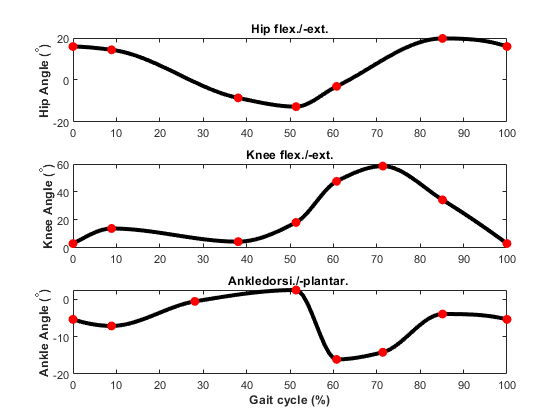

% Remove the 6th value
myStruct.hip.keyEvents.x(6) = [];
myStruct.hip.keyEvents.y(6) = [];

% Define x and y for hip
x_hip = myStruct.hip.keyEvents.x;
y_hip = myStruct.hip.keyEvents.y;

% Iterate through each column
for col = 1:size(y_hip, 2)
    % Set the last value of the column to be equal to the first value
    y_hip(end, col) = y_hip(1, col);
end
% Define x and y for knee
x_knee = myStruct.knee.keyEvents.x;
y_knee = myStruct.knee.keyEvents.y;
for col = 1:size(y_knee, 2)
    % Set the last value of the column to be equal to the first value
    y_knee(end, col) = y_knee(1, col);
end
% Remove the 6th value
% myStruct.ankle.keyEvents.x(6) = [];
% myStruct.ankle.keyEvents.y(6) = [];
% Add 0.05 to the 4th value
myStruct.ankle.keyEvents.y(4) = myStruct.ankle.keyEvents.y(4) + 3;
myStruct.ankle.keyEvents.x(3) = myStruct.ankle.keyEvents.x(3) + (-10);
% Define x and y for ankle
x_ankle = myStruct.ankle.keyEvents.x;
y_ankle = myStruct.ankle.keyEvents.y;
for col = 1:size(y_ankle, 2)
    % Set the last value of the column to be equal to the first value
    y_ankle(end, col) = y_ankle(1, col);
end
% Create a shape-preserving interpolant using pchip for hip
pp_hip = pchip(x_hip, y_hip);
i = 0:1:100;
xi = i;
yi_hip = ppval(pp_hip, xi)';

% Create a shape-preserving interpolant using pchip for knee
pp_knee = pchip(x_knee, y_knee);
yi_knee = ppval(pp_knee, xi)';

% Create a shape-preserving interpolant using pchip for ankle
pp_ankle = pchip(x_ankle, y_ankle);
yi_ankle = ppval(pp_ankle, xi)';

% Create subplots
figure;

% Subplot for hip
subplot(3,1,1);
plot(xi, yi_hip, 'LineWidth',3,'Color',[0 0 0]);
hold on
plot(x_hip, y_hip, 'MarkerFaceColor',[1 0 0],'Marker','o','LineStyle','none',...
  'Color',[1 0 0]);
hold off
ylabel('Hip Angle (^\circ)','FontWeight','bold','FontName','Arial');
title('Hip flex./-ext.');

% Subplot for knee
subplot(3,1,2);
plot(xi, yi_knee, 'LineWidth',3,'Color',[0 0 0]);
hold on
plot(x_knee, y_knee, 'MarkerFaceColor',[1 0 0],'Marker','o','LineStyle','none',...
  'Color',[1 0 0]);
hold off
ylabel('Knee Angle (^\circ)','FontWeight','bold','FontName','Arial');
title('Knee flex./-ext.');

% Subplot for ankle
subplot(3,1,3);
plot(xi, yi_ankle, 'LineWidth',3,'Color',[0 0 0]);
hold on
plot(x_ankle, y_ankle, 'MarkerFaceColor',[1 0 0],'Marker','o','LineStyle','none',...
  'Color',[1 0 0]);
hold off
ylabel('Ankle Angle (^\circ)','FontWeight','bold','FontName','Arial');
xlabel('Gait cycle (%)','FontWeight','bold','FontName','Arial');
title('Ankledorsi./-plantar. ');

% x = myStruct.hip.keyEvents.x;
% y = myStruct.hip.keyEvents.y;
% s = spapi(3,x,y);
% i = 0:1:100;
% s = fnval(i,s)';
% % Create figure
% figure;
% 
% % Create axes
% axes1 = axes;
% hold(axes1,'on');
% 
% hold on
%  %Create plot
% plot(i,s,'LineWidth',3,'Color',[0 0 0]);    %RGB=[0 0 0]
% 
% % Create plot
% plot(x,y,'MarkerFaceColor',[1 0 0],'Marker','o','LineStyle','none',...
%   'Color',[1 0 0]);

% % Create ylabel
% %ylabel('Angle (^\circ)','FontWeight','bold','FontName','Arial');
% %ylabel('Velocity (^\circ/gait cycle)','FontWeight','bold','FontName','Arial');
% %ylabel('Acceleration (^\circ/gait cycle^2)','FontWeight','bold','FontName','Arial');
% 
% % Create xlabel
% xlabel('Gait cycle (%)','FontWeight','bold','FontName','Arial');
% 
% % Uncomment the following line to preserve the X-limits of the axes
% % xlim(axes1,[0 100]);
% hold(axes1,'off');
% % Set the remaining axes properties
% set(axes1,'FontName','Arial','FontSize',24,'XColor',[0 0 0],'YColor',...
%     [0 0 0],'ZColor',[0 0 0]);
% 
% %Add Legend
% legend


# Data storage

structName.gaitPhases = gaitPhases; 
structName.hipAngle = hipAngle;
structName.kneeAngle = kneeAngle;
structName.ankleAngle = ankleAngle;
structName.timeNormalized = timeNormalized;
structName.keyPoints.hipExtraction = {allRowsColumn1_hip allRowsColumn2_hip};
structName.keyPoints.kneeExtraction = {allRowsColumn1_knee allRowsColumn2_knee};
structName.keyPoints.ankleExtraction = {allRowsColumn1_ankle allRowsColumn2_ankle};
structName.regressionData = data;
structName.stepwise = stepwise;
structName.myStruct = myStruct;

# Plots

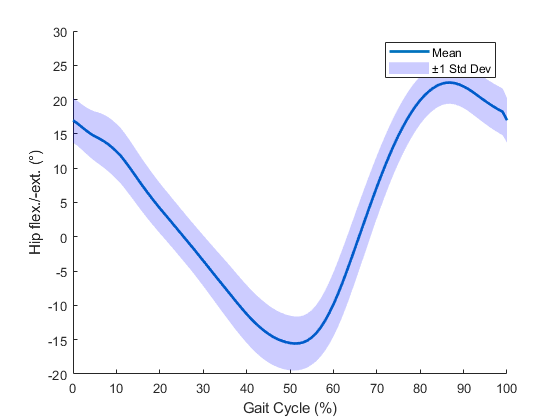

% Assuming the variables in the workspace are named dataMatrix (101x216) and xValues (101x1)
% If they have different names, replace them accordingly

% Calculate the mean and standard deviation across the 216 columns
meanValues = mean(hipAngle, 2); % 101x1 vector
stdValues = std(hipAngle, 0, 2); % 101x1 vector

% Plot the data
figure;
hold on;

% Plot the mean values
plot(timeNormalized, meanValues, 'LineWidth', 2, 'DisplayName', 'Mean');

% Plot the shaded area for ±1 standard deviation
fill([timeNormalized; flipud(timeNormalized)], [meanValues + stdValues; flipud(meanValues - stdValues)], ...
    'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '±1 Std Dev');

hold off;
xlabel('Gait Cycle (%)');
ylabel('Hip flex./-ext. (°)');
%title('Mean and Standard Deviation with Shaded Area');
legend('show');

%grid on;

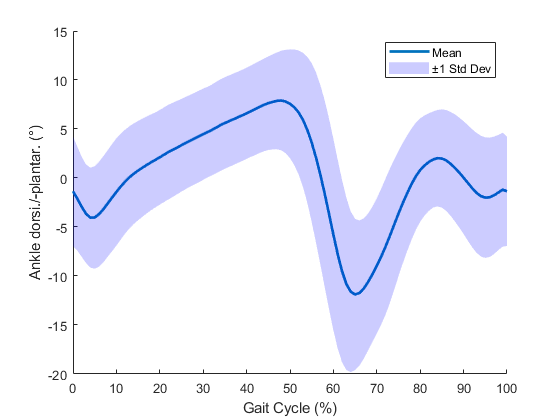

% Assuming the variables in the workspace are named dataMatrix (101x216) and xValues (101x1)
% If they have different names, replace them accordingly

% Calculate the mean and standard deviation across the 216 columns
meanValuesAnkle = mean(ankleAngle, 2); % 101x1 vector
stdValuesAnkle = std(ankleAngle, 0, 2); % 101x1 vector

% Plot the data
figure;
hold on;

% Plot the mean values
plot(timeNormalized, meanValuesAnkle, 'LineWidth', 2, 'DisplayName', 'Mean');

% Plot the shaded area for ±1 standard deviation
fill([timeNormalized; flipud(timeNormalized)], [meanValuesAnkle + stdValuesAnkle; flipud(meanValuesAnkle - stdValuesAnkle)], ...
    'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '±1 Std Dev');

hold off;
xlabel('Gait Cycle (%)');
ylabel('Ankle dorsi./-plantar. (°)');
%title('Mean and Standard Deviation with Shaded Area');
legend('show');

%grid on;

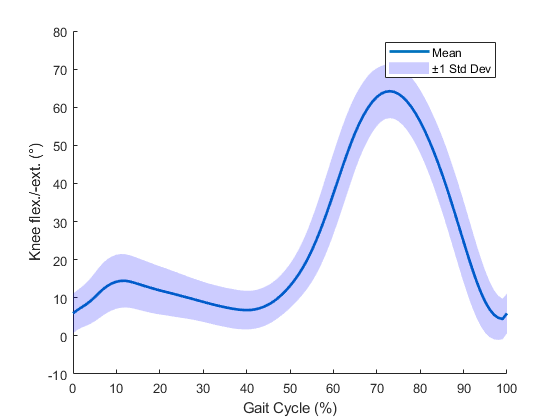

% Assuming the variables in the workspace are named dataMatrix (101x216) and xValues (101x1)
% If they have different names, replace them accordingly

% Calculate the mean and standard deviation across the 216 columns
meanValuesKnee = mean(kneeAngle, 2); % 101x1 vector
stdValuesKnee = std(kneeAngle, 0, 2); % 101x1 vector

% Plot the data
figure;
hold on;

% Plot the mean values
plot(timeNormalized, meanValuesKnee, 'LineWidth', 2, 'DisplayName', 'Mean');

% Plot the shaded area for ±1 standard deviation
fill([timeNormalized; flipud(timeNormalized)], [meanValuesKnee + stdValuesKnee; flipud(meanValuesKnee - stdValuesKnee)], ...
    'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '±1 Std Dev');

hold off;
xlabel('Gait Cycle (%)');
ylabel('Knee flex./-ext. (°)');
%title('Mean and Standard Deviation with Shaded Area');
legend('show');

%grid on;

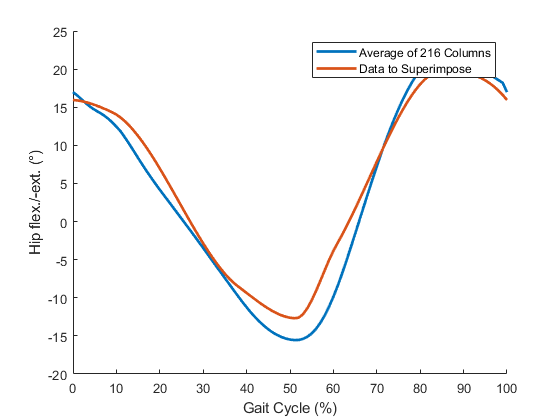

% Assuming the variables in the workspace are:
% dataMatrix - 101x216 double matrix
% xValues - 101x1 double vector for x-axis
% dataToSuperimpose - 101x1 double vector to be superimposed on the plot

% Compute the average of the 216 columns
averageDataHip = mean(hipAngle, 2);

% Create the plot
figure;
hold on;

% Plot the average data
plot(timeNormalized, averageDataHip, 'LineWidth', 2, 'DisplayName', 'Average of 216 Columns');

% Superimpose the other data
plot(timeNormalized, yi_hip, 'LineWidth', 2, 'DisplayName', 'Data to Superimpose');

% Add labels and title
xlabel('Gait Cycle (%)');
ylabel('Hip flex./-ext. (°)');
%title('Superimposed Plot of Average Data and Other Data');
legend('show');

% Display the plot
hold off;

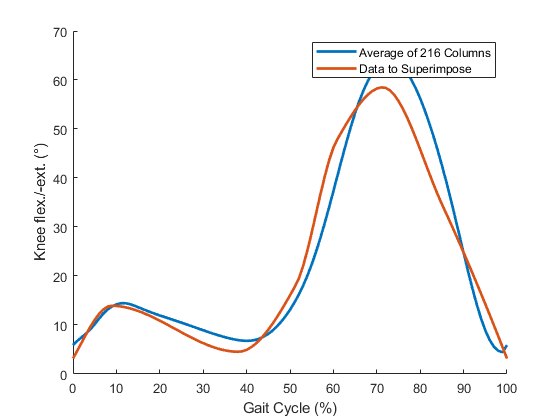

% Assuming the variables in the workspace are:
% dataMatrix - 101x216 double matrix
% xValues - 101x1 double vector for x-axis
% dataToSuperimpose - 101x1 double vector to be superimposed on the plot

% Compute the average of the 216 columns
averageDataKnee = mean(kneeAngle, 2);

% Create the plot
figure;
hold on;

% Plot the average data
plot(timeNormalized, averageDataKnee, 'LineWidth', 2, 'DisplayName', 'Average of 216 Columns');

% Superimpose the other data
plot(timeNormalized, yi_knee, 'LineWidth', 2, 'DisplayName', 'Data to Superimpose');

% Add labels and title
xlabel('Gait Cycle (%)');
ylabel('Knee flex./-ext. (°)');
%title('Superimposed Plot of Average Data and Other Data');
legend('show');

% Display the plot
hold off;

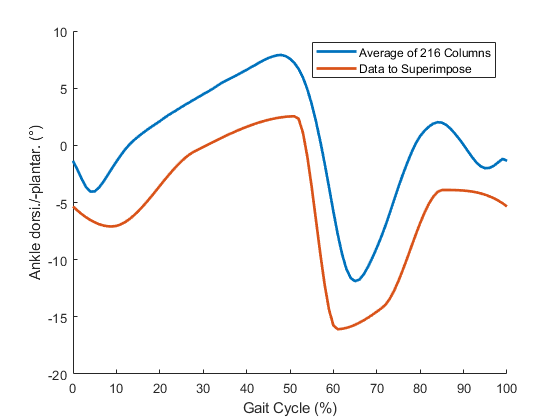

% Assuming the variables in the workspace are:
% dataMatrix - 101x216 double matrix
% xValues - 101x1 double vector for x-axis
% dataToSuperimpose - 101x1 double vector to be superimposed on the plot

% Compute the average of the 216 columns
averageDataAnkle = mean(ankleAngle, 2);

% Create the plot
figure;
hold on;

% Plot the average data
plot(timeNormalized, averageDataAnkle, 'LineWidth', 2, 'DisplayName', 'Average of 216 Columns');

% Superimpose the other data
plot(timeNormalized, yi_ankle, 'LineWidth', 2, 'DisplayName', 'Data to Superimpose');

% Add labels and title
xlabel('Gait Cycle (%)');
ylabel('Ankle dorsi./-plantar. (°)');
%title('Superimposed Plot of Average Data and Other Data');
legend('show');

% Display the plot
hold off;

# Computing r squared and rmse

% Assuming the variables in the workspace are:
% averageData - 101x1 double vector (average of the 216 columns)
% dataToSuperimpose - 101x1 double vector to be compared with

% Compute the RMSE
n = length(yi_hip);
rmseHip = sqrt(mean((yi_hip - averageDataHip).^2));

% Compute the R-squared
SS_resHip = sum((yi_hip - averageDataHip).^2);
SS_totHip = sum((yi_hip - mean(yi_hip)).^2);
r_squaredHip = 1 - (SS_resHip / SS_totHip);

% Display the results
fprintf('RMSE: %.4f\n', rmseHip);

RMSE: 2.5010


fprintf('R-squared: %.4f\n', r_squaredHip);

R-squared: 0.9508


% Assuming the variables in the workspace are:
% averageData - 101x1 double vector (average of the 216 columns)
% dataToSuperimpose - 101x1 double vector to be compared with

% Compute the RMSE
n = length(yi_knee);
rmseKnee = sqrt(mean((yi_knee - averageDataKnee).^2));

% Compute the R-squared
SS_resKnee = sum((yi_knee - averageDataKnee).^2);
SS_totKnee = sum((yi_knee - mean(yi_knee)).^2);
r_squaredKnee = 1 - (SS_resKnee / SS_totKnee);

% Display the results
fprintf('RMSE: %.4f\n', rmseKnee);

RMSE: 4.6348


fprintf('R-squared: %.4f\n', r_squaredKnee);

R-squared: 0.9366


% Assuming the variables in the workspace are:
% averageData - 101x1 double vector (average of the 216 columns)
% dataToSuperimpose - 101x1 double vector to be compared with

% Compute the RMSE
n = length(yi_ankle);
rmseAnkle = sqrt(mean((yi_ankle - averageDataAnkle).^2));

% Compute the R-squared
SS_resAnkle = sum((yi_ankle - averageDataAnkle).^2);
SS_totAnkle = sum((yi_ankle - mean(yi_ankle)).^2);
r_squaredAnkle = 1 - (SS_resAnkle / SS_totAnkle);

% Display the results
fprintf('RMSE: %.4f\n', rmseAnkle);

RMSE: 5.6751


fprintf('R-squared: %.4f\n', r_squaredAnkle); %THERE IS SOMETHING WRONG WITH THIS VALUE, CHECK THE CALCULATION AGAIN!!!

R-squared: -0.0713


# Export to excel

% Define the directory of Excel file name
excelFileName = 'E:/New/DOCUMENTS/Projects/kone/projects/New Folder/raw data/Test/p11/csv_files/concatenated_data.xlsx';

% Load your data (this step can be skipped if data is already loaded)
% hipAngle = ...;
% kneeAngle = ...;
% ankleAngle = ...;

% Define the target sheet numbers (starting from sheet 6)
sheetNumbers = [6, 7, 8, 9, 10, 11, 12];

% Define the data ranges (top-left cell)
% This example starts writing at A1 for each sheet, adjust as needed
range = 'A1';

% Write the hipAngle data to sheet 6
writematrix(hipAngle, excelFileName, 'Sheet', sheetNumbers(1), 'Range', range);

% Write the kneeAngle data to sheet 7
writematrix(kneeAngle, excelFileName, 'Sheet', sheetNumbers(2), 'Range', range);

% Write the ankleAngle data to sheet 8
writematrix(ankleAngle, excelFileName, 'Sheet', sheetNumbers(3), 'Range', range);

% Write the kneeAngle data to sheet 9
writematrix(yi_hip, excelFileName, 'Sheet', sheetNumbers(4), 'Range', range);

% Write the kneeAngle data to sheet 10
writematrix(yi_knee, excelFileName, 'Sheet', sheetNumbers(5), 'Range', range);

% Write the kneeAngle data to sheet 11
writematrix(yi_ankle, excelFileName, 'Sheet', sheetNumbers(6), 'Range', range);

% Write the kneeAngle data to sheet 12
writematrix(timeNormalized, excelFileName, 'Sheet', sheetNumbers(7), 'Range', range);

